# **OFDM Receiver Testing senza codifica di canale**

Questo esempio mostra come progettare un ricevitore OFDM (Orthogonal Frequency Division Multiplexing) per un canale SISO (Single-Input Single-Output) utilizzando una radio definita dal software (SDR). Il ricevitore OFDM cattura e demodula il segnale OFDM inviato dall'esempio OFDM Transmitter Using Software-Defined Radio. La progettazione del ricevitore OFDM include sample bufferring per la regolazione della temporizzazione, il filtraggio, la regolazione della frequenza portante e la demodulazione OFDM.

## Set OFDM Frame Parameters

Imposta i parametri OFDM, tra cui la lunghezza FFT, la lunghezza del prefisso ciclico e il numero di sottoportanti. La spaziatura delle sottoportanti pilota e la larghezza di banda del canale sono fissate rispettivamente a 30 KHz e 3 MHz.

Dopo aver configurato i parametri OFDM, imposta i parametri dei dati. Imposta l'ordine di modulazione, la velocità di codifica, il numero di simboli per frame e il numero di frame per trasmissione.

Puoi abilitare o disabilitare gli ambiti per la visualizzazione, tuttavia per simulazioni lunghe, si consiglia di disabilitare l'ambito. Per controllare la visualizzazione del testo di output diagnostico, abilita o disabilita la verbosità in base alle esigenze. Per visualizzare i dati decodificati in ciascun frame, abilita il flag di stampa dei dati

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % lunghezza FFT 
OFDMParams.CPLength               = 32;    % lunghezza Cyclic prefix
OFDMParams.NumSubcarriers         = 72;    % numero di sub-carriers nella banda
OFDMParams.Subcarrierspacing      = 3e3;   % spaziatura delle Sub-carrier 
OFDMParams.PilotSubcarrierSpacing = 9;     % spaziatura della pilot sub-carrier 
OFDMParams.channelBW              = 3e5;   % lunghezza di banda

% Data Parameters
dataParams.modOrder       = 256;   % tipo di modulazione
dataParams.numSymPerFrame = 25;   % numero di data symbols per frame
dataParams.numFrames      = 100;   % numero di frames da trasmettere
dataParams.enableScopes   = true;                    % visualizzatore dello spettro
dataParams.verbosity      = true;                    % ottenere i dati diagnostici
dataParams.printData      = true;                    % restituire i dati decodificati

## Initialize Receiver Parameters

La funzione helperGetRadioParams inizializza l'oggetto System del ricevitore™ ofdmRx. Assegna il nome della radio che stai utilizzando per ricevere il segnale OFDM alla variabile radioDevice. Imposta il guadagno del ricevitore e la frequenza del centro operativo.

La funzione helperGetRadioRxObj inizializza l'oggetto System del ricevitore radio.

centerFrequency        = 865e6;   % Center Frequency
gain                   = 60;   % Set radio gain

La funzione helperOFDMSetParamsSDR inizializza i parametri comuni e specifici del trasmettitore e del ricevitore richiesti per la simulazione OFDM, mentre la funzione helperGetRadioParams inizializza i parametri richiesti per la radio System Object™ del ricevitore.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

## Execute Receiver Loop

#### Synchronization

Il ricevitore OFDM controlla il buffer di campionamento per il simbolo di sincronizzazione per trovare il punto di partenza dei frame di dati all'interno del segnale OFDM ricevuto. Il ricevitore ha correlato il segnale OFDM ricevuto con il simbolo di sincronizzazione noto. Una volta che il ricevitore OFDM rileva un picco di correlazione elevato, identifica la posizione in cui trova il simbolo di sincronizzazione come inizio del frame

#### Frequency Offset Estimation and Correction

Il ricevitore OFDM stima e corregge la frequenza e l'offset temporale introdotti nel segnale OFDM trasmesso a causa di compromissioni del canale. Il ricevitore OFDM controlla il buffer del ricevitore per il numero di frame richiesto ed esegue la correzione automatica della frequenza su ogni simbolo. Il ricevitore calcola la media della correzione della frequenza sulle sottoportanti e poi su ogni sei simboli, considerando un gruppo di sei simboli come uno slot. Il ricevitore considera il valore medio complessivo di queste correzioni come offset di frequenza e compensa questo offset di frequenza sull'intero frame. Il ricevitore è considerato accampato su una stazione di base dopo aver ottenuto una sincronizzazione riuscita e la correzione del deterioramento del canale.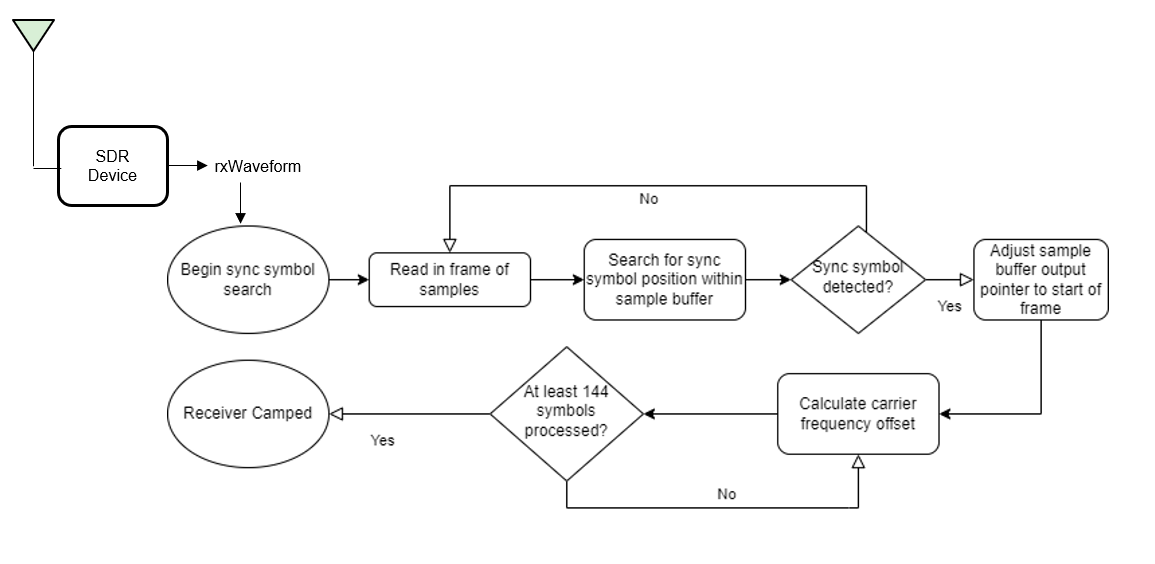

### Receiver Processing

Questo processo è l'inverso di quello che avviene nel trasmettitore.

#### Channel Estimation and Equalization

Inizialmente, il ricevitore OFDM esegue la stima del canale sui simboli di riferimento demodulati OFDM. Per rimuovere gli effetti del fading variabile nel tempo, il ricevitore seleziona due simboli di riferimento da frame adiacenti per stimare il canale in due diversi punti nel tempo. Il ricevitore quindi interpola linearmente le stime del canale tra i due simboli di riferimento per ottenere le stime del canale per l'intestazione e i simboli di dati. La funzione ofdmEqualize quindi equalizza i simboli di riferimento e i simboli di dati utilizzando le stime del canale.

#### Header Decoding

Il ricevitore estrae e decodifica i simboli di intestazione per ottenere i parametri dei simboli di dati quali lunghezza FFT, schema di modulazione del sottoportante e velocità di codice. Il ricevitore utilizza questi parametri per demodulare e decodificare i simboli di dati.

#### Data Decoding

L'errore di fase comune (CPE) interessa tutte le sottoportanti in egual modo e il ricevitore OFDM utilizza i simboli pilota all'interno dei simboli dati per stimare il CPE. La funzione helperOFDMRx corregge gli errori di fase nei simboli dati e la funzione qamdemod decodifica soft le sottoportanti dati in rapporti di verosimiglianza logaritmica (LLR). Il ricevitore quindi deinterlaccia il flusso di bit demodulato e la funzione vitdec esegue la decodifica di massima verosimiglianza utilizzando l'algoritmo di Viterbi. Il descrambler descramble i bit decodificati e il comm.CRCDetector calcola il controllo di ridondanza ciclica (CRC) e lo confronta con il CRC aggiunto.

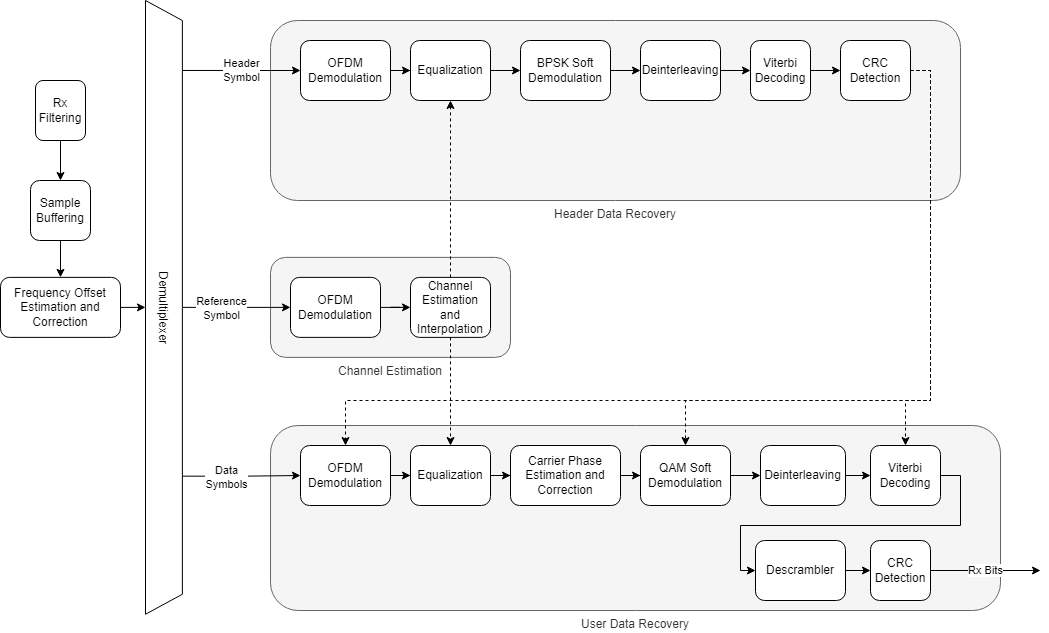

## Establishing connection to hardware. This process can take several seconds.


BER = 0 



Sync symbol found.
Estimating carrier frequency offset ...

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 



Receiver camped.


BER = 5.000000e-01 


Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491792e+03 Hz.
Correcting frequency offset across all samples
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 10:□□□□@□`#t_cy□$N-FR
□ □b□  8□FF□'□| F□□□□8□ZXO□}pZ□□4□$`r□□
$@□t□h□	□□□p"I $□B g□□O□□□CdK □"□LH□
8)□3I□LQd□L□(@□□A □AL A|^ □□ QMd□□□9□D@□□Yz8F□□Mr□□□□H□dv□-  □□hAP "□□□D□dyP'□□$DI= T□ □^(□□□J□0 
□'x#AbD□j0^"bD@□I 0AZ0B  □4#K□<□ $"□/□□6VD□□A<f□(i □□□(□□0 □(Id□@
□	z @B!□z□ □z□$	h6J□!C□!□□ □&□H□$0□ $h□□8y□□□p&)□Q□□ @
,□□ (  M□EA□%□□□	}dI□□ Z8@□ Ah$E□&Il$F□ @□ 
 l□J□□H□#I□□□□ i□AI□#□CD □8□□`h□□□□□Q□□  □@□1□□ 	z□I < _ @□C\□$;2□	^,B0□ 	!jPy0,wD□O□ Gp$□□eG□□<OtJ3<□□PY□J□□□0pd□ □□ □□	~ □ □Ah$9□ ~~ C□ Ah □□□  $
  Ab □□□O□ G□(H□□□1@ Q□□` tH□&□□ 1P□H  y□□□ N□0□□□Mh$E□ n:0A□ A(5H□ @ <□□ □MEH□ □q□ 	□□H□□`T □`  □□□@□ HB□□□$□□□E□ H□□	: A   S@@ A	d$K□□p□ 	 $P□DP□ A□( □$□□ @□ I□$`  I□.@pdI□ i □□□ G□□9I□DA □□□□#	 S@@□%Hr □  )P□@□ Y□@)K& I2□@□$I$ A□$ □□  □ @□$ □$□ dI□$□□ □"□I2 @  
  A□ H□ P  A□□□ @□ @ $J□ A□□H□□I  A□□□□ □□ A□ A □ B □□ 	□□I□ H□ @□ I□@I □ 2□ I□□□8□ □□□□#D□□H□#IP H□□Y□ □Q□#□□□q□□52$	□v□□□$@□d□□$P□ H□$	□bID$C□□ *8A□□c8□I  □W@@ □)□@9 h□@□□   I $□@$`□ I□□□R I□□`H□□ 	□<

BER = 4.924242e-01 


Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491961e+03 Hz.
Correcting frequency offset across all samples
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 11: O□AYy
'eYHB@$ K|□S !□XH□&@□|□□ ?A □□CA□BYYLH=k□Y@@aPJ□$□s 	□□A□$H|$	R )r$H@□ I□□A  :.#@ $ N$G3 □  I□$H8$  □p` □□□i□$ n□□w| @Q  n`$I □Ap$En□@@$  r□A□4 n□$
l□p□c□□□F□$YR'□□dh□□	=@@□ 	^8 □□J□□ □□'8"A□□□z□N□!F`□H□□□ODAc`k~$Xd□.□z{□□E%B□W□r L (□p□J#@q:@@md!3gIH□GyYCI□□I] R O,2□□ YcDhh□0($>U □
 C1 P=JC ;>@PEa□K=@□□□□□(H *I□\q□□□
,□j I@<	V□@c□@@di  IM$`□□ y d□8□ □$HS$I□□ I□□A□ □b,
38□□□H□□ □<□□   < □ 	6 Ih□H□$□TAA"Ev□d	□□	^,AR  □$	b □I2$P@$I□ A□□ □%A□ □b$Jsl□I□□□□,□R  I  □□$I, A□$ f  UTD	□  .$	@$ □ 	"  □ I□$A@□I□ A□□□□` Q□□p□tH□'	□ 1P @h□□$□□ L□0□□□O($G□$j:8A□ Ah=D
 @ $□
h□L□$□□ E□xi□$N□□H□"Fp□ □ □□□@□6H□□□□$
□DA□□D 8@h$□□,IMd	□gD^ □□!90□V> )□`) h□K□ U&□□□| □ +□<  □□C @□XHB$□□$I!@Hp$$  ,	RdHV 8□'	|□A<(Ix AB@Kx$□1EO 	H□□II□□r□$I□ A□$ □□(6□HC□|□□,□□gK□l□□  nCIR Bd □h A□@H□0aIV$I□□ fd	@$I□@I□$Xx I□ □R  □$A□$ □&H□( C□, □< r C□ □>"□t @h$)□^@I□(5L$□□!1Ld□□"@	□l@
□ □4$9L□A□$□R□A□□gb$	3| Ja$I□|□□$D□ H□$a□$Il2A□□ n a□□w| I□ (_DB$ )□@9 x□R□□□ !K□,□@$b□	I□□□R I□□□□ H□□□□ 	□5  

BER = 4.902936e-01 


Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492500e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 12: x□H-□□ `"TW I□$T□
`□□ □)	 □N□
@□*□(8@r `□[LI□o0ZH+8□$□R 	□$@p$H|,	□ □S$I □ I□□A□ □F%A`$ □<Jr□□ □I□$It, @□@□ !□□I l O□FU_ P□  Od	@$I□D@□$Ij□@□$C□C □ C2$□,
l□P□#□□□F□$yR'□□dh□□	□ X□ 
V(□□□N□0□□□gx&A"□□j0N"#F`4I□@1j□@  □Q%I□□
#$□□f□□□WP< □< □0Y □□□□I"  &PI@$@□$yi@A□!□□□"	l$D□ Ab □  	B□J□$□□/
□$H□□□□PI G
| I□X□□  □□□□ H □I□□A□8□
□	:$I 4 V□@ CAd$I  AEd@□□ 
 ) (□P□<HQdI□□ I□□ 
B4□□8□□□H□□ □4□□□  40□ 	□ i)□H□d□U@ACGT□d	□□	~,AR  □ 	b □j Ip$P@□I□ A□$ □%A□ >f$JS|□I□□ □,□R! □8)□ □□$)+ A $`Cd	@ US@I□ □C 	`$ □`	□ `□□Y□$C □I□ C□ □□@ A□□0 |H□f	□ !p□H  I □$	□`F□□□□□E($O□ j:0A□ A(<F
 @ $	□$□L□ □□ E□py□$LH□#Bp□ □`□□□@□?H□□□□$□□DA□□L□dYHAI□C	YJA#OHOd	3T □ Z@`□ Q`1jX0, ;W%@x□A□d !NA□□wXe@`XI`$□ dI  I□$HT$ `□	2$@4□$	t□@p I4 @!PI|$□rBI  HB AN Hr□`□$H`□A□%□n□  @□t □$□□$I□$□□ □
□I2 @@ □L□A□□H□$	Q"	^$I□□ G 	`$Y□ I□$(x`e□ 
r" □$GP□□□gH□□pM□< □\□□ A□ 	 □	 □$□□ @d$I□v I
 3,$
□"q,$
□□	b 
□o □□ □□$il□A□$□R□A□□wr$	3| J!$H□□□p$@
 H□$a□$Il3A□□ n q□□w| M□[HDh 9□H□ H\L□L  (E □! ,\□□I1□=B I□□□□

BER = 4.905698e-01 


Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367567e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 13: h□Q5□□□D"t_)□^m□r□r □ H*□□B□.□xhF□□ :q
[\K□□b[X□8*8□d□R 	□,@0$Hx,	□ □SdI □ I□□A □□f%A $ □lN2□□I□$It, @□B,  q□I□d0g□GmW @2  o`	l$I□D@□dI*□$S□  □ A2$ □□,□h @ %□0 L□dIz$□□$H□□	□@p□@□~#□□□H□  □□e8(A"□□*8J"fM`
O xQKp 4Xk]□ □ }|
70□vtL□!a4|2)+
□□p)□.:□
9Ih
T□\□ZH`c~□Kq0□j
K~□U□□YR\G.],&□x8□J2ZWd$H]:Md(□v□{s)□□%Un;□6□[@p□□□□ x  I□□A□&
□□	~ I □ ^	@ @AD$ AldF□8p□ □ h□F□□HP"I□□□□ i□IE□"□GL□□(□□hx□□□□□q□□  □P□□□* □~DI`4 _ @c□t□$	□□	V$@□□$	□@!j□y□$SD□K□ A□$ □d□□NlJ3,□□PY□□□□4□r& □pi□8□□,){@A <PE$	@ }W□I□M 	`, □ 	□ `□□y□<W`□I□ GS8
A  ap @□YHV$□□  s□@	□,□$di□eH□#□□□Ix,A□$.n Ab@O8□H□!@ <□□ □IEH□d6(□Q□`9□4J□□cT$□□□`□□□B□;Hb□□□$□□GC□□L □ i% □e@OU"@_ b 8Y□□"r□i□`Y#□hXtY
□uG□	.$
□ i□ns?OlO/□- □3□sUhq(□□K=□qLL
{tHH*	@_□V?.X&l{)X□d~Y++□/!□Iz8□□ \`!O□XJ0□t□= □□ H□|N□□q□1G□□A□=68T<(□Z p□8□□QcYV$I□□ O$	`,Y□ Y□$xZ □□ □R□ □$C0$0□fH□92□PM□< □t□p`cub□ 
b□*g□□!EL4_□$□zPM□!%H4□<.QHt□t□□bQ□□□□KC□□!6h4Y□ A□$□0
A□
gB,□1< □C	`gH□□□P%@□PX□$I□dyx	A□□0O 1gEe] !□_HF(□9□H□ H□D□□□ !O □□ $t□□I□F□R I

BER = 4.903232e-01 


Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492094e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=1024
Data decoding completed
------------------------------------------


Received data in frame 14: HsHo□□□aft]8O$$d/□ 6[98 □L□□p□2□l0ps@prX8[□Iw.0[H4,+h□d□R@	□<AP$H|$	6 9SdI@□ I□□A□ >N&@@$ .lLSA□I□$I\, `□Bl 1□DY□$0O□Gu] @□@ O`	@$I□D@1dIj□$S□□ □ A□$ □□,
lB`□#□□□F□dxR&
□d(□D	9@P□ □^0□□□L□□ □□gx&A□□□j0N"#F`4I□@1j□@!`?W%I8□d□/n□□□u@, □< 2□I`□□□□Ib 0nPAD$P~dyIAA
ZHa□□□#	HlF*(PB □ N□L□$□8*□□dH□□□I N□X I□□□□  □□□□ H □I□□A□1□
4	:$I 4 V□@□B□Ldy  AM$p2□ □□) h□p□,HQ%I□□ I□B!□F|□□8□□PH□□ □4□□□  40□ □> yi□H!d□]AAcGt□d	2□	^,AR  □d	b □I0$P@$I□□A□$ □'A□□□FdJS<□□□I□□□□<□R# □x9□(□□,9; A l`G$	` uWDI□  G 	`$ □ 	□Hp□□i□$C`□I□ Gq□□□` Q□□`□tH□&	□ !pDH  y□□$	□ F□□□□□E($M□ jz0A□ A(<N□ @ $
l□L□ □□ G□x)□$N□□H□#Fd□ □ □□□@□:H□□□
$□□DA□□L□"OH□I□□	XUG
UHZ>
qm□□□Lc@□0□□< □Qa@o~,a$Gq□:□f_qg□%If@aXI`$□□dI  I□$H|$ @□	r$@?□$	\□@P I| @c□I|$□sBI  Hb Ej@IR□`□$IL□A□% J□``□@@□| 
$□□$I#$□□ □j□Ir B@@
h□A□□H□$	s^ K□□0O$□`<y□ y□<□: %□□□r□ □$LP□0□gH□□hK□<"□L0□ Q0!	 □	□□%□□`@L$I□~□I□ 7l,
□&qh$
□□	b □□O@□□`□□$I(□A□□ r□A□□wR$	S< nC	AeH□□ P$@$q□$Il□A□D N 1□□w\@E□[XD8 □□H
 HLL□D  (E □1 ,\□□I3□=B I□□□□!H□4□

BER = 4.893939e-01 


Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492071e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 15: 8□□□□ □@"TW`$N□GP□> □  h□□@□'□8 @□ 0□ZXI□}`Z□□□□$ r□□□ @□|8h□	□p&I $□B □□□M□□□BdO 4□□\H□□ □8i□>I□\Q`□D□0@□□A 4AM□C|^ □□ aMd□4□)□D@□□Iz8@□□E□□ □ J□$`□$  □□l□P &□□CD□dYR%□□$DI? p□ □^!□□□H□0 □□'x#Ab□□j0N""D@□I□□aj□@ $
pfI□$□Ad□□g□□□V@□ □<□□8Y □□□8y □pI`,@□,9+@A"!□"	l$D□ Ab □  	B□H□d□□□$H□ □□PI□□
| I□P□□p@□□ y  K□DA□&□□□	□$I □ @  Al$M□#Id$F□ @□ □ d□N□□H0'I□□
□ I□□E□ 
B\□□8□□8H□□ □□!□□  □p□ 	□ 9+□H d□U @c□t $O□□ ^ @20`	`	 8Az8□□□E □C
 H□□ □$I□□□CDH□<p□ i□□□
□@□$ □`	□□ □□	: I 4Add	  \v I□□qdd	 4 □d	 0@□(	□□G  I□ H□□□!@ Q□□p WH□'□□ 0P□@i□□d□□!N□8 □□Ox$C□$n:8A□ G8□N□ @ $□□l□J□ □□ G□pi□$N□□H□#Fr□ □ □□□@□:H□□□□$
□□A□□L□ FD,H
□	,,K□,@:□□□N□P □□D@A□ I□4□ D □□□□□ @D
  P tH□%	□$YCAO□$(□%□□1#AV D□#	84A□0A8□A□ C8&□□□@ 7H□□`I_\□d4V%□□□□□□5□□YwzQ
□1S□□□+?□u>jk
@I}□□GhLEoM*H<□B□d	qcIV I□□ C$	`$I□@I□$8: y□2! □$Cp□ □%H□□0M□$ □\ □ G□ □ □□9□□8@h$	 wDI□□□L$   □Ed	 □(□@9□( 9□8□□$il□A□$□R□A□□wb$	s| nadH□4□0$H□ H□$q□$Il□A□□ n a□□w| I□_@B  9□@□ h□F□□□  O <□ $v□	I□B□R I□□
□ H□□ □ 	□,  □A

BER = 4.893466e-01 


Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491934e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 16: HS@k□□□ ft]8O $&□□ □Y8( 0F□□p□□
d□qS@PRH8[□Iw.□[@&$)x
$□s@	□□A0$H|$	r 9r$H@□ I□□A□ >n"@`$ n$Es@□  $H|$  □P` □□□y□d n□□w| @3  n@$I □@P$O*□@ $q□@ □ A□< □□$
d□ □`□□□@□$hR&□□$8□□	□ @□@	^□ □□D□□□□4'h%A□z□N□ @ 4IB □n□@a ;vdIh□d nj□□
g@$□□t H@□□HB !NH@D$pVdIH□A□^@Q□^ !□HlF:8Pb □ F□T□$□<#□□`H□ 6□□I □□L I□□□□ □□□□□(H *I□\q□□$9*$H@,□V□@c□@Ad9  @G$`□□ y d□(4 □$IRdI□□ I□□A□ □fsh□H□□ □,□□  `l □ 	2□Il□H□d□TCA□□v□$	rt	^4AR@ □B □n IP$P`$I□□A□□ .&A  □f$MS<□□ I□@ □$□r  I□ □□$I, A□$ n  w|DI□  . 	@$ □ 	"  □ I□$A@□I□ A□ □ @ A□□ □tH□"	□ a0□H  I 
$	□`F□□□□□G($O□ j:□A□□A(,F□(P $□□h□D□$□□ M□pY□$DH□"Fp□ □ □□□@□7H□□□□$□□DA□□D □pId□□lIM,	w.@[@&□)i0□fv□i□ i!@8H□K□□unF□□l□□@k□?□□R□O&@!XI@$
□$I @H□$H|$ `4	r$@}□%	|□AP Ix @c□I|$□s□I  H" Kn Iv□$I(□A□$ n□  □ @□|□
$□□dI□$□□ □N□Ir @d □l□A□ H□□aIV$I□□ Nd	@$I□@I2$X~ I□ □R  □$A□$ □&H□(□C□< □< Q A□ □	□□&□P @l$Z□I□ 5L$□□#!l$□□B □□m □□ □□$)L□A□$□R□A□□gr$	3t Na$H□4□0$@□ H□$a□$Il2A□□ n a□□w| I□ (_ Bd i□ ) h□r□□  #K , Ad □	K□B□R(I□□□□(H□□(9□7  □aD?Q□eHYA

BER = 4.882305e-01 


Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491894e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 17: (5□□ @"T_ $\

p□2 □j□
@□.□h(@□  □[_I□□ ZX□□"□□d□R 	□,@p$H<(	□ □S$I"□ I□□A□ □N%A@$ □<JrA□ □I□$It< @□B□ !□□C l O□□t_ P□□ O`	@$I□D@□$Ij□@□$C□C □ C2$□,
,B`□!□□□B□$hR&□□$8□DI□ @□ 	^□□□□D□□ □4'h'A□□
z□N□!B <I□ !j□@  □QgI□,
#$□□n□□□W@4 □< □0Y □□□0Y"  &pID$@□,ii A□ 
z□1□z□
□&	h,L□ A" □  □F□J□d□□□$H□□
□PI□E□t!Y□P□□@ □□□□ H □I□□A□1□
□	:$I 4 ^□@□C!l$Y  AE$p2□ □ ) (□P□<Hq$I□□ I□BA
!
B<□□8□□XH□□ □<□□□  40□ 	□ yiDH□d□]@AbEV□d	2t	~4AR@ □ 	B □Ip$p@4I□□A□$ .'A□ >N$OS<□I□A □,□r# □8)□ □□$ik I d G$	@ UW I□  G`	`$ □ 	□ `□□y□$C`□I□ C1 □ @ A□□□□|H□"	□ ap□H□ I □$	□`@□□□Ch$K□ j:□A□□A(<L□ @ $□□l□N□ □□ G□pi $L□□H□#B@□ □ □□□@□>H□□□□$
□DA□□L□$yIAI□□	YKAcGHOd	2T □ Z@`□ q`1j□0, :W%@8□A□$ !NA
□w\dAAXI $□ dI  I□$HT$ 	r$@x□$	|□@p It @!pI|$□RBI  HB AN@Hr□`□$H`□A□'□j□` @□t z$□□dI"$□□ □□□I2@A@A□L□A□□H□d	□^ O□□qM`□ □)□@)□( □□(□2% □$H□□`□-H □ I□<r□□`□ Q□!	 □	`□$□□`@D$I□> I□ 3h□&Q(,□□□	" □□n@□□`$I□ A□$ r□A□□WRs< .□	@eH□□ P$@H□$Q□$IA□D n`1□Eu]@A□ZXL< □2X□□M□H□□Q □q□□A 5H□1YRG=B"y□U□□bH□,*□b□□$<□XIV 

BER = 4.889471e-01 


Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491835e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 18: X□ ?□□  "VW I□$T□□p□□□□J□□@□*□,(@□ p□_DI□g0^ □□!8□$□r 	□$@□dhx8	
qdI □ I□□A□□
B$E $ □4H□□□ □I□%I□□!@□B□ !□□I d G□G]W P□  G`	l$I□D@□$I*□@□$A□A □ A□$ □g,□h @ &□□□D□dIr%□□d□	7@p□@□^!□□□H□8 □□gx!A"□□j0J"bM@□HB □N□@C )r$Il□$ J#□□□g@$□□4 p H`8 □ H" aj @`$aR$Ih□A)] O□ IW p M$  □ I□D8eD0□ □p  □ Gs@P□CC 1□@0M□□Y□@ □□□□ H ;I□DA□□□□4	: I`<□V□@□□□D$Y  IEdp□□0□ y (□p□$ISdI□□ I□□A□ □fsh□H□□ □,□□  `l □ 	2□Ih□H□d□t□A□□v□d	□□	V$@R  □d	"@□I□$Q@$I□ A□$ □$A□ 
b,H3l□□□I□□□□< r  "□I  □□$I, A□d F  GtDI□  f 	@$ □ 	"  □ I□$@@□I□ A□□□!` Q□□p uH□'□□ 1P @i□□d	□!J□8 □□O($G□$j:8A□ A85F
(@ $□□h□L□$□□ E□py□$L□□H□*F`□ □`□□□@□7H□□□□$□□□A□□L 8@h$□□$IMd	□gH^ □□ )□□R6□)□`9 h□K□ E&□	□, □ )□-□ □□C`@□QHB$□□$Ia@H□d$ $Sg@^ □□'	x□A<8Ix Ab@Kx$□pDM@□H□□Ij□Y
□R %I□ C0$ □g
□8□□XF□<@□t□□&O 4□□□ □AxR B, □i@A□ X□□ Iv,I□□ n@$I  I"$H~ I□ □R  
$A□$ □"J□ □□ A□, □,□r C□ □>* T @h$9□_DI□(5L$□□!□Md□(□8"@□□h@□□(□<$□D□A□$□r□A□□gb$	3| J!$H□T□0$@
 H□$a□$IL>A□□ n q□□g| I  h_ B □i□ ) x□p□4  #I $□@d"□□K□□□R(K□□□□(H□
(9□□  

BER = 4.890178e-01 


Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491495e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 19: XsH/□□□`&t](K□$t/□`□S □98 □^□□P□2□l8P2@pvX□[□I7.0[H4,+h□$□s@	□4Ap$H| 	r )r$HB□ I□□A  >n&@@$ n$Es@□  I□$H\$ `□Pd □□□y□d N□Eu]@@3@ N@$I D@p$Kj□@□$q□@ □ A□, □□$
dF □ □□□@□$(r&□□$□□LI□ @□@	^□□□□F□□□□<'h%A□z□L□ @ <I□@□j□@!`;W%Ix□d .j□□]u@$ □4 r□I@□□□□IB 0NX@D$p~$YH□A□ZH!□□□"	HlD.(QB 
  	n□N□d□8?□□$H□□QI O□X I□□□□ 0□□□□(H :I□\Q□□□
,9*$I@, ^□@a□□Edi  AM$`0□ y d□x□`□$HS$I□□ I□BA□!□fs8□□□H□□ □<□□  `< □ 	>□IhDH□$□\AA□Ev□d	2T	^<AR@ □`	B □IP$r`$I□□A□$ .gA□ >NdOS<□I□C□□,□r! □pi□ □□$i)@A□d0G@ u]□I□  O`	@$ □`	□@ □□Y□$C`□I□ A□□□1` Q□□`□tH□&□□ !PDH  y□$
□$	□`D□0□□□M($E□&nz0A□ Ah4N□ @ $□
l□L□ □□ E□x)□$L□□8□#F`□ □ □□□@□:H□□□
$□□DA□□L□8PHe(□uII=;?>@[X4(;9T□tz +q`/ D□IV].@ujO□/t□□Y-□w□mR=O'@a□I`$□□dI  I□$H|$ @□	v$@|□$	|F@P I| @a□I|$□sBI  Hb KIv□$Ix□A□$ .□( □@@□<`□l□□eK!,□□  NBIR Bd □h□A□@H□$	3^$K□□0O$	`<y□ i□<□z #
□□2□ □$NP□0□eH□□hK□<"□L0□ q0"	 □b
□%□□`BL,I□$
z□K□ 'h<
□&Qh,
□□	□□□
NA□□`□□<I□ A□□ 2□A□□WR$
s< .A	`eH□□ p$@□XX□$Q□$YA□□□N`□#Gu]@G□ZXD8 □□H
 HLL□D  (E □! ,\□□I3□□B I□□□□

BER = 4.886719e-01 


Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491313e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 20:□□□□@□`#t_cy□$N-FB
□ □b
  8□FF□'□| F□□□□8□ZXO□}pZ□□4□$`2□□□$@□|□h□	□□□0"I $□b w□□O□□□CdK <0□LH□□ l8)□:I□\Q`□L□(@□□A □AL A~^ □□ QLd□0□9□D@□□Yz(F□□M2□□H□$r□,  □□h @ '□0□L□$Ir$□□d□	6@p @□Z#□□□H□8 □□gx(ACD□j8Z#fM@□I 8Az0B  □4#K□□□ d"□/ □6F@□□A<f□(i □□□(□□0 □(I$□@
□	z @B □z□□□z□'□h=L□ A□ □□ □f□H□$□dX□□pI□E□p#y□P□□`@□□ h  O□DA□%□□□	} I □ ~0@  Al$E□"I,$F□ @□ □ l□J□□H□#I□□□□ y□@K□!□CD □8□□`h□□□□□A□□  □@□0□□ 	:□I < W @□□\ d[□□ V @2□0□$	 □A:0)□<G □A□ N0$0□dO□□□CDH□,!□hy□□□□□p□$ □ 	□□□	: A □Ad$	  \v O□(Qd 	 □$	  @□ 	□□E  I□ H□□□Q  q□ @ VH□$□□  q□ □□$□□$	□bH□  □□I8$A□$** A□ M8□H□ @ $
□l□H□$□□(A□(8□$H□□□□!F0□ 	 □□□@
#H□□□
$□□D J□#JD□H□□	(4G□4Hj□□□J□ □□)□□ □E A□`Y□$! □ □9□□□1c□5$ @ XH"$	□dI @H□d$  R$@R□%	<□A□ I< A" I8$□□DO` H□□CN@Hr□ □$Hd□A□'□j□`p□ @□t j$□□$I"d□□ □
□IvD@A@□L□A□□H□paIv$I□□ Gd	@$I @I□$X: I□R  □$A□□ □'H□8 □□G□, □4 □ G□ □□0 □0@,$	 wDI□□□D$   □Ed	 4h□@)□( 9□8□□$□@□A□%□2□A□□gb$	□|□J□$H□<□□$H
 H□$!□$ID>A□□ . Q□□g< I  (W□@`□i□ ) □□h□p□4  #I $□@d"□□K□□□B I□□□□hH□
(9

BER = 4.888301e-01 


Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491621e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 21: IS y□D□□'t]pM $2/□02H□□0h 8F□T`□□□`X`3 ASA)]□IU*□[ b 8X□$□s 	□□A0$H|R )r$H@□ I□□A  .n#@ $ J$G3 □ @I□$H8$  □P` □□□i□d N□□w|@@s  n@$I □AP$Mj□@ $q□  2□A□4 .□$
dG0□ □□□@□$(r"	□$□□D	□ @□C	^□ □□F□□□□<'h$A□z□L□ @ <IB □ND@C +vdIL□e Jk
□Mea$□□t R J`1□HB ajH@D$aVdIH□A□[@A□^ □□!□MdV>8`" □ oDV□$□<#□□`H□ 2□□I □□D I□□?□ □□□□□8H .I□\a□ □□$)*$H@,	V□@C□@Ed9  AG$ 2 □□ I□d8840□$ISdI□□ I□□A□ >fS81H□D □,□□  @l □ □v□Il□H□d□T□A□□v□d	2t	~<AR@ □$	B □Ip$P`$I□□A□□ .&A  □f$OS|□□ I□@ □$□r  "□I□ □□$I, A□d f  UtDI□  n@$ □ 	"  □ I□$A@□I□ A□ □□@ A□□ □tH□"	□ !p  Y □$	□`F□□□□□G($O□$j:□A□□A(<F□(P□$	□h□D□$□□ M□□y□$DH□"Fp□ □`
□□P□7H□□□□$□□□A□□D□8@h$(□<IIl□□gL^ □□#□p□V~ 9□`; h_O□ ].□□□t □ -□= □Z□G#@!XI@$□□$I @H□$H8$ `4	R$@v□%	|□At(Ix @CHIx$□q□K  H"□Ij I6□p□$I(□A□$ .□( □@@□|□□,□□eK□,□□ □N□IR Bd □h□A□@H□1cIV$I□□ Nd	@$I□@I□$X~ I□ □R8 □$A□$ □&H□(□C□, □< q A□ □□& □ @h$~DI□ 7L$□□#!Ld□□B@□□m □□ □□$iL□A□$□R□A□□wb$	s| nadH□□□0$@□ H□$q□$Il2A□□ n a□□g| I□ 8_@B$ )□@9 h□R□□□ !K ,□@$b□	I□B□V I□□□□ H□□□□ 	□=  □q

BER = 4.884588e-01 


Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491250e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 22: h=□□ @"TW I□$\□□p□2 □)	z□□@□*□((@□ `□[NI□o ZH□□#8□$□R 	□,@p$H|$	□ □SdI`□ I□□A□ □f%A@$ □,JRA□I□$IT, @□@□ !□DI□d0O□GU_ @□ □Od	D$I□D@□dIj□@□$C□A □ A□$ □□,
l□p□!□□□F□$xR'
□d(□□	□@@□ □^0□□□L□□ □4'h'A□□
j□N□!B 4I□@1j□@ `□Q%I□□$ □f□□□W@< □< □□I 
□□□I"  &PI@$@>$yi@A□a□□□"	h$D□ AB 
 B□N□$□□.□□$H□□XI □
x I□X□□ `□□
□ H □I□□A□)□□□	:$I □□^□@ A□L$I  IEd@□0`
 9 (□@□4HQdI□□ I□□ 
B4□□(□□PH□□ □4□□□  4 □ 	□ iiDH□d□]@ACGT□$□□□	^$@R  □$	□ !j□Y□$S`□M□ C0$ □dC□□□FtH□<□□pI□□□□□ 2& □`□□8□
<	: A ,AE$	  \V@I□□□E 	 < □ 	 X@□0)□<C □I□ LS□□!` Q□□p uH□'□□ 1PD( @i□$
□$	□ N□8□□□O8$G□$n:8A□ C(5H□ @ $
□l□J□ □□(A□(9□$J□□(□!F`□ 	 □□□@□+H□□□
$□□DA□□N□&IL□I□□	x□A□□Hjp$□□□J□ □□□□□ □O@A xy6$q □Q□*□□□Q□□%l @ PH@$	□$I @I□$H□$  ,	R$@~□%	<□A□ I< AB@I<$□1DO  H□□@M□H□$2□$8 D1
□□□yhS @□B`□T□>f□□$hB&□ @a□DM<DCcL□O□□F $	□v O□□Ad$	□□□□@	□, □□ □□$□□$H□□R□$H □ I□lF□□P□ A□ □□"□□ @,$9□v□I□ □l$□□ □d$□□□□" 	□, □□ □□$I□ A□□ 2□A□□Sr3, □ 	 'H□□ 0$NH□$A□$I( A□D N □□Euu@A□L□ 	□ DDH□DQ 0A□□A <H□0IrE□b I□\□□aH□,□□#	□$□□□C

BER = 4.883996e-01 


Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491387e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 23: E□AIY□%eX@@@$ Ol□S ! HH□&@□| □ +C □□□A□FIxLH□i
X@@A□J
$□s@	□□A0$H|$	r 9r$I@□ I□□A  .f#@`$ N$Er@□  I□$H|$  □p` □□□i□$ n□□u| @Q  n@$I □Ap$En□@@$  q□A□□ n□$□h @ '□□ L□dIb$□□d□	2 p□@□^! □□H□8 □□c8 A"D□j8H□fM@□JOZ7K□GO -[□nI□:o67[2=3□eC□□k6□R□|Ms$P□^O□gK□@I?'[.□I^u<
CH|(□TAH<G□□HZX
|□□R□L□$B\ □□@□*□G□ □ =U□5 □jtJ□ □4N- `□□□□ H □I□DA□9
□□	z I □□V□@□A@D$I  Idd@□0`
 □ (□P□<H0"I□□□□ I□AE□□
BL □( □ x□□ □□a□
  □P□□ □:DH@,□S @!□V□d	□□	R$@R  □$	" □I□$A@□I□ A□□ □$A□b$H□l□I□□□□, r  I□ □□$I□ A□$ n  EuDI□  n$	@$ □ 	□  I□dA@□I□ A□□□1  A□□@ TH□$	□ □P @) □$□□!H□(□□□K($A
$x
(A□ A(4N□ @ $□
l□N□$□□ G□xi□$J□□H□#F0□ □ □□□@□>H□□□□$
□DA□□L□  ~" □"@n□ Ax @A□$□S□I□ H"□Hxd9R□p`^□ IQ□`.J$AI <□□'K □H□$It<□@□	□$@<□$□t□@□aI\@@ pI|$ R I @I" In I□□P□$I( A□$ □□ 2□ @□| □$□□$I d□□ □N□Ir @  □□ A□@H□□ I>□IS, n!$I  Hr$H^ I□ )2  R"A□$ J!F□  □ A□| N$□□ C□ □>" □ @h$9□{DI□(5L$□□!1Md□(□8"@	□i@□□(□< □A□'□□
A□D'b$	□u□j□dH□d□□d@
 H□d=□eIL$A□□ n(A□□cx□I 8I]□@@□Y□ I#□hx<0□$ □gI $ □$□□□□□R□E□□	□p@□□ □0Yb□ al d$

BER = 4.882052e-01 


Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491642e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 24: xsI/□□□`&t](K,$t/□b>S□□y8 □\□□p□:□l8p□@pvY□[□I?>2[H4(;(□,□q□	□□A0$H\d	R )v$Hb□□I□□A  .j"@ $ J$G□ □ @I□$H8$  □pD □□□y□d J□Eg\@@3@ N`
@$K D@P$Kj□@d$q□@ 2 A□< .□d
dE□□ □□□@□$(r"	□$□□\y□□@□B	□□□@2□1□<'hdA□z□L□ @ ,I□@□j□@ `;U%I8□d 'j□R□u@< □< r□Y@
□□□Ib 0NPAD$p~dyHCA□z□1□Z□□□&□HlD& Ab □  □N□N□d□8=
□$H□□□□QI□G□|!Y□□□□  □□□□0H &I□T!□□$)*$H@d	V□AC□□E$	 (@O$ r □□ Y□$(x<□□$IS$I□□ I□FA□ □Fs8□□XH□□ □,□□  @< □ 	>□IhDH□$□\CA□Ev
$	S4	~4AsA 2B □J HP$p`$I□□A□$ j"A  ,NdE3t□I□A 2$□□  &□y□ □□$yh@A□$□G` uUDI□  f`	@$ □`	"@0I□$S@□I□ A□ □ @ Q□□0□tH□"	□ ap□H□ I 
$	□`@□□□□□G($K□ nz□A□□Al,B□(P□d□□l□F□ □□ M□py□$T□□H□*F@□ □ 
□□P□7J□□□□$
□□A$□D□□□[Ia□Q [□rm□	I|}:^pF1=HdbgLf7cS[r□=d<x{T=QO□}d(RO□vt]$@API`,□□eI  I□$H\, @□□v$@x□d	\B@p!I|@@a□I\$□rCI @HB Gj IR□`□$IL□A□% N□`p□ @□| 
$□□$I#$□□ □j□Ir B@@
h□A□□H□$	q&(^$K□□0O$□`<y
 y□<8z e□r□ □$EP□□□gH□□□□xO□<0□\0□ ap"	 □	□b□□$□□`FD<I□$□~□O□ #(□'Ah<□□□	□□□□N□□□ 4I(□A□$ R□A□□WR$	S< nB	AeH□□ P$@□H$q□$Ih□A□D J`!□□w\ "□[XDh 9□H□ H\\□L0 )M 4□ ld□□I1□=B I

BER = 4.881392e-01 


Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491185e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 25:□□□□@□ !T□cy□$J□FB□- □b□  □□FD□%□t F□□ 
(□~□O□<Pz□
□ $B□8□□ @□l□□□ □□ K <□□ □I□□□A$I □D□□X□□ □ 	I□□A#□J□ @□□A □Ad$8  ~~ □□ AL$□□□	□□B□□y> N□□OR□□□□H□dD□l  □□hAP &□□□D□dYR%□□dEI□ p□@□^!□□□H□8 □□gh!AbD□j0^"fD@□I 0Aj0@  □0#I□□□ $0□e□□5F@□ a, □(y □□□ □□□ □hI 4@
<	: AB□ a□6□&	□$L□ A□ □  	b□H□d □□$H□□□I □□t I□X□□ @□□ □  E□□A□$□□□	p$I □ ~(@  A,$A□%I□$F□ @□ □ `□H□□I2$I□□ I4□A□ □f$	rx9□ H□□ □$□□ □C$ □ □2□I$□H□$□<□A□□r $I□R @□□0□d	 0A□0□□<G  A□ H□$□□dI□B□H□$!□`y□□□□□@□  □ I  □□$I$ A□d F  Gt□I□ □N@$ □ 	"  □ I□$@`□I□ A□X□A  a□@@□XHB$□□  3□ 	□,  $ □dH□# □□Ix,A□$.n Ab@I|	@□8P□d	□h□D□$□□ M□HY□$t□□H2*FR□ □ 
□□p□□H□□□□,	□□A□□D  @(□$IAd	□eH~ □  9□□P□□9□`	 ,□I□ E□□	□$ □ )□$  
□bp □|L□ h□□□A□$□□□ □□ □z□@□ 	l$=  Ah$E
□AN □□<P $D□□	[`□□@_` C□(H□□J□t  G	□`H□wH□E@□□Q<□@R$□□x
□ □□`qz □□□p`I~$I□□ Gd	@$I @I□$Hz I□r  □$A□$ □&H□( C□l □4 r#E□8h □x8v□ □□Pid	@$8_□I2□5Md   □M#□@<x□ i□<8x i□□□udi(□A□$ R□A□□gb$	S< nadH□□□p$H□ $q□$IL□A□□ n !□□g|@I□ □_@B$ 9□@□ H□F□□1  O <□ $v□	I□B□R I□□
□ H□□□□ 	

BER = 4.878078e-01 


Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491319e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 26: HsH/□□□`&t](K□□t/□`□S □98 □^□□q□2□l8P□@p2Y□[□I7.0[H4,+h□$□R 	□<AP$H|$	6 9RdI`□ I□□A□ >n'@@$ .,MRA□I□$I\, `□Bd □□DI□$□N□Eu}@@□@ O@$I @@0dIj□@□$q□  □ A□$ □□,
l□`□c□□□F□$xR'□□d(□D	□@@□ □^8 □□N□□ □□g8&A□□□j0N□!F`4I□ 1j□@ `>U'I□□
#$□'n□□□w@< #4 >□Y 
□□□Y" 0oPMD$P:$yI@A□ZH!□□□"□H|D.(QB 
  □N□L□d□8?□□$H□□□□□I O□x!I□□□□  □□□□`H □I□LA□1□□<	j$I 4□V□@□BAd$Y  MEdP2□ □ ) h□`□$HQ%I□□ I□B 
Bl
3(□□□H□□ □4□□□  4□□ 	□ YiDH□d□UAAcGv□d	2□	^,@R  □$	b □Ip$P@$I□ A□□ □'A□ □F$NS<□I□C□□,□R  □pi□ □□$))@A□d g@8uU□I□  nd	`$ □`	□  Y□$C`□I□ A□□□1  Q□□p□tH□'□□ 1p @i□□$	□#N□0□□□O($E□$*:8A□ Ah5N
 @ $
□,DN□$□□ G□h)□$N□□x□#Dp□ □`□□□@□:H□□□
$□□DA□□L□8@H$(□4II|9□o@ZH+□p□Tz )0`? H^M□@}j

□t □H-□7 $Z□O"@!□I`$□□dI  I□$H<$ @4	r$@}□$	|□@P Ix @cXI|$□sBI  Hb Kj I6□r□$I8□A□$ .□( □@@□<0□l□□eK!,□□  NBIR Bd □h□A□@H□Q"XV$I□□ Gd	`$Y□ Y□,(z _□ □r" □$G□□□□g;□□pM□<□□T□1`A□!	 E:'□□`@l$y□ZDI□ 5L,□□"aLd□□□	BH
□O □□`□<$Ih□A□$ r□A□□wR$	S| nC	AdH□□□P$@H□$q□$Il□A□D N`1□□w| #□ZHD( 9□H□ h□D□D0 (M 4□ ,t□□I□□□b I□□
□!H□4□□

BER = 4.876685e-01 


Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492347e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 27: (5□□ @"T_ $\□□p□2 <  z□□@□.□h(@□  □[HI□m □□"□□d0	□$@□$h80	
 
QgI□$
□ Y□□C□□□BdE $ □TH□□  0y□'I□t!@□F□□QRDA 4@M□□\^@2□ !M!□84y□□@□TIj4@□4G□□ □ Nr$ □e□□4□lA@□f□□□D□dyR%□□$x□□I5 P□ □^)□□□J□8 
□gx#A"□□j0N""D@□I!z□@  □ugI□$□a$□□f□□□W@□ !<□□0Y □□□0y □pID,@□,ik A□1□z□
□&	l,L□ A" □  	F□H□d□□□$H□□
□PI E□t I□X□□P@□□ i  K□□A□&□□□	□dI □ ~□@  QH$O□!Il$F□ @□ □ ,□L□□H0&I□□□□ y□CM□!□CD□□8□□xx□□ □□a□
  □P□□□□ □+DI@, ] @#□T□d{□□	^ Br□ □ 	 PQj09□4U □G□ Np$ □dM□□□GLH□<!□hi□□□□□p□$ □ 	□  □□	~ q □Ad$	  \v E□ A$ 	□□□□$	  @□ □□□M @K□□H□□□!` q□□` wH□'□□ 0QDH @i□$
□d	□!N□8□□□Oh$G□ .z8A□ C8□H□ @ ,□□DDH□`□A□`	□,H□□`F □□  □□□@□ H"□□□$□□GC□ H□dId I□□	<□A□□Hf$	□< □ H`  □□□P □& 0  □r$@h A□$ !□A□□A8&@ □I@$□□dI  I $H4$  8	r$@□□$I<□A0 I□ @c I4$□□EI  H□ `$□N□$□r$□□L□  □□ I□"I D□□H□□□□  I□□A□□G□□h,$y □@ $	□R K□□A  	 □	□ 	□  □□ □□□ □$H□□@□$H □ I□dB□D@□'IH HR 	   □  I0□H□ 
b`@ 8 b 	`$H  I□$H< I□r@□A□%□□□A□□g0$	□|□Z□H□$H□$□□$@□ H□$)□$Il.A□□ . A□□w< I□V@@  □□@	 l□F□□□  O <□ $VI□□□R I□K
□ H□□ □ 	□$  

BER = 4.878472e-01 


Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491748e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 28: G□KIY□'eX@@@%□Km□s a□IH□g@9} □@/C□□□□A□FIX□y
XH@A□N□$□1□	"□A□$H|R )r$H@□ I□□A  ,n!@ $□J$G3 □ @I□$H□$  <`` □□□)□$ n□□wx AQ@ *`$I □A0$Gf□@@$  P□A□□□J□d□h @ &□□@D□dIb$□□d□	7@P□@□^  □□H□8 □□cx A"□□j8J□"E@□H
□□I□A□ □z<(%Dx□3□□q□□□5B□□□2□F□`#@□F□AC□B@*e□□!MH4O□CIX]I□GIx ACJ}□q□□□□H"□H8
□@`+v q^ A□□AhO@□a,c@@!□HH@ □□□□ H 3I□DA□□□
<□z I@<
V□@□□A@$y  AE$p2□0□ i (□`□$HpfI□□□□ I□CG□□□BT□□( □8X□□ □□!□□  □`□□ )k□H d□U @C□t□$	□□	V$@R  □d	□@1I□$A@%I□ A□□ □$ 
B,H□,□□□I□□□□< r! □□Y□ □□$Y,@A□$□F  W]□I□  fd	@$ □`	□@0I□$A@□I□ A□A  q□ @□RH□$
□  Q□ □□$□□d1□gH□ □□□I8$A□$j* A□ Mx□H□ @ ,□□lDH□d□□(C□ 8□,J□□h□cDp□ 	`□□□@
+H"□□□$□□E□N □Ph□$IMd	3&I^@2  i□□br□i□ i @□x□I□□Eb□	□$□□@i□%□□□□Cb@a□I@,
□%K HH□$Hxl d4□Rd@_□%	xOA\iIX @C□Ix$□S□K HHb□Iz0)□ F □I□ Np, □m□□□(J□<D□L!□)E □q□□ □@□v0D□0□:@@r□(□1ayV$I□□ Nd	`$I @I□$Xz I□R  □$A□$ □&H□( G□, □< s`C□ □>" □ @h$)□[DI□ 5H$#1Hd□8□□bH□□m 
□ □<$yh□A□$ R□A□□wb$	S| &AdH□□□0$H□ $Q□$Il□A□D n 1□□w\ I□ 8~@B, 9□@□ H□R□□□ !O <□`$f□	I□□□R I□□
□ H□□□□ 	□=  □Ad7

BER = 4.881380e-01 


Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491986e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 29: x2H-□□□`&t](K□$t□□`□□ □)□ □^□
P□:□l8QR@`2[LI□o0ZH□,+(□$□R 	□$@p$H|$	□ 9SdI`□ I□□A□ □N%A@$ □<JRC□ □I□$It, @□@, 1□□I□l N□GuU @□ □G`	@$I□D@□dIj□$S□□ □ C2$ □□,
l□p□"□□□F□$yR'□□dh□D	□@@□ □V8□□□L□□□□□gx&A"□□j0N□#F`4I□@1j□@ `:Q%I8□d □j□□□w@, □< 2□Y`
□□□Ib □nPID$P>$yhAA□!□□□"□H,D□ Ab 
 F□N□$□□?
□ H□□□□PI□G□|!I□P□□  □□□□ H □I□□A□9□
□	:$I ^□@□BQd$I  AMdP□□`
 ) (□P□<HQ%I□□ I□B!
B|□□8□□PH□□ □4□□□  40□ 	□ yi□H!d□]@AcET□d	2□	~,AR  □d	b □Ip$P@$I□ A□$ □'A□ <FdNS<□□□I□□□□,□R! □8)□ □□$99 A $ G$	@ UW□I□  C 	`$ □ 	□ `□□y□$C`□I□ C□ □□@ Q□□ □|H□&	□ !pDH  X 
$	□`F□□□□□E8$M□$j:0A□ A(<D
 @ $□
l□D□ □□ E□pi□$LH□#F@□ □ □ □@□>H□□□□$
□DA□□L□%IH□I□F	Y^A/_HKl□S5□□□^A □□
□P □KX`Dp/_eQHBA□o□C□A']eYg@aXI`$□□dI  I□$H|$ @□	r$@□□$	\□@P I| @a□I|$□rBI  Hb An@HR□`□$HL□A□%□J□`P□ @□t *$□□$I"d□□ □*□Ir A@@□l□A□□H□$	1^ I□□0G$□ <y□ y□4□z -□□□r□ □$LP$0□eH□□hK□<0□L0□ Q□!	 □	 □$□□`@l$I□~□I
 3l,
□"Ql,
□□	" □□O@□□`□□,I8 A□$ r□A□□WrS| nC	@eH□□ p$@□HH□$Q□$Ih□A□D N`1□Eu|@E□[XDh 9□X
 □
ILL□D  8E □1 <\□□I3□=^ I□□□□

BER = 4.882221e-01 


Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492554e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=1024
Data decoding completed
------------------------------------------


Received data in frame 30: (□□@□@#TW $N□GP□> □!	  h□□@□'□8 @□ 0□^LI□m`□□□dp2□□□$@□(□	□□□0"I $□" g□□O□□□CdI □0□LH□□()□:I□LA`□L□(@□□A □AD A^^ □□ QL$	□□9□D@□□I:(B□□E□□ □ H□$`□$  □□lCp #□□□F□dyR'□□$h□DI= z□ □^8□□□J□0 
4'h"A"□□j□N""D@□I□Xqj□@  
pfI□□□Ad□□g□□□F@□ □<□□xY □□□8i □pA`$@□$);@A"> a□>□&	,$D□ A" □  	"□H□` □□$H□ 
□XI □□| I□X□□`@□$□□ □  E□□A□$□□□	t$I□□@~8@  Al,C□'I,$D□ @□ □ d□H□DHp%I□□ I□□C□ 
B4□□h	□8H□□ □□□□   4`□ 	□ )	DH□d□t@ABEU ,A□□ <`D□ @ $G  Av □□□I□ A□ H□□H □I2$□ □|@□2□□@□$ □`	□□□□□	□ A 4A`$	  Lr I□8Q@ 	 4 □$	 0@□ 	□□A  I□ H□□yy^A,□ BA□Kb<□SK□wB□□□\ L%y□dX
g □	YX□A'd,Kh"A□IYYP□□`	□□hx<0□ 
pgI□ I□$□□□I□□CB4□□ I □ □□D□□	□□	□□a`$B  @,□$I`$	□$Hv □□ 	□□@□ 	□ 	 $□K□ M□□	□$ □ 	□$  □□#@ □dF□ H□□□A□$ □□ □□ □□ @□ 	D$	  Ad$O□□Af 	 $P□$@□]e□  i□ □□□□□A□D	□$	 PHH N @ p H□d  %SfA^□& □0 Iv$I□□ F@$I  I□$Hz I□r  □$A□□ □&H□  □ A□l □< r%KH  0□ HR □□  z dITDH□@<Od  0□N@$H□@IR$HI□ □RD□A□%□p□A□Dgb$	3t J□$H□t□□$H
 H□$a□$IL>A□□ n q□□w| I□ □W@B □9□@□ h□F□□□  O <□`$v□	I□□□B I□□
□ H□□ □ 	□,  □A$□A□$Hh$□ 

BER = 4.882869e-01 


Detected and processing frame 31
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492530e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 31: Iq□y=L□□'u]PE`$2kt2sH0□Px ;B□t □	?aX!1□As□iY□HU*□Y r`yX□$□R@	□<AP$H|$	2 9RdI@□ I□□A□ >N'@@$ .$MR@□  I□$I\, `□Rd □□□Y□$ N□Eu]@@□@ F`	@$I @@p$Kj□@□$q□@ □ A□, □□$□l□@ f□□□D□dYR%□□$x□□	□ P□ □^( □□J□0 
□gx#A"□□j0J□#D@□I#@1j\@!`?_%Ix□e□nj□□_u@<□□4□r□Y@□□0□IB  OP@D$p~dyHAA□)
ZX!□Z□□<&□H}Dn)Sa`□□ □N□N□d687
□$H□□□□QI□O=\#y□□□?  □□□□ H □I□□A□9□□□	* I 4	V□@□BA`$I  IMd@□□`
 □ h□P□,HpgI□□□□ I□CA□ 
Bt□□(□□xH□□ □□□□□  □0□ 	□ ik□H`, U @C□V□d	□□	^$@R  □$	" □I2$@@$I□ A□□ □$A□ □B$Js,□□□I□□□□,□R  □□i□ □□$i( A□d0f  Uu□I□  fd	@$ □`	□@0I□$A`□I□ A□ □□  Q□□p tH□'	□ 1p  y □$	□`L□0□□□$E□$h:(A□ A(<F□ @ $□
,□D□'□□ M□pi□$L□□H□"Fp□ □ □□□@□>H□□□□$□□DA□□D  0[e □'@KukAY PapI□$7RD[
 ICDxX|y:□wE□	j%
□□Y3n
□{<Og@a□I ,□□eI  H□$H\$ @□	2$@=□$	|□@p I| @!□I|$□RCI  Hb Oj Ir□$I(□A□$ n□ `□ @□| □$□□dI□$□□ □n□Ir @` □l□A□ H□□aI^<I2□ n@$I @Ir$H~ I□ 9R  □%A□$ □"N□ □□ A□< .$□p`A□!	 □	a□'□□ @l$Y□^□I□ 7L$
□"al$□□□	b □□O □□`□□ □A□'□3
A□D%r$	□u□Z□dH□d□□d@
 H□$1□dID/A□□ j(Q□□cx□I 8X[□B`□y
 y#□8x4 □< □fI $ □$□□
E□□

BER = 4.880176e-01 


Detected and processing frame 32
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492703e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 32: 8□□□□□□@"t_!$N-□R□~ □c	  (□□B□&□x B0□0
Z]K□}`Z□□□"□□d□S@	□4@P$Hx(	~ ;SdIb□ I□□A□□<ng@@$ nlNSC□I□$H\l da3□I |`O$□□□t_ r□□□O$	H4Y□□@□,Ij□@□,W□B □ Er$0□g<
lF □ □□□B□$(p&□□$:□DI□ @□@	^□□□□D□□□□<'h%A□□
j□L"!B 4I!Z□@  □ugI□$□A$□□n□□□W@4 c< □0Y □□□0y 'pAD,@□,ik A□ 
z□1□z□
□'	h=L□ A" □□ □B□H□d□dH□□
□pI□G□t!Y□P□□@ □□□□(H □I□□A□1□
□	z$I 4 ^□@□C1L$Y  IM$r20 □() h□p□<HQeI□□ I□CC
!□Bt□□8	□pH□□ □4□□□  4 □ □□ ))□H!d□]@AcGt□$	S<	z□Cq□□2b □N@HX$b`$I□□A□% J"A  ,jdEst	□@K□  2d□□& □h□□8□
<□z I <QE$	  |V@I□□!M 	`< □$	 XP□8)□<G`□I□ Ns □ @!Q□□□□tH□"	□ ap□H□ I□
$	□`B□□□Ch$O□ nz□A□□A(<H□ @ $
L□J□`□□8A□89 $J□□(□#Fl□ 	 □□□@
;H"□□
$□□D□N□<9k@A @	] @a□IMdk□□□□ i`$0□D0□`qj□ □$□pf@□ E□d□ 
E□7GTdA□HI ,□ %I □I□$I□< @ 	□$H|□d	T @□`IU@@ (I\$ R I  I□@AN H2□ □$H □A□□□*□` @□| z$□□dI"$□□ □□□I2DAAC	L□A□□I <O□<□x A□□Ah<□□□	□□□□□□L□□□ □
$□□DH□□H□AE□□cx□tH□□@□ !0"	 □	 "

$□□`GD<I□□□O□ c(□%<□□□	□□□□□
f □□` □4I□ MP□□□□E□□CR□□□,0□@□ #I□□□□>H□h□ <A
<9x @R□pG  a□|V@q□, j8
0`□r=□0 □N@HR□G□ □P□A□□HB□□%`$	□t0

BER = 4.881166e-01 


Detected and processing frame 33
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.493138e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 33: IS y□D□□'WUpM □□□T0 □0x 8B□T`□	□as As@(]□IQ"□_ p (H□d□R 	□,@P$Hx,	□ □SdI □ I□□A□ □b%A`$ □,Hr□□I□$Ip, `□@$  p□I□d F□□ut@@□@ f 	@$I D@p$K.□@□$Q□  □ A□$ □□$□h @ &□□ L□dIb$□□d□	7@p□@□^! □□H□8 □□gx(AbD□j8J"fM@□H"□□ODAC`+v$HD□'□Z+□□D%b□u□R N 8 p H"@qj@@dd!seIH□Cy]CA□AI] @ Od□R  □ IcDh,□ □U  □ A□ P4B@ 9□@□G!□I□@`□□□□ H □I□□A□9
□□	z I □□V□@□AAD$I  ILd@□0`
 9 (□P□<HqgI□□
□ I□BC□!□Bt□□( □0H□□ □□□□□  □ □ □□ ii□H!d□U@ACGt□d9□□□V%@r □□$I□ aj□i□$C`□K□ Cp□ □dG□□□BTH□,□□xI□□□□□0□& □x9□ □□$9+@@ ,pG$	` ]WDI□  O$	 , □ 	□@p□□i□$A □I□ FS(□A  a□ @□QHb$□□@ 3□@$□ d1□dH□! □□Ix$A□$*j Ab@Kx□H□ @ ,□□ 
lDH□d0A□ □□<H□□aDp□ □ □□□@□!H"□□□$□□□A□ N□ @l$(□<IL$□□eH^ □□#	p□F: 9□ □ h□M□ M□□□□t □ □□<  □
A'@A□I`,
□eKH□$HXl @□	Rd@]□e	XN@TiIX @a□I\$□SBI @HB Iz0;□ D □IJ0□ □m□□□ J□<L□□!□9G □q□7 □v0D□8□z P2□□□$	qV$I□□□O$	 ,Y□ y□$(z o□ 
r& □$Ep□□□gH□1 □xO□,□□\□□ q0!	 □	a□% □`@h$Y□z□I
 5h,
□&qH,
□□	□□O@□□`□□$I□ A□< □□A
□WB,
s< □@	 'H□□ p$H□□H $A□$YA□□0O`□"Eu] ~@F( □□@□ h□D□□1@ M 4□ $T□□I□F□B I□□□□ H□4□□ 	

BER = 4.881974e-01 


Detected and processing frame 34
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492936e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 34: 8□□5□□□@"t_!□L
□p□v □  j□□B□&□x B □0
[\K□□`Z□□8*□□d□R 	□$@□dhx<	□ □QgI □ I□□ □FdG < □TH2□□ 0Y□%I□t1@□B□□Q2DI 4QO□□t_@"□ 1M 	|4y□□@□|Iz0@□<G□□ □ LR$0□e□□<□h @ '□□ L□dIR$□□$□	□ P□@□^(□□□J□0 
□gx#A"□□j8J""D@□I□Xqz4@  □t"I□□□Ad □/ □6G@□ a<"□8i □□□x9□□ □hId5@
□□j@Ab □z□□□z□%□h?L□!C□! 
f□H□$ dX□□0y□□□p&)□P□□@p□□ X  I□□A□#
□□	:$I ^□@ □!l$I□ IDdB□8P□ 	 ,□B□□H0"I□□□□ y□AM□!□BL□□8□□hX□□ □□!□□  □P□□□
 □*□I`< W @!□T□d	□□	^$@R  □d	" □I□$A@$I□ A□$ □$A□ □B,Hs<□□□I□□□□4 R" □`	□0□□<	: A ,PA$	  \R□I
 □E 	 , □ 	 HP□0)□<C □I□ MS□□a  Q□□@ wH□$□□  QDH @h□□d	□!J□(□p□I8$C
 *: A□ □H□ @ $□□d□H□`□□ A□ □□$H□□h□!F`□ 
`□□□@
!H□□□□$□□DA□ N
□□!□1 [Xf
[	H}E*□SF#□x rcLT□#G[~□□d4x1\□1Y□}|8SYwzt_$C!□I 4□□'K □I□$I0<□@□	□$@8□$	T@@□aIU @ (I\$ R I @I"@Ij I□□P□$I□ A□$ □□ 0□ @□l□□$□ eI□l□□  F□IR @  □h A□@H□$	1&H^$I□□1E$	`,y
 Y□<□: %
r□ □$LP□0□eH□□hK□<0□L0□ ap&	 □	□&□
$□□`FD<I□$□:□O□ 1(□%A,<□□□	□□□□□□N□□□  □4I□ A□$ r□A□□WrS< &□	@eH□□ P$@H□$Q□$IA□D N 1□Ew\@K□#□[HFl )□H; h\T□□0 !M <□@df□□I□B□R I□□
□(H□□

BER = 4.884138e-01 


Detected and processing frame 35
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492933e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 35:□□□□@□ #t□cy□$J
FB□/ □b
  8□FD□%□| F□□ 
(□z□O□<PZ□
□□$`2□	□$@□|□h□	□□□0&I $□b o□□O□□
CdK $ □LH□□ □()□:I□LA`□L□ @□□A □AD C|^ □□ QLb	□□9□D@□□I:(B□□E□□ □ H□$`□$  □□lB`□!□□□B□$xP&□□d(□D	=@P□ 	^0□□□N□□□□4'h&A□□
z□N□#B 4I □Aj□@  □0#I□□□`d0□e □7B@□ !<"□(y □□□(9□□ □hI 4@
<□: AB: 1□'□,$L□ A□ □  	b□H□`□$□□I □□t I□P□□`@□□ (  O□DA□%□□□	u I □ ~□@  Ad$E□"I,$F□ @□ 
 d□H□□H0%I□□ I□□G□ 
B□□□`□□8X□□ □□1□□  □`□ 	□ 9)□H d□u@ACGW`$G□□ □ F□ @ $O  A~ □□□ A□8H□□N□TI□□□aD(	|@□`	R□□@□$ □ 	□□□□□	□ @ □A@$	  Nv O□0Ad$	 □$	  @□ 	□□G  I□ H□□T□@!S□□0□tH□"	□ ap□ y□
$□□`D2□□□□Gh$_□ nz□A□□Ah<@□0`	d	□h□P□$□□ I□ I□$`□ Ir>BP□ □ ; □ □□J
□□□5	□DA □ @$$h□,I$$	□$H6 □□ 	P□B□ 	□ □ $□G□ K□□
□T □ □□$  □□! lJ□ (□□□A□$□ □ 
□ □>(@□ 	$$%  A,$C□□A. □□4@ $D□]e□  k□ □2□□HhOA□D□
$	□PHHAN□@ p@H□d! eSgB^□& □0`Ir$I□□ Od	@$I  I□$X: I□R  □$A□$ □'H□( □ A□l □< r"O □H □□xr □□ 0{  xUDIR@□M$  ( O`	@$H□@I□$x8 I□ 
s$9D□A□$□r□A□□gb$	3| J!$H□|□□$H
 H□$e□$IL>A□□ n q□□g| I□!□_@B$ 9□@□ h□F□□□  O 4□ $v□	I□□□R I□Y
□ H□□□□ 	□,  □A$□

BER = 4.883450e-01 


Detected and processing frame 36
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.493045e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 36: IS k□□□'ft]0M $&/□02I□□0h 0F□T`□□□`Xa3 QSI(Y□IU*□[ f$9x□$□S@	□4Ap$H|$	r 9r$I@□ I□□A  >n&@`$ n$Ms@□  I□$H\$ `□Pd □□□Y□d N□Eu|@@3@ n@$I D@p$Kj□@□$q□@ □ A□, □□$
l□` a□□□F□$xR'
□d(□□	□@@□ 	^0 □□L□□□□□gx&A□□□z0N□!F 4Ib □j□@a +WdIh□e nj□□MeB$□□4 r□H@□□IB !JX@D$pVdIH□A□ZHq□Z #□IlF:8PB □ □	N□D□$□|"□□`H□ 6□□I N□H I□□□□ 0□□□□ H :I□Lq□□□
$9j$I@,	V□@!□□Ddi  AM$p0□ y (□ □$HS$I□□ I□□A□ □B3(□□□H□□ □<□□   4 □ 	> IhDH□$□TAA"Ev□d	2T	^<AR  □$	B □j Ip$P`$I□□A□$ &'A□ >F$MS<□□ I□A□□$□r  &□Y□ □□$Y( A□$ f  UuDI□  f`	@$ □ 	□@□□ I□$A`□I□ A□ □□@ A□□ □tH□"	□ a0□H  I□
$	□`F□□□□□E($O□$jz0A□□A(,F□(P□$□□l□D□ □□ M□0y□$T□□H□#Fp□ □ 
 □@□7H□□□□$
□DA□□D□8@H$(□4IIl9□o@ZH□□+□p□Vz□)□`? H_M□C}n
□□t □H=□7 $Z□G#@!XI@$
□$I @I□$H8$ `4	r$@_□%	|□AP Ix @CHI|$□s□I  H"□Gn@HR□`□$HL□A□'□J□`p□ @□t 
$□□$I#d□□ □j□Ir @@@
l□A□□H□qcI^$I□□ Od	@$I□@I□$xz I□ □R+ □$A□$ □fH□9□□XE□< □t q A□ a□'□□ @h$^DI□ 7l$□□#!l$□□B □□o □□ □□$)L□A□%□R□A□□gr$	st JA$H□T□p$@□ H□$a□$Il2A□□ N(a□□wx I□!([HFd )□H9 h□v□□□ #O ,□`df□□K□B□R I□□□□(H

BER = 4.881848e-01 


Detected and processing frame 37
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492040e+03 Hz.
Correcting frequency offset across all samples
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 37: (□□5□□□@"t_!$L□□P□v □+	@ (□□B□&□x B0□0
[ZK□□`Z□□<"□□d□	□$@□$hx4	□ □QgI d
□ K□□□□FdG $ □TH□□□□□Y□'I4t1@□F□□q3DA <pM□□|^@"□ 1O$	<□y□□@□tIj0@□4G□□ □ LR$ □e□□4□lCp□"□□□D□dyR'□□dh□DI= P□ 
^8□□□N□0 
4'x"A"□□j0N""D`□I□@1j□@ `:U%I□#$□□f□□□W@< □< □□Y`
□□□Y"  &PAD$P>$ii A□ 
!□z□
□&	l,L□ A" □  	b□H□d□□□$H□□
□PI E□t Y□P□□HP□□ X  I□□A□"□□□	~dI □ ^□@  aL$!IL$B□ P□ 	 h□D□□Hp'I□□
□(Y□CG□!
B\□□8□□xX□□□□□1□□  □`□ □□ 9k□H`l□] @c□T□$)□□	^$Br□□□$	aj□i□,W`□G□ EP$□□dG□□□GTH□<□□py□□□□□02% □`	□□□□□	z A 4Aed	  \V K□8aM`	 4 □d	 0@□(□□□G □I□ H□□□1` Q□□` tH□'□□ 1PDH  y□$□□d	□ L□0 p□Mx$E□ nj8A□ C(5J□ @ $
L□J□ □□(A□()□$J□□!Fp□ □ □□□@□+H□□□
$□□D□N□%IL□I□□	x□A□□HjPd□□ H□`□□
□□ □G@A  i6$A □A□&□"
A□Dg, @ XHB$□□$I @I□$H□$  R$@w□$	<□A□ I< AB@I8$□1DK  H□ @M□H□d2□$8 D!
!□□8hS A□B`□T□>f□□$hB&
□@a□□O<DC#L□M□□D d	□V I□□Qdd	 □)□@9□( □□(□□% □$H□□`□dH □ I□,r□□p□ A□ □□"□□ @l$9□v□I□ 7d$□□ □d$□□□□" 	□h@□□ □□$ A□$ r□A□□WbS| .□	@dH□□ P$H□ $Q□$Ih□A□□ n !□□u|@G□^ D□ 	□ 
 LDJ□D` (G□□Q $N□□I□□□B I□_□□`H□<□□ 	□$□

BER = 4.881502e-01 


Detected and processing frame 38
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492553e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 38: IS k□□□$&t]0M $&/□02Y□□0h 0D□\`□□□`X`S PSI(]□IU*□[ f$9x□$□R 	□<AP$H|$	2 □RdI`□ I□□A□ □f&A@$ &,NRA□  I□$IT, `□R  □□□Y□d F□Du|@@3@ n`	@$I @@p$O*□@□$Q□@ □ A□, □□$□l□p !□□□B□$xR'□□d(□□	=@@□ □^8 □□N□□ □□gh"A□□
z□N□#F`□Ib □NL@a ;VdIh□e jj□□Me@$□□4 J@□□HB !NH@D$pVdIH□A□□□_ A□^@6□!□Idvv□`" ) ODv□$□| □□ J2@"□□K □□D K□□/□ 0□□□□ H 3I□LA□□□
<	* I`<□V□@□□@D$i  AM$p2□0□ i (□`□$HS$I□□ I□□ □B38□□□H□□ □<□□   4 □ 	6 IhDH□$□TAA"Ev□d	2□□^,AR  □d	b □I2$P@□I□ A□□ □%A□ □F$Js<□I□□□□, R  "□y□ □□$Y)@A□$□f  U] I□  jd	`$ □`	□@□I□$A@□I□ A□□□1  A□□p□TH□'□□ 1P @i□□$□□!N□0□□□Oh$E
$j*8A□ Ax5D
(@ $O
h□N□$□□ E□xi□$N□□H□"Fp□ □ □□□@□6H□□□□$□□DA□□L□(@h$)□<ILd□□gH^ #□p□Fz )□`; H□M□ ].□□□t □ =□=  □□G @□PI@$□□$I!@H□d$ d,	SdH^ □□&	x□A<(Ix ABHKx$□qEO`	H□□IjXY□ v□□I□□C0$□/□x□□XG□<p□t□□fO t□□□ oCxV Bl □iAAX□qc	V$I□□ Od	`$I□@I□$hx I□ □R# □$C□□ □fH□□PE□, □t r`C□ 	 □>" □ @h$)□[@I□ 5H$!1Md□(□8c@□□m@
□(□<$yh□A□□ R□A□□wB$	S< nB	AeI□□□P$H$q□$Il□A□D N 1□□w\@!□Z@F, 9□@□ h□F□□0  M□<□`$f□□I□F□B I□□
□ H□□□□ 	□,  □A

BER = 4.881425e-01 


Detected and processing frame 39
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492900e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 39: x□H=□  @"t_ I□□T

p□R □)	~□
@□.□h(@□ `□[XI□o ZH□(+8□d R □□$@1dXx,	□ □Q%I □ K□□A□□□F$G $ □tJr□  □I□$I4|□@□B`□□I l`O□□t_ p□ □O$	x$Y□D@□$Ij□@□,C□C □ ER$□□g<□h @ '□□□L□dYR%□□$D	7 x□ 
^(□0□J□0 
□ex#AbD□j8Z""D@□I□ !j□@  □UgI□□□a$□□n□□□WP4 #< □0Y □□□0y"  'pID,@□,ii A□ 
z□0□z□
□&□h-L□ Ab □□ □f□J□d□8□dH□□□□PI□G□t#y□P□□@p□□
□ X  I□□A□#□□□	:$I □ V□@ A1l$I□ ILdB□8p□ 	 h□B□□Hp&I□□□□ y□CE□!□CL□□8□□hX□□ □□!□□  □P□□□
 9jDI`< _ @a□T□$	□□□^$@R  □d	□ 1j□Y□$W@□M□ A□$□□d□□F|H3<□□pY□□□□□ r" □h□□0□
4□:@A <AE$	  TV@I E 	 , □$	 □P□0)□<G □I□ MS□□!` q□□P uH□%□□ □QDH @i□□$	□#N□( □□O8$G□$*z(A□ C(□H□ @ $□□l□H□ □□(A□(9□,J□□!F`□ 	`□□□@
+H□□□□$□□D□N□,iI□I□□	Y□AGK$;2U□□ □@f□□D□q !JP0( >]'@xAG□%0!ZG
WuYdAaXI <□□%KI□$It<□@□	□$H8□d	\C@0!Yt@@ xIT$□R□I  Ib Mj Ir□$Ih□A□$ f□ `□ @□l□□$□□dI□$□□ □N□IR @` □h□A□ H□d	□^ O□□qEd□ □)□ )□h □□0□2□ □$J□□b□-H □ I□<r□□`□ !p&	 □	□&□
$ □`DD□I□$□:□E□ c,□%A(<G□□	□□□ □□N□□□ □□4I□ A□$ 2□A□□WB,
s< &A	`fH□□ p$@□Px□$Q□$Yh A□□0O`□#Gu]@C□[XDx □7X□□□□I□N□□` 0W□□a =^□□YS□=B#y

BER = 4.882300e-01 


Detected and processing frame 40
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492413e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=1024
Data decoding completed
------------------------------------------


Received data in frame 40:□□□□D□ !Tvcy□□H□FB□- □"□ □BD□$□4 F□□ 
 □z□O□<Pz□ $B□ □□`@□l□M□ □□ O 4□□ □I□□□AlI □L□Dx□4 □ 	0 I□□A□□J□ @□□A □A,$i  ~~ 
□ Al$
□□	□□D□□)~ H□□Jr□(H□$H |  □
MB`□!□□□F□lhR&□□d*□DI9AP□□□^0□□□L2□□□4'hgC"□
z□L"#F`4I  A:(B $□□ O□ □ $V□, □&F`□□a|D□ 9 □
□ 	□! □ I □@□□	> P□  
□□□  :□$A□6H□ A□ □□ □□□H□$   $h□□(y□□
0'9□□□□ N□dI2$	□ □□ H□$□@  T A□□@* (□ I8 A□$	H□'O@$□□□□f H□□H□ K□□ □ □□ I□□□c□ □ □□□□□A□$  □@□"□□ 	□□I □ r @  O□ `  A@□	 $I□@ □□□0 □□□ $□" I□ □ $AP □□ H□□   M  i□ □□ I□ I□ H@□A□  
□ Q□□□□
□"	□□□ □ H□#  $H □A□□I□□A  □r AAHI□$ RA □□	B 	□□ @$A□$H□$ □@I|
A□$>n 0 □It @□  □`	rDHx$ □ □S$I□ K□d □□I□
S@$
2(I < r□R□<	b 	4<□@$@ 0@□□$IAd	□gHV    i□□P□□)□ ) (□I□□G□□	□$ □ i□$  □	b  □dR□ H□□
□□A□< □□ □□ 	:□@□8IDd	 AAd$I□□QF 	 $dP□]e□  i□ □□□□□A□D	□$	 PHL L□@ p H□d  %Sf@V□"□□□ Iv$I□□ F$	@$I  I□$H> I□ 	R  □$A□$ □&H□  □ A□l □, R%IH  8□ IR □   z□`IT□@>n`  0□n`$H□ IR$H|□I6 □Rd□A□%□2□A□Dgb$	□|□Z□$H□l□□$@
 H□$/□$IL/A□□ n Q□□g| I□ □^@@  )□@□ h□B□□□  O ,□`$f□	I□□□R I□□□□ H□□ □ 	□,  □A□□

BER = 4.884378e-01 


Detected and processing frame 41
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492705e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 41: I1 Y=D
□'u]XG`$□ot□r@1d□X )@□t0□	?a@1□AA1□yY□Huk□Y R`pH□$□s 	□□A0$H\$	R 9r$H@□ I□□A  .n"@`$ N$E3@□  $H|$  □P` □□□y□d N□□w|@@3@ N@$I □AP$Oj□@$$q□@ □□A□< □□$
l□p #□□□F□$yR%□□d(□□	□@P□ 	V8 □□N□□ □□gx&A□□□z0N□#F`4H"□□NDAC`+v$HL□'□J+□□EeB$
□u□R N 8 p H"@q*@@dd!wdIH□C□□)] A□ h_@" (	O$"r□0□ y□D8eD □ □t` □ ES@p□KM 3□@8O□□Y□@0□□□□`H 3I□LQ□□□
<□*$I`4□V□@□□QDdy  AM$p0□ i (□`□$IS$I□□ I□FA□ □Fs8□□XH□D □<□□  `| □ □6□IhDH□$□\CA"Ev□$	□□	^$@R  □d	□@□j□I□$A@$I□ A□□ □d□□BlH3<□□PI□□□□4 r  □□y□ □□$y(@A□$□f  uu□I□  f`	@$ □`	□@□I□$A@□I□ A□□□!` q□□p□uH□'□□ 1PDH @i□$
□d	□!N□8□□□O($G
$*z8A□ Ch5F□(P□d□□h□D□$□< M□pi□$T□□H□*FP□ □ □□□P□7J□□□□$
□□A□□ @h$h□4IHl9□eD^ #	p□F* 9□ □ h□E□ ].□
□T □ □□5  □□G @□RHb$	□dIc K□d$ $Sf@^ j□"	x□A□8Ix Ab Mx%□0□M@□H□□CKKHRDb□$XL□Q□'□z{□1hp□@@□4 *e□□$[ce□□@□:GI~@BEC□H□C□□J□Q"h^$I□□ G$	`$Y□ Y□,(: □□ 
r" □$G0□□□gH□□xO□<□□T□□ G□ □6*□□(@h$9□_DI□ 5D$□□!□Md□□□8#@□□i@□□(□4$yh□A□$ R□A□□wj$	S4 n□	AeH□□□P$H□ $q□$Il□A□D J !□□w\ ZHD( 9□H□ h□D□D0  M 4□ $t□□I□□□B I□□□□!H□4

BER = 4.885439e-01 


Detected and processing frame 42
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492764e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 42: x2H-□□□`&t_ I□$t□
`□□ x □N□
@□:□l8@□ `2[LI□o0ZH+(□d R 	□$@1dxx<	□ □Q%I□□ I□□A□□□F$C $ □tH2□□ □I□$I4t0@□ a□□I l`O□□|_@p□  O 	l,I□□@□,Ij□@□,C□B □ Gr$□□g□□<□h @□&□□□D□dYR%□□$x□D9? p□ □^) □□H□8 
□gx#Ab□□j0N""D@□I□ □J\@!`;W$I8□d .j□□
wAl □< 2□I@□□□□IB 0nX@D$P~$YhAA□~@Q□^ □□#	L$F□(PB □ F□L□$□□#□□eH□ □□□I □□h I□□□□ P□□ X  I□□A□"□□□	>dI □ ~ @  AL$!Id$B□ P□ 	 l□D□□Hp&I□□□□ Y□CE□!□BT□□8□□xX□□ □□1□
  □p□□ 9k□H`l□] @C□T□d{□□	^$@r□0□$	 XQz0)□4G □E□ Lp□0□dO□□□CLH□<1□hy□□□□□p□% □`	□□□
4	: A <AEd	  \V□I□□!m`	 4 □b	 0@□(9□□G □I□ H□□□Q □q□ @ RH2$
□@□q□H□ $□'$	□fH□  □□Ix$A
%.* A" Mx□H□ @ $□□LDH□`□□(A□(9□$H□□(□!Fp□ 	`□□□@□+H"□□□$□□E□N□#IL□H□□Ih4C
□Hj0$□□□J□ □□;□□ □G A @y□$a □`□;□□□ac□5d @ PHb$	□dI @I□$$   	R$@~□%	<□A□ I| Ab@Ix$□□DOH□□@I□H□$62$:□□1□!□□qyS)A
F □W□□b□□l(F&□ @w□LE8DGgE□H4O□□F d	□V$K□□Ad$	 □9□@□□l □□ □□$□□$H□□p□$H □ I□,V□□p□ A□ □□&□□ @l$i□v□I□ □d$□□!1l$b 	□m@
□ □□$I□ A□$ □□A□□WB,
3, □ 	 &H□□ 0$H□□x $A□$Yh A□□□O`□#GuU A□D□ 	□□LDH□DQ 0A□□A <H□0IRE
b!Y□T□□cH□,:□#	□$□□□E

BER = 4.885144e-01 


Detected and processing frame 43
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491602e+03 Hz.
Correcting frequency offset across all samples
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 43: HS@k□□□□&VUxO $&□□ 8( 0L□\p□□□ □p□@@R@8_□Is& _@"□(X□d□R 	□<AP$H|$	□ □RdI`□ I□□A□ :f'A@$ &$NR□□  I□$IT$ `□B  □□□Y□$ F□Du|@@3@ f 	@$I D@p$O*□@ $Q□@ □ A□, □□$□h @ "□□□F□$Ir$□□$□	□ @□ □V  □□H□8 
□c8 A"□□j8J□"D@□IB□□NL@A +^dIH□e Jz□□]e@$□□4 R□N@1□p	HB aKH@L$a^dIH□A□□iY□G□□yvdK<6VY0. yc□hmD"8d<] 2*`Gs□r}ZF s<APEa□□}@ □□□□ H □I□DA□8□□□	: I 4□R□@□□A@$I  IEd@□□ □□) (□p□$HqeI□□ I□□A□ □b<
□(□□0H□□ □4□□   □□□ 	□ y)DH□d□Q@AcEV□d	□□	V,AR  □$	" □* I□$@@□I□ A□□ □%A□ 
b$Js,□□ I□ □□$□R  I□ □□$I$ A□d &  U|□I□  j$	@$ □ 	b  □ I□$A@□I□ A□ □□@□A□□ □TH□&	□ !p  Y □$	□`L□□□□□E,$M□ x:0A□ A(,F□(@ $□□(□D□$□□ M□8Y□$DH□"Fp□ □ 
□□@□7H□□□□$□□DA□□D   ze □'HO□aAY@@`pI□4□RDI
 IB□XX,y>□RA 	j□@I3□)<Ng@A□I $□□dI  H□$H|$ @□	2$@|□$	|□@P Ix @#□I|$□RBI  HB Kn I2□p□□Il□A□$ j□  □ @□| □$□□dI□$□□ □n□Ir @  □,□A□ H□□ I~4Is| n`dI  HR$H~ I□ 9r  >'A□$ .!D□ 0□ A□| n$□□`C□ □>* t @h$)□zDI□(-L$□□#!Id□(□□b@□□m@
□(□< □A□%□2
A□D'r$	□u□J□$H□l□□d@
 H□$)□dIL-A□□ n(Q□□gx□I (X_ B` y□ y□□8x4 □<  fI $ !$0□□E□□□R0M□□□□8@□□ □

BER = 4.883300e-01 


Detected and processing frame 44
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.366652e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 44: h2I-□□□@&t_(K□$t/□`□S □{□ □~□□P□:□h8P□@`6□□[\I?□0ZX□(+(□$□s@	□<AP$H|!	r )vdHB□ I□□A□ >J'@`$ n,Es □I□$H\$ `□@, 0QDY□$0J□Gw]@@□@□O`	@$I□D@pdIJ□$S□□ □ A□, □□$
dG  !□□□B□$(R&□□$□□LI□ @□@	^□□□□F□□□□<'h$A□□
z□N□!B <I□@□j□@ `□Q%I8□d □f□□□W@, □| 2□I`
□□□Ib □NPI@$P>$yHAA□0□z□
□&□l$D□ Ab □ N□J□d□□□$H□□□□PI□E
t!y□P□□  □□□□ H □I□□A□)□□4	>$I 4 v□@□Bad$Y  AAdB□□`□ □ h□P□<HQeI□□ i□CC|□□h□□pH□□ □<□□□  □0□ □□ i;DH`, U AbGT□$	□□□v$@R  □d	" □N Ip$V@□I□ A□$ □%A  >NdJS,□□PI□□□□,□r' □ 	□
□	6 A <A@d	  |r I□  @`	 < □ 	 □@□8□□□G  I□ LS□□a  q□ @ 2H2$
□  Q□H□@)□$
□$	□!J□ □□□I□$C□$>
 A□ □H□ @ $□□d□H□! □ A□ i□$H□□(□!B`□ 
`□□□@□!H□□A□$□□□A□ N□$Ih□I□B	|FA□□Hfd	s, □ Ha` □□□p □N  ` +Vd@L□A□d !□A□□w8dAA@I`$□ dI  I□$Ip$ `0	r$□$	4□@p I0@@a□It$□R□I  HB AOCH□D □$h □a□&□*(83 A□□P□|□~%□□dYB$□□ □□□K□ C!□	h□C□□M $	□= E□□A $□□□	□ □□□ □□ □□□□□,H□□J |( □ HPlJ□D@□`A□ 	@ □$ □ @@$y□2 I□ □  □□ a $
□□	b 
□K@□□ □□$I□ A□□□□□C
□CB4□□$0□ 	 &I□□ □%@□08 $A□$i< A3CpC  CF]S@A□>□N□ 	□□□□ □G□H□□@ □A□□A □H□8IR□□"&i□T□□

BER = 4.885112e-01 


Detected and processing frame 45
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492432e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 45: (□□D @#Fw`$N□E@□6□□ 	  x□E@□&□( @□ 0□^LI□l`□□ dP□□	□ @□,□	□8□□"I□$□□ g□ I□□□CdI □p□DH□□ 9□9I□DA □D□8@□□A ,A@ C^V  □□`@d	□<)□D@□□I□8@□□E□□ □ J□$0□$  □eX @`$□r Ja$I□$□P$Hx□IR (   z&□□□H□# □Dgx0@A□ j(xa%K  HB □F□AC`)2$Id□$ J!□□□c`□| p H ( □ H□ q. @ $ar$I,□A□ Ip□I□ Ip@@ fd R  □ I□□H □S  □ A□@@□□@  □` A□ I□ □□□□□(H 'I□□A□ 	□,□□$H`<□R□@□d$)  AA$□ □ I□d□`□$IRd
 I□□A□ >fSx9□ H□D □, □  A$ □ □r□Ih□H□$□|□A□□v□$	□□	V$@R  □dI□@!I□$A`□I□ A□$ □$A□ 
b,H□$□□□I□□□□4 2  " I  □□$I$ A□d N  GTDI□  N$H@$ □ 	"  □ I□$@`□I□ A□A  q□@@ YH"$□□@ 1□@	□$□ d0□gH□  □□I8$A□ j* A□ K<□H□ @ $
L□H□$□□(A□()□$J□□x□#F2□ □ □□□@□+H□□□
$□□D□N  `9$ □dHGd	QbI_ `  I□□□r□Y□ Y□ h(<I□□CbB	□$
□ Y□&
□1□B%CA□I`<□□gO$XH□%IY|□D□□^d@X□,□YJ@UkIY@@aPIX$□SBK!HIB@Ij0)□□F □I□ NP□0□e□□□hJ□,@□\ □!E □q□□ □@□□□*@@R□(□□ I6<I□4 N`$I  Ib$H~ I□ □R  □%A□$ □"J□ □□ A□l □$□2 G□ □6; □8@h$□□□DI□85H$□□ □Md□$□(#@9□h ;□8□<D□A□$□r□A□D#b$	3| N□$H□t□□$H
 H□$s□$IL?A□□ . Q□□g| I (hW @`□y□ i @□H4`□<  "I $ @d □□M□□□R(K□□□□h@□□ □()□□  4!@$A□$@{

BER = 4.883141e-01 


Detected and processing frame 46
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491404e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=64
Data decoding completed
------------------------------------------


Received data in frame 46: XsI/□□□`&t](K$□t/□`□S□□98 □N□□pb2□l8Pr@p6Y□[□I7.0[H4,+h□,□s□	□□A□$H\d	R )r$Ha□□I□□A  .j"@ $ J$G□ □ @I□$H8$  □p@ □□□y□d N□□g|@@3  N@$I D@P$Oj□@d$q□@ □□A□< .□d
dG0□ □□□@□$hr"	□$□□L	□ @□C	^□ □□F□□□□4'h$A□z□L□ @ <Ib@□j□@!`;W$Ih□d nj□R]u@$□□| r□I@□□0□IB  NX@D$p~dYH□A□ZHa□□□"□IlF*(PB □ N□D□d□8.□□ H□□□I N□x I□□□□ □□□□□(H :I□Ta□□□□$9*$H@,	V□@C□□Ed9  @O$`r □□ Y d□x40□$ISdI□□ I□BA□ □fs(□□□H□□ □,□□  `| □ 	6□IhDH□$□TCA□Ev□d	rT	^<AR  □$	B □Ip$P`$I□□A□$ .'A  >F$MS<□I□C□□$□r  &□y□ □□$y( A□$□f` uuDI□  f`	@$ □`	□@□□ I□$A`□I□ A□ □□` Q□□p□tH□&	□ !pDH  y□
$	□ D□□□□□M($E□$*z8A□ A(<D
 @ $
l□L□#□□ E□hi□$L□□H□#DP□ □ □ □@□>J□□□
$□□DA□□D □pId□□lII,	3.@_@&□))0□vv□i□ i @□X□K□□unF□□|□□@o□?□□□□Gb@!□I@,
□$I @I□$H<$ @5	r$@{□%	|□AP(Ix @cHI|$□s□I @H"□II□□r□□I□□A□d □□80□HB□<`□|□□gO |□□  nCIR Bl □h@A□@H□Q"H^$I□□ Gd	`$Y□ Y□,(z Y□R" □$C0$ □g□PO□<□□□ 1`A□ □	□:'□□`@l$y□~□I□ 5L$□□"al$□□□	B@
□O □□`□□$Ih□A□$ r□A□□uR$	S| nC	AdH□□□P$@□@$u□$Il□A□D N 1□□w| K□!□Z@F, 9□@□ h□V□□□  O <□`$f□□I□F□R I□□□□ H□4□□ 

BER = 4.882173e-01 


Detected and processing frame 47
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492035e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 47: h□X5□□ @"t_ $\□□r□r |z□□@□.□h(@□  □[ZI□□ ZX□8*8□d R 	□,@□dX88	□S%I□□ I□□A□□□F$C $ □4H2□□`□I□%I4t0@a□□I ,`M$□□□]_@`□□□O 	D,Y□□@□,Ij□@□$C□□ □ Gr$□□g□□<□l□@□"□□□D□dYR%□□$x□□I□ P□ □^(□□□H□0 
4'x"A"□□j0N""D@□I!J□@  □U'I□$
a$□□f□□□W@4 □< □0Y □□□0y"  'PI@$@>,ik A□ □z□!□z□
□&	h,L□ A" □□ 	B□H□d□$H□□
□PI□G□| Y□P□□@`□□
□ HI□□A□9
□□	z$I □ ^□@□@AL$I□ IDdR28`
 9 h□B□□HpeI□□ I□□G□!
B\□□8	□pH□□ □4□□□  □`□ 	□ )iDH!d□]@@CGT□d	□□	~,AR  □`	b@□I0$s@□I□ A□$ □%A□ □n,Js|□□XI□□□□4□R& □h9□(□
,9z I ,QE$	` TV@I□□1o 	 , □$	 Hp□8i□,G`□I□ Ns □ @!Q□□□ tH□"	□ ap□H  I 
$	□`B□□□|□Ch$K□ n:□A□□A(4L□ @ $□□L□J□ □□(C□0) $N□□x□#Fd□ □ □□□@□:H□□□□$
□□A□□N□$ii@I□□	\CAcGHO$	□□ □ Y@ □ 0`1j□ □S$@□ A□d  FA
□S\$A!HI $□ $II□$I0, 	2$@x□d	|□@p`IT@@ 0I|$□R□I  I" AN@H□□ □$X □A□□□*□` @□t z$□□dI"$□□ □□□I□DAaB	L□A□□I <O□x A□□Ah<E□□	□□□□L+□" □
$□□DH□□H AE□RcX1tH□□@□ 1Pf	 □	 &□□$ □`OD□I□$□□□C□ #8□$A84w□□	□□□ □□F□□□  □□I□ Np□0□	O□6B@□□□<b□@	 (I□□`□3H□ 5A□4□x @r PM  !□|V  □□ nR` □d 1`□j□Y□ I□  □ I□@I □-u@<
S<@□<	`eIr< 

BER = 4.882781e-01 


Detected and processing frame 48
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.368019e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 48: E1□yY|
*□eVD$□k5□S□!□Y*B9}□□A?C□1□BQ□
YY\h}{□RA□N□d□R@	□< P$HX$	□ ;RdI@□ I□□A 	.NgA`$ ndMSA□I□$I\, `□rd □□DY□d o□Emu@@s  .`	@$I D`P$Mj□@$$c□@ r□A□< .□d□h@@ %□p L#$Yb$□pdX8G	?@`□@□^#□□□H□y □\ex8AbD□jx^c&M`[H.□□K□AC@oZ}hMD8□~□[{□□□%Be□□6□P□\`y2@□Ng□s;K@m%#□&OH□U□[iY□I□□IvEK=&WY2□ [CDhHM2h`,_!0jhGq	rYZB!r,EXEE□□y p□□□□ h  K□□A□&
&□	^$I □ v□@□A!l$O□!AllF68p□ □ H□F□□H|cK□□□" k□□M□
?G□□□8□□8h□□□□□q□□ □□p□3□j 9{DI`□□@a□t□d)□^$Br□0□$	□Xqj□i□<WD□E□ GP$0□$E□□?OtH□<1□8y□□□□□`2& □89□□□
<9z@A □@Ed	` }W@K0M □ 4 □`	□Hp□□)□□Ud□I□ DS□8XOA □aP @a□IB$□s  s"@	□4□l$i□dH□"□PCI|<A□$,J`qKxIH□!B 4□□ □iOJ□$6(□q□`9□□J□9□□kTd□0□`□8□B□+HbG□□d3□FG8□\`0PHd□□<AMl□7&N^H□□))0□vv□)□ + D□H□O□□}nG□□|□□H/□=□,R=O?}o□mL□'□2uIs.□R□y□gI\
[7JHz;M[□vy>x[□$M3oX□d[Sok□oM□)zh□□ }@ E□0H□□^□5  □ H□uJ□□Q□□S(□A□$□□> □5`!Z  □□$	Q"8V$K□□0O$	 4y□@i□,h[`%□v□ □$EP$ □g;□□xO□<2□T0□actb□`
b□jg□□#EL4[□$□ZPM
 %H4□4&QHt□t□□bQ□□□□KK□□!4x<I□ GP□ □□E□□vB□□□<&□ 	 *IZ□□0*@□08 7E
t9x ARDqM( c□m_@W□zXD< □□X
 HEN□D  (E□□1 ,^□□I

BER = 4.883844e-01 


Detected and processing frame 49
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491959e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 49: (□S5□□□@"t_!□N-□r
v □ H.?□B□o□x)B2□"□0
[RO□□bZQ□8*8□$ 2 	
$@□dh|4	□□□P&I □ □□□A□□□FdK $□□\H□□ □(□□>I□Ta@□F□0@□□I □AE A|v □□ qe$□□□i
D@□□Yz,B□□G□□ □□H□dv□,□ 4S| @@$ □□I@$I□, P$Ip□	2 □   6$ □@H□b □□ut□@`@ c`	@$I  A□&H]qdbd □□ A□□Hx□@□!|q@RHb$□□□Ir%□□□$	2 (!A ^!□ $0O' □d M$□2TAU@y`,I□$ p 1j I□□RE□I□□$	fr□RR<□3< .`@□□  A□□A□$□□P I □ □ @  ,A□%K□$H□ @  □□d□H□□ A□ □□ □□0I□□□ □  6 □ 	□$H□□A□$□□□@□$□□0	R I□□@□    H $I□□ □$@□ `□$I (A□ 	□□A  A□ A□□@□$I□ 	"□H□$@□ 	□□□@□$ □ 	□ □□□	□ @ □A $	  H2 I□(□@$	 4   	  @□ 	□□I□@G□ H□□I□□A   □ @  I $□□  □□ □ □□□  $□□$H□& □ I□$A□□    I□ H□ @ $I□ □H□□ □ A□□$H □ @□□ □ □□ @□ H□□A□$□□ I□ H   □□ @
□ I□ @b K □□□@I
 H□□H□□□@ □ □H□□□□I□ □□□ □0A□ 	□ E□□A□ A□□□ □	 □@□  □□□□□@	□ □  I□0y
 @ □I□ N□□ □□□ I□d@□□ □ O □□□□ □ □□    □□@@□ (□□8	
□H□$□□ H□!F@□H□cHp!I□ I□ 1□ q□"□□ @□`@  A□0□□$□□  □$□□□!□$  $A□$I□ A□D &$□□dG0 I□□E□□@R □□$□P □&□  $@`□I□ A□□ R□A□□WPs< n□	@gI□□ p$H□XX□$Q□$IA□D N !□Gu}@H□ Ah<E□$@ <H
 EW#□□ 	□<8□□0□□□□@!Tp□ □pH□F□□ a□□B  q□□&	□

BER = 4.885624e-01 


Detected and processing frame 50
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491613e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 50: □□□□□F□@#Tw`I□$J□G@□? □#	@ (□GB□'□< @□ □□I□,p□□ d@□0□□ @□(□	□8□□#I $□□ !
 I□□□C$I □p□DH□□ □□□I□□A □L□ @□□A □A@ □~V  □ AD$	□□□□ @□□I□(@□□E□□ □ H□$`□$  □□h @ &□□□L□dIr%□□d□	v@p□@□Z# □□H□8 □□gx(AbD□j8N"fM@□I□ □n□@  	RdI□□d □"□□□S@$ □< I 	 □□Ib  " @@$@2$I( A□S A□ 	R    	@dp □ y □Dp□$□□  □ J2 p□@M □
@ I□ )□@ □□□□ H +I□□A□□□□□	:$I □□R□@□@@@$I  IAdp□□□□ y□@□$C2$H@□□Hx□A□ .j$	□xQ□ H□□ □$□□ □□d □ iR□Il□H□%□8□A□□f□$	□□	V$@R  □d	□@1. I□$A`$I□ A□□ □$ 
b$H□d□I□□□□< 2  B  1□$I$ A□$ f @Wt□I□  N`$□□ 	B  □ I□$P`□I( A□□□!` Q□□p WH□'□□ □P□@)□□d□□#J□( □□Oh$C
&j*8A□ Gx□@□8P□d	□H□D□$□□ M□XY□$TH□*FP□ □ 
□□P□□J□□□□$	□□A□□D □@(□$IE$	3&@^@□  y□□`2□i□ i @□h□I□□G"□	□$□□@i□%□□□□B`□
tJ□#□□,(b□C□$□□b□□`
1`□^ @
!	h<s□□Ah<C□□Aj!□□□@ <J□□Iz0;□ T □IJ0□"□-□□□ H□<L□□`□9G □Q□7 □v0D□0□j@P208□□ Iv,I□□ N@$I  I"$H~ I□ 	R  
$A□$ □"J□ □□ A□l □,□R"M□0x □p(r□□`Y@$8]□I,M$  (□O □@,x□ Y□,(x y□U$9L□A□$□R□A□□gb$	s| nadH□T□0$H
 H□$q□$IL2A□□ n a□□g| I□ 8_@B  )□@9 H□R□□□`!K ,□`$f□	I□□□R I□□□□ H□□ □ □□5  □Qd5A
$H

BER = 4.884747e-01 


Detected and processing frame 51
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492428e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=64
Data decoding completed
------------------------------------------


Received data in frame 51: HS	o=□□$&u]8O$$&/□ 6Y9( 0D□□`□□□dPqS pSI8[□Iw.□&,{x□$□s@	□<Ap$H\$	r 9rdH@□ I□□A□ .n&@`$ n$Es@□I□$H\$ `□Rd □0DY□$□N□Ee]@@□@ N`	@$I□D@p$Kj□@,$q□@ □ A□, □□$
l□`□c□□□F□$xR'
□d(□D	□@@□@	^0 □□L□□ z□gx'A□□
z0N□!B 4I□@1j□@ `?U%I8□d□.n□□□u@, □4 r□Y`□□□□Ib 0NPAD$P~dyHAA□ZH!□□□"□HlD. AB 
  	N□L□d□8.□□$H□□□I O□x I□□□□ 0□□□□ H 3I□LA□□□
<	*$I <□V□@□□qddy  AM$p□□0□ ) x□`□$HQ%I□□
□ I□B 
B|
□(□□pH□□ □4□□□  4□□ 	□ Yi□H d□U@AcGv□d	2□	^,@R  □$	b □Ip$P`□I□□A□$ □'A□ >F$NS<□□□I□C□□,□r  □□i□ □□$i(@A□$□f@ Uu I□  f`	@$ □`	□@0I□$A`□I□ A□ □□` Q□□`□tH□&	□ !pDH  Y □$	□ F□□□□□M($M□ *:8A□ A(<F□ P $□
,□D□ □□ M□xi□$LX□#FT□ □ 
□□@□6H□□□□$□□DA□□D H0[g □'@K]:ARaqY<$7SD[□`YCDhYt{zDgO□	jg□□	{7~□9s,Kg@A□I`,□□eK  I0$H\$ @□	r$H<□$	\□@p Ix @!□I|$□RCI @Hb On Ir□$I(□A□$ n□  □ @□|0
$□□dI□$□□ □N□Ir Bd □h□A□ H□1cI^$I□□ nd	@$I□@I□$x| I□ □R□ □%A□$ □fH□)□□XG□< □< P Q0#	 □	□c
□%□0`@l$Y□$
~ I□ 7l,
□&ql,
□□	□□□
O@□□`□□$)L□A□% R□A□□wr$	s< JA$H□□□p$@□ H□$a□$Il3A□□ N(!□□wx I□ hFd i) D□h□b□□  "K ,□Ad"□□O□B□R(K□□□□(@

BER = 4.883714e-01 


Detected and processing frame 52
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492191e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 52: □□□□□E□`#t_aY□$N%GR
~ □c	  8□FF□'□x B0□8
Z\K□}`Z□□□□d□	□$@1$xx0	□ □Q%I□□ [□□□□FeG $ □tH2□□□□Y□'I4t1@□F□□q□DA <pM□□\_@"□□0M$	44i□□@□tIj0@□4G□□ □ LR$0□o□□4
dF □!□□□B□$(P&□□$8□DI< @□ □^□□□□D□□□□<'h%A□z□L"!B 4I□Xqj□@  □tfI□□□Ad0□o□□□V@□ c<2□8y □□□8i□□ □pAd=@□<)k@A" □z□□□ 
z□%	h?N□ A□  
"□H□$□dH□□pI□E□p#y□P□□@p□□
□ XI□□A□+
□□	~$I □ @ @□H$I□ IDdB□8p
(□ h□F□□HpeI□□ I□□G□!
BT□□8	□PH□□ □□1□□  □`□ □□ ))□H□d□]@ACGT□d	st	z4CS@ □B □n IP$p@,I□□A□$ j&A□ <jdMS|	□HI□A □,□2% □`	□□□□□	z A 4AMd	  \^ O□8am`	 4 □d	 0@□8□□4E □I□ H□ □ `!A□□□□tH□"	□ ap□@□ I 
□`B□□□Ch$K□ n:□A□□A(<H□ @ $□
l□H□ □□(A□89 $J□□h□#F`□ 	 □□□@□+H□□□□$□□D□N□,9+ I @□]@@C□IE$9□□   y` 0 □ □ a*□ □qg@□ G□$  □C□□CP$A□HI $□□$I □I□$I0$ @ 	□$@<□d	T□@0`It@@ 8It$ R□I  I□ AF@H□$0□$x □A□"□□□`I□ @□t ^$□□$Ib$□□@□□□I□□A!D□A□□K ,K□| A□□A(,M□□	□ □□d □□  
□DH□□H `□ H0|H □ A□ 	 □	 □$ □ @D$I□□ I□ 1□□"Q□$
□□	□ □□f@□□  □$I□ A□$ □□A□
CB□, □ □ &H□□ □$@□□X $A□$Ih A□□□f`□□EuU A□$□:□>□ □2□□□ □M□H□DAa□□A□□H□8hr□□b&)□T□□&H□$h□f□□d(□□O□@@□D	

BER = 4.884079e-01 


Detected and processing frame 53
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492066e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 53: Iq Y□D
□'WUPE $□/T□2@□□□x (B□t □ □`@!Q A3□i]□HQ"□] P 8H□$□r@	□4Ap$H|$	r 9R$I@□ I□□A  >n"@`$ n$Er@□  $H|$  □P` □□□i□$ n□□u| @s  n@$I □AP$E.□@ $q□  0□A□4 .□$
l□` !□□□B□$xR'
□d(□□	□@@□ □^8 □□N□□ □4'x&A□□
z□N□!B 4H□□□ODA"`k>$X`□□□.□:9
□D%b□w□sAL  □P□J□@Q□@@%d13fIL□Ey]AA□AY] @ Od□R  □ I#Dh,□ :Q □□ A□ P4B@ 9□@XGa□I□@□□□□□8H &I□\a□ □□$)j H ,□V□@c□ Ed9 (AG$0r  □□I□$8(40□$ORdIh
 I4□A□ >n$	Sx!H□D □$□□ □A$ □ 9r□Ih□H□$□|□A□□f□d	2□	^,@R  □d	b □I2$P@□I□ A□< □%A□ □B$Js<□I□□□□,□R  I□ □□$I, A□d n  U}DI□  n@$□□ 	b  □ I□$@@□I□ A□□T□@ Q□□`□tH□&	□ !P  y□
$	□`D□□□□□Eh$]□ jz0A□□Ah<F□8P□d□□h□D□$□□ M□py□$T□□H□*Fp□ □`
 □P□□J□□□□$
□□A,□D□(@h$8□<Ild□□eH^ #	p□F: 9□ □ h□M□ ].□□□t □ =□<  

C P□VHc%	□dYC□O□$x□%□$S"AV n□"	x□A□0Gx□A" Ex'□0□D@□H□□OKXI~□-Ih□A□% J□x&□HB□40□|□□gO!,□□ □KBY^ Fl@□HCA□AH□qcYV#I□□ Od	@$I□ I□$xz`I□ □R! □$A□$ □fH□9 □PG□< □t r G□ □>;□□(@h$9□_DI□8=L$□□!□Md□,□8#@□□h@□□8□4$)L□A□$□R□A□□eB$	st nA$H□t□0$@□ H□$a□dIL2A□D j !□□g\ !8Z@F, 9□@□ h□V□□0  M 4□`$d□□I□F□^ I□□
□ H□4□□ 	□,

BER = 4.883566e-01 


Detected and processing frame 54
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492321e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 54: x2H/□□□`&t_(K□$t□□`□S □)□ □^□
P□:□l8PR@`2□□[LI7o0ZH□(+(□d R 	□$@1dX|<	□ □S%I □ I□□A□□□NeC`$ □tJrB□ □I□$It| @□B( a□□A l`O□Ft_ p□ □O$	L$Y□□@□,Ij□@□,C□C □ Gr$□□g,□lAP &□□AD□dYR%□□dh□D	5 X□ □^(□□□J□0□j□gx"AbD□j0N""D@□I□@□j□@!`:U%I8□d /j□□□w@, □< 2□Y`□□□□Ib 0NPAD$P~$yHAA
zHa□□□"	HlD
(QB 
  	F□L□$□8.□□ H□□□I N□x I□□□□ `□□
□ XI□□A□+
□□	:$I □ v @ A□l$I□ AmdB□0p□ □ (□@□4HpgI□□□□ y□CE□#
CT□□8□□xX□□ □□1□□  □`□
 )jDI@< ] @C□T□$□□□	^ @□□$	□ !j□y□,G`□M□ C0$□□dC□□□GTH□<□□pY□□□□□□2" □h□□0□□<□z@A ,PE$	  TV@I A 	 < □ 	 XP□0)□<G □I□ MS□□a  q□□P wH□%□□ 0Q□H□@i□$□□d	□#N□(□□□Kx$C□$.*(A□ G(□H□ @ $□□lDJ□`□□(C□(9□$J□□□□!F`□ 	`□□□@
+H□□□
$□□E□N□!LL□H□□	h4E□4@z0'□□□L" 
09□□ □M A□ □:<! D!b3□□□!A□=mc@□PH@$□□$I @I□$H8$ `8	R$@□□$Ix□Ap I| @CHIx$□3□KH□ AJ@Hr□b□$XL□A□'□J□`p8@@□t jd□□$Icd□□@□:GIvBCEA□H□A□□H□d	□^ K□□aEd	 4)□ i□x □□0□□□ □$J□□ □$H □`I□<`□D □`A□ □	□□%□□ @d$~ I□ 3l □□#al$
□□	B 
□O □□ □□$I□ A□$ r□A□□Wrs< .□	@eH□□ p$@□HH□$Q□$IA□D N`1□Eu|@C□ZHD8 	□H
 LDN□D` (G□□! ,N□□I3□□B I□V□□!H□<□□

BER = 4.883838e-01 


Detected and processing frame 55
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367507e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=1024
Data decoding completed
------------------------------------------


Received data in frame 55: HsH/□□□$&t]8O□$d-□`□Q88 □L□□p□2□dPp□@pRX8_□Iw.2[H6,9h□d R 	□<@p$HX<	□ □SdI □□I□□A□□:FgA $ .|NrC□I□$It<□@□B, □1DY□$□g□E}W @2@ o`	`$I□D@0dKj□@□$s□□ □ A□$ □□,□hCp f□0□D□dYR'□□$E	? p□ □^)□□□J□8 
□ex"A"□□jpNbbD@□IBA□K\@A /_eYH□/□Kz
□_eAl□□5□P□^@□□p□XB@!KY@Le`_eYIBC□□)_□E□	□f$y	M,fV□ & k!□(I□f□ <]a□□`Db=□E r=DpM'□o= `□□□□ X □I□□A□:
.□	~$I □ ^□@□A□D$K□ AMdR20`
 9 H□R□4IU'I□□
□ y□KG□#□Ot□□8□□px□\□□□!□
  □`□	□z )y□Hal□]□ACGd□$□2□	^,B□□$	#@!j□y0$wD□K□ A0$□□e□>O|J3<□□PY□J□□4□R" □pi□(□□$i; A l`O}]□I□  O 	`, □ 	□ 0□□y□,W@□I□ Cq(
q`1a1@@□[HR%□□ □s□ $□-d)□&H□#□□□Ix,C□$.j(AbAMx□J□)@ <□□ 
IMJ□d680S□()□<N□1(□jtp□□	`□0□@
;Jf□□□$□□GC(□L □`id□□eHM-	U"@_@&$8y□□&r□i□`y□□(X4I
□uOF□□d□□@k□/2?Ocre□NB/□□?□E
M□%jio□hy□_"@[`,□n	YWsysCYRGG[MH&□UO]ERJj□yzx
□ |@□M□pH□□\
5  □ H□uJ□□Q□□S(□A□-□□>(□<`!Z `□□Q#iV$I□□□O$	`<Y
 Y□$xZ o□V□ □$Gp$0□fH□9□□PM□<□□T□qag}k
 N□
*□zn0□!GH5k□d□[WO
i%Ht□8*qIt
|_?GQ□□
□K□□'i$x|I□ A□$02
A□□gB<□1<□'C	`gH□□ P%H□Px %I□dyx	A□□0O □cEe] M□~HD( 9□H□ HLL□□0  M □□ $\□□I1F

BER = 4.884537e-01 


Detected and processing frame 56
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492112e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 56: HsH/□□□d&t](K□$d/□ □S □98 □\□□p□2□l0p3@prX8[□Iw.0[H4,+h□$□R@	□<AP$H|$	6 9RdI@□ I□□A□ >N%@@$ .,ORA□I□$I\, `□Bd 1□DQ□$□N□Eu]@@□@ O`	@$I□D@0dIj□@□$Q□  □ A□$ □□,
l□p□c□□AF□$yR'□□dh□□	□@@□ □^8 □□N□□□□□gx&A□□□z0N□#F`4I□@1j□@ `>U'I8□
#$□□n□□□w@< #< 2□Y`
□□□Yb □opAD$P:,yI@A□ 
Z□1□x□z□
□&□H}D&!Cb □□ □N□J□d□(5
□$H□□□□qY□G=|#y□□□□ 0□□□□ H 1I□LA□0□
<	*$I ^□@!□Addy  AM$p0□ i h□`□$HQ%I□□
□ I□B 
B|□□8□□PH□□ □<□□□  4□□ □□ Yi□H□d□U AcGv□d	2T	^<AR  □$	B □Ip$P`$I□□A□$ .'A  >F$OS<□I□A □$□2  □□y  □□$y( A□$□f` UuDI□  f`	@$ □`	□@0□ I□$A`□I□ A□ □□` Q□□`□tH□&	□ !p□H  I □$	□`D□□□□□E($M□ j:0A□ A,<D□ P $□□l□D□ □□ M□py□$DH□*FP□ □ □@□>H□□□□$
□DA□□D0[% □'@KU*ARaqY<$6SD{□`YC□hXt{zDgO□	je□□	{3~□8s<Kg@a□I`,
□dI  I0$H|$ @□	r$@|□$	|□@P I| @c□I\$□sBI  Hb Oj Ir□$Ih□A□$ n□ `□ @□|□
$□□dI□$□□ □N□Ir @` □h□A□ H□0cI^$I□□ nd	@$I□@I2$xz I□ □R□ □$A□$ □&J□)□□HG□< □< P Q0 □	□□% P`@l$Y□^ I
 7l,□□"ql,
□□	□□O@□□`□□$iL□A□%□R□A□□er$	3| Ja$H□□□□$@
 H□$m□dIl2A□□ n a□□wx I□ hFd□ii□D□h□b□□  "K , Ad"□□O□B□R(K□□□□8@□□

BER = 4.884298e-01 


Detected and processing frame 57
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491506e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 57: 8□□□□□□@"t_!$N-□R□~ □c	  h□□B□&□x B0□0
Z\K□□`Z□□<*□□d□R 	□,@1$xx<	□ □Q%I $
□ K□□□□FdG $ □tH□□□□□Y□%I4t @□□q3DI |pM□□|_@ □ 0O$	x4y□□@□|Ij4@□<G□□ □ DR$0□g□□4□lB`□#□□□F□dhR&□□d(□DI<@P□ □^0□□□N□□□□4'h&A"□
j□L"#F`4Iaj□@  □ugI□□□a$□□f□□□W@□ □< □0y □□□0y □pAD,@□,ik A□ 
!□z□
□&	h,L□ Ab □  	F□H□d□$H□□
□PI E
| I□P□□@p□□
□ XI□□A□#
□□	zdI □ ^□@ AAL$K□!IDdB□(p□ □ h□F□□HpgI□□
□ Y□CG□!□BT□□8□□pH□□ □□□□□  □`□ □□ )i□H!d□] ACFt□$□□□	^,B□□$	c@!j□y0$SD□K□ C0$□□e□□NtJ3<□□PY□□□□□□R$ □`	□□□□□	: A 4AMd	 □\~ O□0amd	 4 □`	 8@□(□□□E □I□ H□□□ @!Q□□0 tH□"	□ ap□H  Y□
$	□`D□□□□□Gh$M□ nz□A□□Ah<J□ @ $□□L□J□ □□ G□0)□$N□□h□#Fp□ □ □□□@□:H□□□□$
□□A□□N□$ID□I□□	8□A□□HjPd□□ H"`□□□□□ □F@A  i□$A □A□'□"□A□□gl @ QH"d	□dI!@I□d$  Rd@V□%	8□A□(I< A" I8$□□□MH□□pLDL□$□R$□□\□□ □□XI□"A□D 3X□□□□ 	` M□T□G□□(h$i□□@□d	□f	V!I□□aDd	 4i□ i□( □□0□□% □$J□□ □dH □`I□,0□D □  8 □□1□□□@h$	 WDI□□5D$   □Ed	 4h□@)□( 9□0□□$)L□A□$□rGA□□wr$	s| N!$H□□□p$@
 H□$q□$Il2A□□ n q□□w| M□^@F□ □□ □ H□L□□   E □□ $\□□I□F□B I□Z□□ H□4□□ 	□$ □□A

BER = 4.884662e-01 


Detected and processing frame 58
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491522e+03 Hz.
Correcting frequency offset across all samples
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 58: Hk=□□&&t]0M$$&/□"2Y0( 0D□U`□□□dP`3APSI([□IU*□[ &$yx□d□r@	□4Ap$H|$	2 9R$I`□ I□□A  >n&@@$ .$MRA□  I□$H\$ `□R` □□□y□d N□De|@@3@ N 	@$I D@P$Mj□@ $q□@ □□A□< .□$
lB`□!□□□B□$xR'
□d(□D	9@@□ □^0 □□L□□ □4'h&A□□
z□N□!F`4Ib@□NL@a +WdIh□e Jj□□Me@$□□4 R□J@□□0□HB !KH@D$`^dIH□A□□8A([@6,)	I,fV□ " +□@8I□b□d<|a□□`Ns@b□□O R>D8O□□o=  □□□□ H 3I□LQ□□□
<□z$I`<□V□@!□ADdy  IM$`2□0□ i (□`□$HQ%I□□ I□B!□F|□38□□pH□D □4□□□  40□ □> yi□H□d□UAAcGv□d	2□	^,@R  □d	b □j□I2$R@□I□ A□, □%A□□□F$Js<□□□I□□□□< R! □Pi□ □□$i) A□d0G@ u]□I□  o`	@$ □`	□  □□Y□$A`□I□ A□□□!  Q□□P□WH□'□□ □Q□@i□$□□d	□#J□( □□K($C
$jj8A□ Gx7N□ @ $
h□N□$□□ G□8)□,N□□x□+Fp□ □`□□□@□:H□□□
$□□E□L□8@H$8□<IMl□□o@Z@#9p□V~ 9□`; H□M□ ].□□□t □@/□= □Z□G"@a□I@,
□$I @H□$Hxd d4	rd@□□%	X
AT)IX @C□Ix$□s□K HHb□Ij□y
□v□□I□ Cp$□□n□□0□□PF□<B□t□□jM t1□□ /AhF□i Ax□Q"I^$I□□ O$	`,I□ Y□,(x }□ 
r" □$Gp□□□g1 □pM□<□□T□1`S4 □:' □`@H$y□ZHI
 %H,□□"aHl
<□	BH
□O □□`□8$Y(□A□$ r□A□□wB$	S< nC	AeH□□□P$@□HH□$q□$Ih□A□D N`1□Ew\@!8[HF, 9□H□ h□T□□0 !O 4□`$t□□I□F□N I□□
□!H□□□

BER = 4.884189e-01 


Detected and processing frame 59
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491697e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 59: 8□Y5□□□@"t_!$\-□r□v □k	  j□□B□.□xhB □0
[XK□□`ZX□8*8□d0	□$@□$hx4	
 □QgI $
" [□□C□□□FdE $ □TH□□ □0y□/I□t!@□F□□Q2DG 4QM□□|^@6□ !M$□|□i□□@□tIz1@□4G□□ □ Nr$ □o□□4□h @□g□0 L□dYr%□□$□	7 x□ □^!□□□H□8 
□ex!AbD□j8Z"fL@□I PQZ3B□ □t"I□□□ad"□? □6V@□□A<f□(i G□□89□0 □8Id□B
□□j@AB!□z□□□z□'□h>L"!C□! □N□H□$2(□dx□□qy□□5p&)□P□□XP□□ x  I□□A□"□□□	;dI □ ^□@  Ql$ IL$F□(P□ 	 l□F□□H0#I□□□□ i□AO□#□CD □8□□ x□□□□□Q□7  □@□□□
 	z□I □ _ @□□\□$□□□	^$@r  □$	□ 1j□y□$C`□O□ C0$□□dC□□□BtH□<□□xY□□□□□□r& □`	□0□
4	z A <AE$	  |V I□□!E`	 < □`	 □@□09□4G □I□ Ns□□Q  q□ @ rH□$
□@ q□H□ $□□$	□bH□  □□I8$A
$** A" E8□H□ @ $□□D□H□`□□8A□ □□,H□□□□!Fd□`□□□@□!H□□□□$□□E N□□□ZS1□s [Q$)S	IwGoZWN"□}dwF_\:dU[?>}$$HQl□;i□w~yri_:d[$G!XI <□□'K □I□$I4<□@□	6$@<□$	\A@□aIU @ 8I\$ R I @I#@Ij I□□P□$I□ A□$ □□ 0□ @□< □,□ eI□l□□  F□IR @d □h A□@H□$	Q"i^$I□□ G#	`$Y□@I□,(;`/
r□ □$Gp□□□g□pO□<□□\□□ ap"	 □	□b□
$□□`BD<I□$
:□O□ #(□'A(<□□□	□□□□N □□ <I( A□$ r□A□□WrS| .AdH□□ P$@$Q□$Ih□A□D N !□Ew|@#□[HFl□)□H; H\T□\0 !M 4□`dt□□K□B□V I□□
□)H□□□□

BER = 4.885298e-01 


Detected and processing frame 60
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491491e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 60: h□□□ @"TW □L□□P□2 □  x□□@□&□( @□  □ZLI□m □□"□□$0R 	□$@1dhh<	□ 
qdI " I□□□□BdG $ □tH□□□ □I□%I□T`@□FqSDI dpE□□]W@`□ □O$	($Y□□@□lI*□@□,C□□ □ GR$□□g□□4
lB`□ □□□@□$hR&□□d8□D	□@@□ □^□□□□L□□ □4'h'A□z□L□!B 4I□@1j□@  □S$I□□$ □& 2□W@< □< □□I □□□□I"  &XA@$@□$yi@A□~ A□~ □□!□l$F
 @b □ B□L□$□□!□□dH□ □I □□L I□X□□ p□□
□ HI□□A□+
□□	:!I □ V□@□AAD$I  Idd@□8p
 □ ,□B□□Ird□ I□□A  □fSx1□ H□□ □$□□  A$ □ □2□I,□H□$□|□A□□v□d9□□	V$@□□$	qj□y□$C`□O□ Gp□ □dG□□□BtH□,□□pY□□□□□ □! □□Y□ □□$Y-@A□d0F  UW□I□  Ng	@$ □`	□@□□□I□$A@□I□ A□□T `!A□□ □tH□#	□ qp□ I□
$	□`B□□□Ah$[□ ~z□A□□Ah<@□0`	d	□h□R□$□□ I□ I□$bHR>Bp□ □ ?□□`□□J
□□□<	□DA□□F□ @l$h□4Il$9□$H~ □□#	P□F□ 	0 □ l□G□ O□□□□\ □ □
<  □□a 0 tH□"	□$(b□A□$□ &□`AV @
 	(<A□□Ch4A□□Aj □□□@ <H□□@K□J7,&4$*%M!
"□;shW)P)B`□□□{n□□lkFf
□ g□MMyDGG□□H□]□□D□0`Iv$I□□ Fd	@$I @I□$Hz I□R  □$A□4 □&H□( □ A□l □< R#M□8h □x8□pi@$(]□I=Md    O$	`,x□ Y□,(8 i□□□qD□A□%□r□A□Dgb$	□|□J□$H□|□□$H
 H□$!□$IL>A□□ n(Q□□gx I□!□_@B$ )□@9 h□V□□□ !O 4□`$f□	I□B□B I□□
□ H□□□□ 	□=  □Ad□@□,Hh$□ □@

BER = 4.884948e-01 


Detected and processing frame 61
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492199e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=64
Data decoding completed
------------------------------------------


Received data in frame 61: HS@k□□□$&t]8O $f/□ 2Y8( □D□□p□□□dPqS@PRI8[□Iw.□[@&$9x
$□s@	□4Ap$H\$	r 9r$H@□ I□□A  >j"@`$ n$Es@□  I□$H|$  □Pd □□□y□d N□Eu\@@3@ f@$I D@P$Oj□@$$q□@ □ A□< □□$
lF  a□□□B□$hR&□□$8□D	□ @□ 	^□□□□D□□□□4gh'A□z□N□!B 4IB □jL@a +WdIh□e Nj□□Me@$□□t R□J@□□0□HB !JX@D$`^dIH□A□[@Q□^ □□!	IlV>8p" □ ODV□$□<#□□`H□ "□□I □□L I□□=□ □□□□□hH *I□\q□□□□,□*$I`, V□@a□□Dd)  AO$`0□ y $□h4 □$HSdI□□8I□FA□!□Fs8□□XH□□ □<□□  `| □ □6□IhDH□$□]CA"Ev□d	2□	^,AR  □$	b □Ip$P@□I□□A□$ □eA□ □FdJS<□□□I□C□□,□R  □Py□ □□$y(@A□$□g` UU□I□  o`	@$ □`	□@0I□$A`□I□ A□□□□` Q□□`□tH□&□□ !p□H  Y□
$	□ D□□□□□M($E□$jz0A□ Ah<F□(P□d□□l□D□ □□ E□pi□$D□□H□*FL□ □ □ □P□6H□□□□$□□DA□□D□8@H$(□<IIl9□o@^H#□p□Fz 9□`; H^M□A]n□□□t □H=□? $Z□O!@!PI@$□□$I @I□$H8$ `8	R$@~□%	x
At(Ix @CHI|$□q□KH□□MJHIV□$Ih□A□% n□h □@@□<□
l□□eK!,□□ □JBIR Bd@□h□A□AH□Q"h^$I□□ Gd	`$Y□ I□<(z o□ 
r□ □$G0$□□g1□□pM□<□□T□1`A□`□>'□□`@l$y□~□I□ 7L,□□"al$
□□	B 
□O □□`□□$yh□A□$ R□A□□wR$	S| nB	AdH□□□p$@□@${□$Il□A□D N !□□w\ #□[HF, 9□H□ H\T□□0 !O 4□`dd□□I□F□R I□□
□ H□4□□ 	□- □

BER = 4.884019e-01 


Detected and processing frame 62
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492429e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 62: h□H=□□ @"t_ I□$|

p□□ |N□
@□:□h8@□ `6[LI□o ZH+(□d R 	□$@1dX88	□ 
Q$I□□□I□□□□F$C $ □4H□□□ □I□%I4t0@a□□I l`O$ □□}_@`□□□O 	l$Y□□@□,Ij□@□,C□□ □ Gr$□□g□□<□lCp□c□□□F□$xP'
□dh□□I□@P□ □^8□□□N□□□
4'h&A"□□j□N□#F`□I□@1j□@ `:S%I□□$□□f□□□W@< □< □□I`
□□□Ib □&PA@$P>$Yi@A□~ q□^ □□"	l$D□ @B 
  	F□N□$□□"□□$H□ □□XI □
h I□X□□ `□□□□`H □I□□A□9
□□	:$I □ ^□@ @□L$I□ IEdP□8`
 9 (□B□4HQ$I□□ I□□A
 □B<□3x□□□H□□ □4□□   <0□ 	□ yhDH□$□\@AbGt□$□□□	^$@R  □ 	# !j□Y□$S`□I□ C0$ □dA□□□FtH□<□□PI□□□□□□r" □8i□ □□$)+@I $qG$	@ TWDI□ □G 	`$ □ 	□ `□0y□$C`□I□ Gq□□ @!Q□□0 tH□"	□ !P□H  Y□
$	□`F□□□□□Gh$O□ nz□A□□A(<@□(p□d	□l□F□ □□ MY $vH2*B`□ □ 
□□p□□J□□□□,	□□A□□D□ BL$H□□Il,{□,@z□0□D□ 	0 □□LAA□@K
□□□□ □□□□4 `E□a`P tH□'	□$xBAM□$(□%□□1!□^ D□#	x40Ex□A□ Cz"□□□B 5H□□PIMN□d6R$□□□□□!□□QIskA
□□□□□□#□□<:j#	  U□\C(□EgD(H,
@□d	Qc□V$I□□□Gd	@$I□@I□$hz {□r! □$Cp□ □'H□1 □□E□, □\ □!8( □x□2□□□□@h$	@ □W□I□□□Ld   □M$	 <x□ y□<□x )□□□0d9D□A□%□r□A□Deb$	3| J!$H□|□0$H
 H□$a□$IL:A□□ j(q□□w| !□_@B$ 9□@□ h□D□□0 !O 4□ $t□□I□F□J I□□
□ H

BER = 4.883527e-01 


Detected and processing frame 63
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492433e+03 Hz.
Correcting frequency offset across all samples
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 63: IS	{=□□&&u]0E`$6o□2sY□□ph 9F□U`□□□dXaS□QS□)Y□IU*□[ f$yX□d□s@	□4Ap$HX$	r 9R$I@□ I□□A  >n&@@$ n$MS@□  I□$H\$ `□R` □□□y□d N□Du|@@s  N@$I D@P$Mj□@$$q□@ 0□A□< .□$
lB □ □□□B□$hR&□□d8□D	8@@□□	^□ □□L□□ □4'h'A□□
z□L□!B 4HB□□KL@C +^dIL□g Jj
□MeB$□□5 N`1□Hb@aJH@DdaWeIH□A□0□A□^@□□)□Mlv~0`" + O□v□$□|!□□`J2@"□□K Z□D I□□-□ 0□□□□(H .I□\q□
,9j$H@,	^□@c□@Dd)  AM$ □□(y□d□h4 □$HS$I□□ I□FA□ >Fs8□□XH□D □<□□  `|□□ □v□IhDH□$□\CA□Ef□d	2□	^<AR  □d	B □Ir$P@$I□□A□□ &%A□□□F$NS<□□HI□C□□,□R  &XI□ □□$Yl@A□$□n  U}DI□  nd	@$ □`	"@□I□$Q@□I□ A□□T□@ Q□□ □tH□&	□ !p  y□
$	□ D□□□□□Eh$M□ jz0A□□Ah<F□(P□$□□h□D□$□< M□py□$T□□H□*Fp□ □ 
□□P□7J□□□□$
□□A□□D□8@H$8□<IIl□□oBZ@#9p□Vz□)□`; H_M□@]n□□□| □@/□=□$Z□G @□SHb$□□dIa□K□de $Sg@^ *□&	x□A<8Ix AB@Ox%□0EM@□H□□OJHIv□$Ih□A□% J□h`□@@□4 
l□□eK!,□□ □JFIV Bd@□h□A□AH□qcI^$I□□ Od	@$I□@I□$xz Y□ □R! □$A□$ □fH□9□□XG□< □t S`C□ □>"□□ @h$)□[DI□ 5H$#1Id□(□8cH□□i@
□(□<$(L□A□%□R□A□Dez$	st Ja$H□T□0$L□ H□$a□dIL6A□□ J(a□□gX I□!8[HFl )□@; h□V□□□ !O <□`df□□K□B□^ I□□
□ H□□□□(	□=  □q

BER = 4.882791e-01 


Detected and processing frame 64
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492867e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 64: x2I-□□□@&t_(K□$t/
`□S □)□ □^□□P□:□h8Pr@`6□□[LI7o0ZH□(+(□d□R 	□,@pdXx,	□ ;S$I`□ I□□A□□>NeC`$ .tJRC□ □I□$I|| @□B, !□□I□l O□□u_ p□ □O`□H,Y□□@1$Ij□@□,S□□ □ G2$□□f,
lB`□c□□□F□dhR&
□d(□D)9@P□ □^0□□□L□□□□4gh'A"□□z□L"#F`4I□@1j□@ `:U%I8□
□$□□n□□□u@< □< 2□Y`□□□□Ib 0NPAD$P>$yiAA□!□z□□□"
H,D. AB □  	F□N□d□□?□□$H□□□□QI G□x I□P□□ `□□□□ XI□□A□+
□□	z$I □ ^□@ CAl$I□ CMdB□0`
 □ h□B□4HqgI□□□□ y□CC□!□Bt□□8□□pX□□ □□□□□  □ □ □□ ik□H`l□] @C□t□$	□□	^$@R  □d	#@1j□Y0$S@□I□ A□$□□d□<F|Js<□□PI□□□□4 R& □h	□0□
4	z@A <QE$	  \V I□□1E 	 < □ 	 P@□0)□4G □I□ Ns□□1` Q□□`□tH□&□□ !PDH  y□$
□$	□ L□0□□□Mx$E□ .z8A□ A(4H□ @ $
l□N□ □□ C□8)□$J□□h□#Fp□ 	 □□□@□:H□□□
$□□D□L□'IL□I□□	X]A□□HjQl□□ANc`□□□□□ □O@q``k~$q$□A□.□b_Q#E%hg@aXI@$□□dI  I□$H|$ `□	r$@}□$	|□@P I| @a□I|$□sBI  Hb AN@Hr□ □$Hd□A□'□j□`Px @□t z$□□$Ibd□□@□□□I6DAAA□L□A□□H□d	□g□^ O□□qEd□$□)□@9□h □□8□□%□□$H□□b□,H □ I□<v□□p□ Q□ □	□□$□□`@L$I□~ I
 3l,
□&ql,□□□	" □□O@□□`□□$I□ A□$ 2□A□□WN,
s< &□	`gH□□ p$@□XX□$Q□$YA□□ N`□"Gu]@A□ZXL4 □2X□□ □MEH□□P □q□□Q 4H□1

BER = 4.883415e-01 


Detected and processing frame 65
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492795e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 65: Hr@k□□□ &VU(K $f□□`□□88 □D□□P□3
$0P□@P□_□I3&□_@6□(x□d R 	□$@□dX8,	□q$I□□ I□□ 
b$A $ □<H□□□ □I□$I□40@□@□ □□DI□$□G□EUU @□  F`	`$I□D@□dI.□@□$A□@ □ A□$ □□$□h @□b□□□D□dYR%□□$□	? p□@□^ □□□H□8 □□gx!Ab□□j0N""D@□H□□□ODA"`i6$H`□'□z)	□D%b□u□P L   p H□@Q□ @ d1□gIL□C□ I|□I□□I|@@ 0XNd□R  □ Ib□□ □ □S`0
 A□@@4□@  □`@Aa□I□ □□□□□8H 'I□□q□ □□,9*$H`,	^□@#□ Dd)  @G$0 □ I□$884 □$Er$IL□□IX□A□ <j$	spa□ H□B □d□□ □c$ □ )R□Il□H□%
x□A□□f□d	□□	V$@R  □d	"@1I□$A@%I□ A□$ □$ 
B,H□,□□□I□□□□4 r  B I  □□$Il A□d n @w|DI□  N@$□□ 	b  □ I□$P`□ A□□□q  q□ @□VH2%
□@ Q□ 9□$□□$□□"H□  □□Kx$A
$j*(A□ Mx□D
(P□$□□H□L□ □□ E□Py□$\□□H□*Fp□ □`□□□P□6J□□□□$□□□A□□L □Ph□$IM$	3&@^@2  y□□b2□i□ ) @□h□I□□G"□	□$□□@y□%□□□□BP □<L□ h□4
□□A□$□□? □□`□z□@□(IHl?□IAH$E□□AN □8<P□lF□□)Zh□□@]@ E□pH□□\□5  □`H□4H□□Q□□S(□A□$□□: □4 !Z  □□0`Iv$I□□ Nd	@$I @I□$Hz I□ □R  
$A□$ □&H□(□□ A□, □< R"M□0x □PhV [ `h]□IRH<I   8□O □@,x□ Y",hy□W$il□A□$ R□A□DgB$	s< jaeH□\□P$L□ H□$q□$IL□A□D n !□□g\@I□!8_@B$□)□@9 h□V□□□ !O <□`$f□	I□B□R I□□
□ H□□□□ 	□=  

BER = 4.883193e-01 


Detected and processing frame 66
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491820e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 66: IS	o}□□n&e]0Md$&k□"w[0Hqh 1D□□`□□=MPas□qW□([□I]:7fm{z□$□S@	□<Ap$H\$	v 9RdIB□ I□□A□ >J&@@$ nlMSA□I□$H\, `□Rd □□DY□d□N□Eu]@@3@ N`
@$I D@pdOj□@,$s□  □ A□, □□l□h□P□"□□□D□dYR%□□$h□□	= P□ 
^( □□J□0 
□gx#A"□□j0N"#D@□IBA□K\@A /_eYH□o□Kz□□_e@,□□5□R□^@3□p□HB@!KY@L%`_eYHBC
ZXa□Z□□□"□I|Dj)QB 
□ □N□L□d4x>□□%H□□<□□I□N=X!Y□□□□ `□□□□ H □I□□A□9□□□	:$I 4 ^□@□C□L$I  AEdP□□`
 □ h□P□<HpfI□□□□ y□CC□!□CT□□8□□xX□□□□□1□
  □`□□ )kDH@<□U @C□t□d	□□	^$@R  □d	"@□j□I0$R@□I□ A□$ □$A□□□FlJs<□□PI□□□□<□R! □p)□ □□$)) A d gd	@ uW□I□  O`	`$ □`	□ `□□y□$C`□I□ A1□□q  q□□@□WH□%□□ □Q□@i□$□□d	□#N□(□□□I8$C
$*:(A□ G8□H□ @ ,□□lDJ□d□□(C□(9□,N□□8□cFp□ 	`□□□@
+H□□□□$□□E□L□8@H$8□<IIl□□o@Z@□□+9p□V~ )□`; H_M□ Un□□□t □@-□? □R□G%@A□I`,□□eKH□$H\, @□□v$@x□d	\F@paI|@@a□I\$□RCI @HB II□□r□□I□ A□$ □□8□□H@□<p□t□ gO t□□□ nAXR Bl □h@A□ H□$	Q"H^$I□□ O$	`,Y□ Y
,({`}□ 
r□ □$G0□□□g3□□pM□,□□T□0 Q0#	 □	□□% □`@L$Y□I
 'l,
□"qh,
□□	□□O@□□`□□$I(□A□$ r□A□□uB$	S| nC	AeH□□ P$@□HH□$q□$Il□A□D N`1□□w\@K□!□[HF, )□H□ h□V□□0 !O <□`$f□□I□B□R

BER = 4.882626e-01 


Detected and processing frame 67
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367167e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 67: xsY-□□□Fft]9_,□|-□b?R□□y8 □~□□P□>□hxR□I`~Q□[□K??"[X4h{(□$□R 	□$@□dXx<	□ □Q%I □ [□□A□□>FdG $ □tJ2C□□□Y□%I4|0@□B, 1S□I□| O□□}_@p□  O`□h$Y□□@□$Ij□,W□C □ Cr$0□g
□,□X@@ $□Nc$Yb$□p$Hx□	v@&□@□~"□□□H□i □]ex8ACD jx~c'O`KIg□1KTBe`,[/[yD□c/"k>□□Ve@t□g56pS□DR4p□{FY"KSAL□v[}kY
S618[□Q□□h[X&l{	I=dzQ"f +!□8I□f□ <]k□/`LS	f=□M□R=Lp]/□-} p□□□□ xI□□A□&
.□	~$I □ ^□@□A□L$K□!AMdV68p□ □ H□V□□H\bI□□□" +□□M□"□O□□□8□□8x□□□□□q□□ □□P□3
j@□{DI`4 @c□t□$92□	^$BR□□□$	!j□y□,WD□M□ A0$□□d□>O|J3<□□py□
□□40R" □pi□8□□,i{ A |qE@ }W□I□  G □`, □ 	□  □□y□<WD□I□ Cqh□Q □ap @□SHN$□1  s□@9□|□md)□fH□#□□□Ix,C
$,j QbIOxZJ□)P |□□ 
IMN□d680S□8i□<\□1(□jv`□□	 □□□P
2Jf□□□$□□GC(□L`□pid□□,@M-	u&@_@6$(i□□bv□)□ i□D8XUK□□uNF□□l□□@/□?r?Ox0	5\"**□u.oOC□m<
*□y □}h Z)@□)II|%
[AHuE*□QJ#□|□vm}\□□)[i□□@}@□U□0H□□^
w  □ IawJ
□Q□Pw(□A□%□□: □}`a □□Qci^$I□□ O$	`,Y
 I□$x[`o□ □R□ □$C0$□□fH□94□PM□< □T□r"U(p( □□□1(^□□9ppHe9Dd9_□IvP5Ih□$y□M8□Lujk"48YH/*p<]$ih□A□% R□A□OeBS< jA%H□\□p$@
H$y□dIh□A□D oh!□]e}@#□_HF(□9□H□ H\D□□0 !O □□ $t□□I

BER = 4.882935e-01 


Detected and processing frame 68
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492429e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 68: K□AY}
'uYHC@$ o|□S@!□XH #@□|□□ ?a □□CA□□YYLH5k□Y@@aPH□$□s 	□□A0$H|$	R 9r$H@□ I□□A  .n#@`$ N$G3 □  I□$H8$  □`` □□□)□$ n□□u| @Q  n`$K □A0$En□@@$  P□A□□ N□d□lAp□b□□□F□dYR'□□$h□D	= P□ □^(□□□J□0 
□gx"A"□□j0N"#D@□H□□□O□!□ {>,h d(
:□□y	□□%b□R□0□F  0@□L□ A□C@/$□□#OL□OY]KI□CI]@@ Od□R@ □ IBDxh□□, >W 0* A□ P|J@ ;>AHCA□I|@0□□□□(H :I□\Q□□□
<□j$I@<□V□@!□□Ddi  OM$`2□0□(i d□h□`□$HQ%I□□(I□B!□F|□38□□PH□□ □4□□□  t0□ □~□yiDH□$□]AAcGv□$	□□	^$@R  □d	#@1j□Y□$A@
I□ A□$ □d□□F<H3<□□PI□□□□4 r  "P □□$Yh@A□$0o` Uu□I□  F`	@$ □`	□@□□□I□$A@□I□ A□□□Q  q□ @□VH2$
□@ Q□ 9□$□□$□□&H□  □□Ix$A□$.j A" Ex□H□ @ ,□
hDN□d□□(C□()□,N□□h□cDp□ □`□□□@□:H"□□□$□□E□L 0Ph$□□$IMd	3&@^@6□ )□□r6□)□ ) h□K□ U&□	□,□□@+□-□□□□Gb@a□I@l
□%KaHH□$Hxl d<□Ve@[`□□'	X_A\yIX @C□KX$□q□O`YHb□Iz0)□□V □I□ LP$0□o□□□(N□<B□\!□+E □a□□ □@8v□F8□□{@@RXh□qcIV$I□□ Od	`$I□@I□$xz I□ 
R□ □$C□□ □fH□9 □PE□< □t p`Q0 □	□:' □`@L$y□z□I□ 5H,□□"aH,
4□	□□O □□`□8$Yh□A□$ r□A□□wB$	S| .□	@dH□□□P$@H□$Q□$Il□A□D N 1□□w\@I□ 8_@B$ )□@9 h□V□□□ !O <□@$f□	K□B□R I□□

BER = 4.883515e-01 


Detected and processing frame 69
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491934e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 69: (□Y5□□□@"t_!□\-□r□r □z□□B□.□x(B □□
[\K□□ ZX□8*8□$□R@	□<@P$H|$	6 9SdIA□ I□□A□ >n'A@$ .,MSA□I□$H\$ `□B, 1□DI□$0O□Gu] @□@ O`	@$I□D@qdIj□$S□□ □ A□, □□,
dF □ □□□B□$(r&□□$8□DI□ @□A	^□□□□F□□□□4'h%A□z□L□ B <I□@1j□@ `:U%I□□
□$□□n□□□W@< □< 2□I`
□□□Ib □nPAD$P>$yi@A□!□□□"□h,D□ AB □  	F□J□d□8?
□$H□□□□QI G□| I□P□□ □□□□□8H :I□\q□□□□<□j$I@V□@!□□Md)  AO$ 0□□y d□8□ □$IS$I□I□□A□ □F,
s8□□PH□□ □<□□  `<□□ 	6□Ih□H□$□\CA□Ev□$	st	Z4AS@ □B □IP$r@$I□□A□$ n&A  >NdMS<□I□A□□,□2  □0i□ □□$i)@A□d0G@ uW□I□  G`	@$ □`	□@0□□Y□dC`□I□ A□ T @!A□□□□|H□c	□ q0□H□ H 
$	□`@□ □Ch$Y□ nz□A□□Ah,B□(p□d□□l□D□ □□ M□Py□$T□□H□"F@□ □`
□□P□7H□□□□$□□□A□□D□&KH□I□□	XUC
UHJQ}□□□Nc@□□□□4 □qa`o~$qdGq□>□c_qc
%ha@□PIB$□□$I @I□$H□$ `8	R$@~□%	x□Ap I| ACHI|$□1□KH□□AOCH2$ □$x □q□&□:981 @@□t□^%
□dYB%□□ 1□□I7□Ca□	L□C□□N□$	3'x^ K□□!E$□ 4i□ i□h 5□□□2' □$N0□ □eH□□`K□<"□D □`A□ □	a□'□□ @l$y□^□I□ 7l$□□"!l$□□□	B 
□O □□ □□$Yh□A□$ R□A□□wr$	S< N□HAeH□□□P$@□ $q□$Ih□A□□ N !□Ew|@G□ZHD8 □□H
 LLN□D` (G□□1 ,^□□Is□□B I□□□□!H□<□□!	
$□□□E8AP□□xL4

BER = 4.884134e-01 


Detected and processing frame 70
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492940e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=4096
Data decoding completed
------------------------------------------


Received data in frame 70: IS y□D□□gW]pM $6/□02H□□0h 8B□□`□□□`X`3 AsA)]□IU*□_ b 8X□d□R 	□<@P$Hx(	□ □RdI"□ I□□A□ □f'A@$ &$Jr□□  I□$IT, `□B□ □□DI□$ gd □EU}@@□□ N`	`$I D@□dI.□@□$C□  □ A□$ □□,□h @ &□□□D□dIR%□□d□I7@p□@□^! □□H□8 □□gx AbD□j0N"fE@□H□□□K□A" i~$x$$8□*□:□□5b□□□p□D  □P□N□ Q□C@%$1□"KL□Ei]AA□@IU @ G$□R  □ I□□h□□□□ □q` □ C1 @□B@ 9□C!□I□ 0□□□□ H :I□DA□□□□4	: I@4□^□@□□@L$y  IE$`2□0□ y (□p□$IS$I□□ I□□A□ □F$
sx□H□D □<□□  `|□□ □2 Yh□H□d□|CA□Ef□$	□□	V$@R  □d	□@!Y□$A □I□ A□□ □$A□ 
B4H□,□□□I□□□□4 2  "□I□ □□$I,@A□$ N  WUDI□  N@$ □`	"  I□$@@□I□ A□x
A  a□ @□XHB$□□@ 3□ □ 	□$□ $!□$H□# □□Ix,A□$*n Ab@I|	J□ @ ,
H□J□d□□(C□8(□$N□□H□cFp□ □ □□□@□:H"□□
$□□□□L □P(□$HE$	3&H^@0  y□□ □□i□`) @□(□I□□G"□	□$□□@i□%□ □□BP □<\□ h□4□.□A□-□□□ □<`□z□@□8IIl=□KAHlE□□QJ 
(4p
lT□□□z`□□@_@ G□xH□□N□t  F	s`I□|H□□@□□Q8□@R$□□□ □□ az 0□□1`yv$I□□ Od	@$I @I□$Hz I□r  □$A□$ □&H□( C□l □| r"M,0x (□□Phv Y`dh]□ISH%I$□ 8□O(□@,x□ Y",hy
□>U$Y(□A□$ r□A□□wBS< .□□@eH□□□P$H□□H□$Q□$Ih□A□D n`1□Dg\@I□!□^@B$ 9□@□ H□F□□1  O <□`$t□	I□B□B I□[
□ H□□□

BER = 4.884287e-01 


Detected and processing frame 71
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492812e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=64
Data decoding completed
------------------------------------------


Received data in frame 71: XsI-=□□d&t](K,□t/□b□S□□y8 □\□□P□:□l8pr@`6Y□[□I?>2[H4(+h□$□R@	□<Ap$H\$	r 9RdI@□ I□□A□ >N'@@$ .dMr@□I□$H\, `□Rd □pDY□$□N□Eu]@@□@ G@$I□D@pdKj□@,$q□@ □ A□, □□$
l□p c□□□F□$YR%□□d(□□	□@@□ □^8 □□N□□ □□gx&A□□□j0N□!F`4I□□ajRB□`<]fK<D□A$2□>□□Wu@4 c4660y □□00i"□□/pIL?R:t)I Q")□Z□1□z□
□&□H}D&!Cb`□□ □N□J□d6h5
□$X□□□□qY□G=t"y□□□□  □□□□`H □I□LA□0□
<	j$I < V□@□BA`dy  AM$P□□ □ 9 h□`□$HqeI□□
□ I□B 
B|□□(□□pH□□ □□□□□  4□□ □□ Yi□H l U@AcGV□d	2□	^,AR  □$	b □Ip$@`$I□□A□$ □%A□ >B$NS<□□□I□C□□,□r  &□y□ □□$i( A□$□f` UuDI□  f`	@$ □`	□@0□ I□$A`□I□ A□ □1 8Q□□p□tH□&	□ 1p  y□□$	□!D□0□□□O($E□$j:(A□ A(<L
 @ $
□,□L□ □□ E□hi□$L□□H□#FP□ □ □□□@□>H□□□
$□□DA□□D  □[e □'@KukAY @`pI□$7RDK
 ICDxX|y:□wE□	j%
□□Y3~
□y<Ke@A□I <□□eKHp$H\,□@□□6$@|□d	\B@p!I|@@!□I\$□R□I @HB Ij I6□p□$I□□A□$ &□(0□ @□,0□,□□eK□l□□  N□IR Bl □h□A□@H□1cI^$I□□ nd	@$I□@I□$x~ I□ □R□ □$A□$ □fH□) □XE□< □4 p Q0#	`□	□:%□□`@l$Y□Z I□ 7l,□□"ql$
□□	□□O@□□`□□$iL□A□%□R□A□□er$	s| JA$H□<□0$@□ $a□dIl2A□D J(!□□wx I□!([HFd )□H) h□r□□  #K , @d"□□K□B□R

BER = 4.883843e-01 


Detected and processing frame 72
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492643e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 72: 8□□7□□□@"t_!$^-□R□v □c	  z□□B□&□x B □0
[XK□}`ZX□<*□□d□R 	□,@1dxx8	□ □Q%I□□ I□□□□FeG $ □tH2B□@□Y□%Itt0@□F□□q□DI |pM□□\_@"□□1K$	h<y
□@□|Ij1@□<G□□ □ ER$0□g□□<□lB`□#□□□F□$hS&□□d(□DI□@@□ □V0□□□N□0 □<'h&A"□
j□N"#F`4I!Z□@  □UgI□$
a$□□n□□□w@4 □<□□0Y □□□0y □PID,@□,ik A□ □z□1□~□
□'	l,L□ A" □□ □B□H□$□dH□□
□PI□E□t!Y□P□□@`□□□□ H □I□□A□;
□□	z$I □ ^□@□A□H$I□ IEdR68`
 9 h□B□□HqeI□□ I□□G□!□BT□□8□□pH□□ □□□□□  4`□ □□ )iDH□d□]@ACGT□d	st	~4CS@ □B □j Ip$r@□I□□A□$ .gA□ <jdNS4□□HI□A □<□r' □`□□0□
4□z I <Aed	  |^ K□0aM`	 4 □e	 □@□89□4G`□I□ J3 □ `!S□□ □|H□#	□ qp□H□ I 
□`B□□□Ah$[□ nz□A□□A(<N□ @ $□□L□N□ □□ G□p) $N□□x□#F@□ □ □□□@□2H□□□□$
□□A□□N□$yh@I□□	\AA#GHOd	□□ □ I@ □ □@□j□ □ □S$@□ A□d  FA□□C\$AAHI $□ dI  I□$IT$ 	2$@<□$I|□@P It @ pI|$□r□I  IB @O□H□d□□$8 □a□!□□((s A□□P□T□□'□□$XB'□□@!□□I□□A#L□G□□E $y□|`C□□A(,M□□	□ □□L □□  □□□H□□H `□`Hq|H □@□ A□ □□$ □ @D$I□6 I
 #, □□#q,$
□□	b 
□/@□□  □$I□ A□$ □□A□
SB□, □ 	 &H□□ □%I□□X $A□$Ih A□□□G`□□Eu] A□$□z□N□ □2□□□ □M□H□EAa□□A□□H 8h2□□b'9□T□□&H□$h□f
□d

BER = 4.884767e-01 


Detected and processing frame 73
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492415e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 73: I□@I=□'w\HC@$ ot s@0□□H !@□t0□ □a@1□AA□□Y]DH1k□]@@ pH□$□3 	"□A□$H\R )r$H@□ I□□A□ ..!@ $□N$G3 □ @I□$H□$  ,`@ □□□9□$ n□□w8 AQ@ *@$I  A□$Cn□@@$a□  P□A□□ J□d
l□p□!□□□F□$xB'
□$h□D	= P□ □^8 □□N□0 
□gx"A□□
z□N□#F`5H
□□M□□□ {:<(□dx□1□□q	□□5B□Q□2□B  !@□F @A□B@*d□□!EH4K□□Ix
I□GI| @CJl□s□□□ Hb□H(□□@%+v q^ A□□AXG@ `,c @!□IX@□□□□□0H %I□T!□ □□$yj H l□V□@CF@E$□ (@G$0r  □ I□$hx<0□$ISdI8□ I<FA□!>FS81□□H□D □<□□  a| □ 9v□Ih□H□d□|BA□Ef□d	2□	^,AR  □d	b □I2$P@$I□ A□□ □%A□□□B$Js<□I□□□□,□R  I  □□$Il A□d n `W|DI□  n@$□□ 	b  □ I□$P@□ A□□□a  Q□□P□□H□'□□ □P□@)□$
□d□□"J□8□□□Kh$C
$jj8A□ Gx7L
(P□$□
h□L□$□□ E□xi□$\□□H□jDp□ □ □□□@□6J&□□
$□□DA(□D □phd□□$IM$	1&@_@"  y□□br□i□ i□@□h□I□□Uf□	□$□□@i□-□□□□G`P□RHb%□□dYC□O□$g□,,
S&@^ n□"	x□A□0OX□AbIMx'□pEE@□H□□Ij□y
□v □I□ Ep$0□o0
□pL□<B□T1□*M □!□□ □A(V□F8□□{ AsXh□□aIv,I□□ N@$I @Ib$H~ I□ 8R  
$A□$ □"J□  □ A□< □l□R#(□ □(□~3□□0PHd□$[□I2□=Id□□)□M$□l4()□h@;□0□|d8L□A□%□R□A□□gB$	st Na$H□T□0$H□ H□$a□dIL>A□□ n(a□□gx I□ h_@B$ i□@) x□r□□  #K , @d"
□O□□□R(K□□□□(H

BER = 4.884551e-01 


Detected and processing frame 74
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492604e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 74: XSIo=□□d&t]8O$$f/□">Sy( □T□□p□2□lppsApwY8[□I□>2[H$l{h□,□S@	□4AP$H|"	v )VdHB□ I□□A□ >J&@@$ j,Es □I□$H\$ `□Pd □□Dy□$□N□Gw]@@□C N@$I D@PdKJ□@,$S□@ □ A□< □□$
lF` !□□□F□$hR&□□$8□Li□ @□□	^□□□□D□□ □4'x%A□□□j□N"!B 4I□@□j□@!`:W%I8□d□/n□□□u@,□□< r□Y@□□□□IB 0NPAD$p~dyHAA
^Ha□□□"	HlD*(QB 
 N□L□d□8.□□$H□□□I O□x I□□□□ □□□□□8H :I□\q□□□□,□*$I@, ^□@A□□Md)  BO$`0□ y d8x4 □$HQ%I□□ Y□B!□F|□38□□PH□□ □<□□□  4□□ □> Yi□H!l□]AA#Gt□d	3t	z<AR@ □B □IP$p@$I□□A□$ *&A□ >NdMS<□□XI□A □,□2  □□y□ □□$yh@A□$□G` uUDI□  g`	@$ □`	□@□I□$C`□I□ A□ T @!Q□□□
|H□b	□ a0□H□ I 
%	□`@□Ch$[□ nz□A□□Ah<B□(P□d□□l□D□ □4 M□Py□$tH□*F@□ □`
□□P□7J□□□□$□□□A□□D□.[H^Y□^	YVW+WHK□□U7□;□|G □<V□\@□K□cM`o[msINs□~3G□so□eI#@!PI@$
□$I @I□$H8$ `0	R$@~□$	|□AP I| @CXI|$□s□KH" AOAH2□ □$x$□Q□&□:□` @□t Z$□□dYb$□□@□□□I7DCAB	H□A□□N□$	Q")^$I□□□O$□`,y
 Y□,(x`o
r□ □$GP□□□g3□□pM□<□□\□0`A□!	 □□'□□`@l$y□~ I□ 7l$□□"al$
□□	B 
□O □□ □□$Yh□A□% R□A□
wr$	S4 nBHA$H□□□P$@□HH□$a□dIh□A□D Jh!□Mw|@*□[XDh ;?X□ □
I\\□L  9M □□ ||□□I5□=B I□□□□+H□u4□k	
-□□Px

BER = 4.884397e-01 


Detected and processing frame 75
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492122e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 75: x=□□ `"VW I□$\□□p□□ \J□□@□*□l(@□ `□_LI□o ZH#(□$0	□$@□$(h4	
 
pgI□$□b [□□E□□□CdE $□□TH□□ □0Y□&I□Tq@□D□□Q2DI ,QE□□}V@0□ 1M$	8<i□□@□|I*0@□<G□□ □ DR$0□e□□4□HAP□"□□□D□dyR'□□$Ey? p□ □^)□□□J□0 
□gh#AbD□J0N"bD@□I□ □N□@! 9RdI□□d ."□□□w@$□□4 I@□□□□HB 0N @@$pv$Ih□A□w@A□@8V □□ 	ddR□0 □ □ "DB□$□□  □ H□ 0□ I □□@ I□□@`□□□□ H □I□DA□9□□□	>$I □□^□@ @AD$I  IDd@□8`□ 9 ,□@□<Or$Id□□IX□A  >j$	sxa□ H□D □$□□ □cd □ 9r□Il□H□$
x□A□□f□d)□□	V$@□□$	□ q*□i□$C □M□ DP□ □dG□□
B\H□,□□pI□□□□□ □  I  □□$Il A□d N  W\DI□  N@$□□ 	b  I□$P`□I□ A□□□a`!q□□p□VH2'
□@0Q□ $□/$□□"J□( □□Kh$C
$nj8A"□Ex□@□0p	e	□H□V□$□<!O□HY□$b□□Hr>Vp□ □ =□□p□□J
□□□=	□□A,□D (@h□$IEd	□gH^ □□ 9□□R□ □□`□ h□K□ E&□	□$ □ )□$  
□Cx □|N□ (□<
□□A□$□□? □□ □z8@□ ILd=□ AH$G
□AN 
□4@ $D□□	[i□□@_` G□(H□□J
U aO	Way□rH
GBq|□@□$□
x□* □5`q□□□0`Iv$I□□ O@$I @I□$Hz Y□R  □$A□$ □&H□8□□ A□l □< R"M□0x □P I`$h]□I<I$  8 O □@,X□ Y6$hx y□W$9L□A□%□POA□Dgb$	s4 Ja$H□T□0$H
 H□$a□dIL2A□□ n(a□□g\ I□!8_@B$□)□@; H□V□□□ !O <□@df□□I□□□^ I□□
□ H□□□□ 	□=  □Qd5A
$Hhd	`4@

BER = 4.883602e-01 


Detected and processing frame 76
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492661e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=4096
Data decoding completed
------------------------------------------


Received data in frame 76: XsI/=□□dft]8O,$dk□"?Sy( □\=□p□2=lpr3IpwY8[□I□>2[H$l{h□l□s@	□4Ap$H\$	r 9RdI@□ I□□A□ >n&@@$ n$Ms@□I□$H\$ `□Rd □□□y□d N□Ee]@@3@ N`
@$I D@p$Oj□@,$q□@ □@A□< □□d
lB` !□□□F□$xR'
□d(□D	<@@□ 	^0 □□L□□ □□gh&A□□□z0N□!F`4I#@1J\@a`?_%IxD
□e□oz□r_u@<□#4□r□[@□□0□IB  KP@L%p~dyICA□)
ZX!□Z□□<"□H}Dn)SB □□ □J□N□d4x7□□$H□□□□SI□O=\#y□□□?  □□□□ H □I□LA□1□□4	j$I <□V□@!□!d$Y  AM$P2□ 
 ) h□`□$HqgI□□□□ Y□CC□!
Bt□□8□□xH□□ □□□□□  □ □ □□ ik□H`, U AC□v□d	□□	^$@R  □d	"@□j□I0$P@$I□ A□$ □dA□□□FdJs<□□XI□□□□<□R  □Pi□ □□$i)@A□d0G@ u]□I□  g`	`$ □`	□@ Y□$C □I□ A□□□a  q□□@□uH□%□□ □QDh□@)□□d	□"N□(□□□K($C
$*j(A□ Ch5H□ @ $□□l□N□$□□ G□()□,N□□X□#FP□ □`□□□@□*H□□□□$□□EA□□L □`Id□□lII,	u"A_@b□)i□$fR□y□`y!□8X□K
□unF	□,□□@k□?3□Og@A□I`,□□eKH□$H\l @□□v$@y□$	\F@p!Ix@@c□I\$□RCI @Hb II□□R□□I□ A□$ □□8□□X@□< □<□□&O 4□□  fAXR B, □i@A□ H□qb9V$I□□ Od	`$I□@I□$x~ Y□R□ □$C□$ □fH□9 □PM□< □4 p q0#	 □	□b□:% □`BL,I□$
Z□I□ 7h<
□&Qh,
□□	□□□
OA□□ □□$Yl□A□$ R□A□□uJ$	S| nA$H□4□p$@□H$q□$Il□A□D N !□□w| I□!([@F$ )□@) h□r□□□ #K , Ad"□

BER = 4.883078e-01 


Detected and processing frame 77
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492763e+03 Hz.
Correcting frequency offset across all samples
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 77: (□Y5□□ @"t_!$\-□r□r □Z□□@□.□h(@□  □0
[\K□□ ZX□8*8□d R 	□,@pdXx<	□ □S$I"□ I□□A□□□F%C`$ .|J2C□ □I□$It|□@a□□I l`O□□|_@`□□□O 	l$Y□□@□,Ij□@□,G□B □ GR$0□g□□<
lBp□c□□□F□dhR'□□d(□DI□@@□^0□□□L□□ □4'h'A□□□z□N"#F`4I!j□@ `□ufI□□□a$0□n□□□W@4 □<□□0y □□□0y 'pID,@□,)k A□ 
z□!□z□
□&□h,L□ A" □ F□H□d□□7
□$H□□
□PI G□|!Y□P□□@ □□□□ H □I□□A□9
□□	:$I □ ^□@ C□L$I□ IEdR20`□ ) (□B□4HqeI□□ I□BC□!
BT□□8□□PH□□ □4□□□  4 □ 	□ )iDH!d□]@ACGt□d	2t	^<CR@ □g	B □Ip$r@$I□□A□$ .gA□□<ndNS|□□XI□C□□<□r" □h9□(□□,9j@A ,qE$	` TWDI□G 	`, □ 	□Hp□0i□,G`□I□ MS □ `!Q□□□□tH□"	□ ap□H□ H 
1`B□□□□□Ch$K□ nz□A□□A(<D
 @ $□□l□L□ □□ G□Pi $L□□H□#F`□ □`□□□P□6H□□□□$□□□A□□L□$Il□I□B	x□A□EHNd	st Ha` □□□P □ d 9Rd@H□A□d a□A□
wx#@ XI@$□□$I  I□$H<$  0	r$@~□$I|□Ap I| @C□Ix$□3□I  H" @O□H□d0□$8 D!
!□□8hs A□□`□T□□'
□$xB'
 @a□□O□□A#L□M□□F $	□^`O□□Al$□□□□□@□□l □□ □□□□□$H□□V□,X □ I□<D□□P□`A□@□□&□□ @l$)□v□I□ 3, !1d$b 	□i@
□ □□$I8 A□$ r□A□□wbS< .□(@eH□□ P$@$Q□$IA□D n`!□Eu|@A□z□D□ 	□□ □MEH□DP 0A □Q <H□1IRG□b#y□T□□cH□,:□#	□$□□□E□@@□D	L4O□

BER = 4.883317e-01 


Detected and processing frame 78
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.491650e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 78: Is y=D□□'w]PE`$□/T0sH□□□x 9B□T □	□aH!1□As□i]□HU*□Y r xH□$□r@	□□Ap$H|$	r 9R$I@□ I□□A  >n"@@$ n$MS@□  $H\$  □p` □□□i□$ n□□u| @s  n@$I □Ap$Mn□@ $q□  p□A□4 n□$
hAp #□□□F□dYR'□□$h□D	= P□ □^( □□J□0 
□'x#A"□□z0N"#F@□H□□□O□A" k~$h$d8□:□:{□□□%B□V□r□D  0@□N□ Q□C@/$13"OH
M□ Y]JI□BI]@@aKl□R@ □ IBDX(□□l >W 0* A□@@|N@ )<A@AA□I|@□□□□□(H .I□\q□□,9j"H`<	^□@c□@Ed)  AM$ □□ Y□$8(4 □$IS$I□□ I□FA□!>Nd
s8□□□H□D □<□□  `|□□ □v□Yh□H□d□]CA"Gf□d	2□	^,@R  □d	b@□I2$Q@$I□ A□□ □e□□F$Js<□□□I□□□□< R  bXI□ □□$Il A□$ n  U]DI□  n@$□□`	b  I□$P@□I□ A□□□!` Q□□p□UH□'□□ 1P□@)□$□/d□□#N□8□□□Mh$G
"nj8A□□Gh5D□8P□d□□h□L□$□< E□pi□$\□□H□*Dp□ □ □□□P□6J□□□□$
□□A,□D 0Ph$□□$IMd	□&@^@□□ )0□r~ )□`) h□K□ U&□□□,□□@+□-□□□□G` □WH"&□□dhCBG□d*
f□(`
q#A^ t□#	h4□CH□A&□Cj"□0□F`7J□□Ijp+□ t □KLP$"□□□□□8N□<D□\!□;E$□a□□ 8^□D8□□k@PRP(□1aIV$I□□ Nd	@$I□@I"$Xz I□ □R  □$A□$ □&H□(□□HC□< □| R#88 □88~□□□□pYd□d$□[□I2□<Id□□)□K,□d4h)□□8h@+□□<}d8L□A□%□R□A□Dgz$	s4 Ja$H□t□0$J□ H□$a□dIL6A□□ nha□□gX I□ (_@F$ )□@9 h□v□□□ #O <□@df
□K□B□J I□□□□

BER = 4.883705e-01 


Detected and processing frame 79
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492464e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 79: XSI/=□□d&t]8O,$do□b?S□□y( □\□□p□2=lppSApwY8[□I□>2[H$l{h□d□R@	□,@pdHx,	> ;W$I`□ I□□A□□>NeA@$ .|NRC□ □I□$I\l @□B, !1□Y□, K□Gu] P□@□O`□L$I□D@1dIJ□$S□□ □ C2,□□□,
lCp□"□□□D□dyR'
□dh□D	=@R□ □^0□□□L□□ □□ex&A"□□z0N"#F`4I□@1JT@!`>U'I8□
#$□/z□□Wu@< #<□r□y@□□0□Y0OPAD-p~lyICA□ 
ZX!□Z□□□&
H}D.)Sb □□ □N□N□d687
□$H□□□□QY□O=|#y□□□□ `□□□□`H □I□□A□1□□□	z$I 4 ~□@□BaL$y  IMdR2□`
 9 h□P□,HpfI□□□□ y□CG□#□CT□□8□□pX□□□□41□□  □`□
 )kDH@| ] @C□t□d	□□	^,@R  □b	b@□j□Ip$R@□I□□A□$ □eA□□>NlJS<□□PI□C□□<□R# □x9□(□□,9{ A l`G$	` }W@I
  G 	`$ □ 	p□□y□,C`□I□ C1□□!` q□□p□uH□'□□ 1PDH @y□$
□$	□!L□0 □□O8$G□ .z8A□ Ch5H□ @ $
lDN□ □□ G□x)□$N□□8□#F`□ □ □□□@□:H□□□
$□□DA□□L□+THwx
_YIwm;wF[S□}~□\□\O@>Ts□(@□I□wo mZu%m□"□S7kV"M□-I%@A□I`,□□eK  I□$H\, @□□v$@x□$	\F@P I|@@a□I\$□sBI  Hb Mj IV□b□$IH□A□% n□``□@@□t 
d□□$I#,□□ □J□IR BD@
H□A□ H□$	q&I^ I□□0O$□`<y
 Y□<(h %□r□ □$EP□0□gH□□□□xO□<0□\00 ap"	 □	□b□
$□□`FL,I□$
O□ #(<
□&Qh<□□□	□□□□NA□□ <Ih□A□% R□A□
wR$	S< J□□a$H□□□P$@□@H□$a□$Ih□A□□ J a□Ew| "□[XDh 9□X□ H\T□L  )M

BER = 4.883286e-01 


Detected and processing frame 80
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367680e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 80: x2Y-□□□D"t]([,□\-□r□s □)□~□
@□>□h8P`>P□_\I?□"[X□(+(□$□R 	□,@1dXx<	□Q$I □ _□□A□□>FeG $ □tJ2C□□□Y□%It|0@□F, 13□I□l O□□}_@P□  O`	($I□□@□dIj□@□,W□C □ Cr$□□f
□,□H@P g□p□L#$Yv%□0dX(□	?@`□@□^#□□□H□y □\ex9AbD□jx~cfM@ZIgY1KTBe`,[/[yD□c/2k>□□_e@t□o5□pQ□DR4p□{FY"KSAL□r[□{I
S>1□[□Q□[X4l{□I}tz1bf /!@□K□d□`4Xk□□`NsI&=□M□R=Lx_/□== p□□□□`xI□□A□&
.□	^$I □ ^□@□AQL$!GMdV68p
 □ H□V□□HTfI□□□□(k□KE□"□O\□□8□□xx□□□□□a□□  □p□□□z 9{DI@t□_ @C□d□$□2□	^,BR□□□$	!J□y0$sD□O□ A0$□□d□>O|J3<□□Py□J□□4□R& □pi□8□□,){ A <pM$	@ }_□K□M □`< □ 	 □□i□4WD□I□ GSh□Q □ap @□[HF$□1 □s□@□□<□-d)□gH□# □□Ix,C
$,n(QbIOxZH□)@ <□□ 
IMJ□d6(0S□h)□=N□18□jT`□0	`□0□B
{Jf□□□$□□GC(□\`□phd□□|@M-□w.@[H6$)i0□fv□)□ i□D8XUK□□uOF□.l□□@/□?□□R=O!`%□NB.□□?nG
M□%jin□ih□]"@Z`l□*IIUsysCYVGo[EHf□U_TEVNj□iZx□□@}@□E□0H□□\
5  □ H!uN
□Q□□W(□A□-□□>(□<`!Z `□□Q#)^$I□□□O$	`<y
 Y□$x[ -□r□ □$Gp$0□nH□9<□pM□<□□T□qag}k
!N□
*□zn0□!GH5{□$□[SO
i%Ht□8jqIt
|_?GQ□"
□K□□'i$x|Y8□A□$□2
A□OgB,□s< /B	AgH□□□P%@□XX□%[□dYX□A□□0O(1'Me] O□#□_HD(□9□H□ H\L□□0 !M□□□

BER = 4.884163e-01 


Detected and processing frame 81
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492111e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 81: HS	o=□□d&t]8Md,&o□"7[q( 0D□□`□□□lP`s□pWY8[□I□>2$,{x□d□R@	□<AP$H\$	2 9RdI@□ I□□A□ >N&@@$ n$MSA□I□$H\, `□Rd □□DY□d□N□Eu\@@3@ N`	@$I□D@pdKj□@□$s□@ □ A□, □□l
lCp□#□□□F□$yR'
□d(□D	□@@□ □^0 □□N□□ □□gx&A□□□z0N"#F`4Ib@□J\@a /WdIh□e nz□r]u@$□□t r□J@□□0□IB !KX@D$p^dYH□A□[Hq□□□#□IlVz8pB □ NDT□d4x*□□bH4□□I ^□H I□□□□  □□□□ H 3I□LQ□□□
<□*$I`< V□@!□ADdy  AM$p2□0□ ) h□`□$HQ%I□□ I□B!□Fl
38□□pH□□ □4□□□  4□□ □> YiDH□d□]AAcGv□d	2□	^,AR  □d	b □Ip$P@$I□□A□$ □'A□□>FdNS<□□XI□C□□,□r  □□y□ □□$i)@A□d□o`□UW□I□  n`	`$ □`	□@0Y□$A`□I□ A□□□1` Q□□`□tH□&□□ !p  i□□$	□!L□0□□□Mh$E□$jz0A□□Ah4L
(P□d
l□L□$□< E□xi□$L□□H□*Fp□ □ □□□@□6J□□□□$□□DA□□(@H$(□4IIl9□o@ZH#□P□Vz )□`? H^M□@}j

□t 5□5 $^□G @□□H@$□□$I!@I□$H□$ d:	Re@~ □□'	x□At(Ix ABHK|$□q□K 	H□□OjHIv□$Ih□A□e J□h □@@□| 
l□□eK!,□□ □JFIV Bd@□h□A□AH□Q"□^&I□□ Od	`$I□ Y□,(x [□ □R□ □$G0□□□g9 □pM□<□□T□q C□ □	%:&□□`@h$i□Z I□ 5L$□□"!Ld□□□□BH
□O □□`□<$iL□A□% R□A□□eR$	s4 NA%H□4□p$@□H$a□dIl2A□D Nh!□□gX #□[HF( 9□H□ h\T□□0 !M 4□`dt□□I□F□J I□□
□!H□4□□!	□- □□Ql□Pn|

BER = 4.883371e-01 


Detected and processing frame 82
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492228e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 82: h□H5□□ @"t_ I□$\%
p□r □)	~□
@□.□h(@□  6[\I□□ ZX□8+8□d□R 	□,@1dxx9	□ □Q%I□□ I□□□□FeG $ □tH2□□ □I□%I4t0@□□as□A |`M□□t_@b□ □O$	h<Y□□@□,Ij□@□,G□B □ ER$0□g□□<□lCp b□□□D□dyR'□□dh□DI=@X□ □^8□□□N□0 
4%x"A"□□j0N""D`□I□@□J\@!`:W%I8□d /j□□□w@, □< 0□I@□□□□IB 0NX@D$p~$YhAA□a□□□"	L$D□ QB 
 F□J□`□□.□□$H□□QI G□x I□X□□ p□□
□ XI□□A□*□□□	z$I □ ^□@ A□H$K□ ILdB6(p□ 	 h□F□□HqgI□□
□ Y□CG□!□BT□□8□□pH□□ □□□□□  □`□ □: ii□Hal□] ACFt□dk□□	^ Br□0□$	□Xqj□)□<W`□M□ LP$0□dE□□□G\H□<1□xy□□□□□ 2& □`□□0□
<□z A <AEd	  T^@I
□1E`	 < □ 	 XP□8)□<G`□I□ Ns□□!@□q□□`□wH□'□□@1QDH□@i□$
□d	□!L□8□□□Mx$G□$.z8A□ Cx□J□ @ $
L□J□`□□(C□8)□$N□□x□#F`□ □ □□□@□:H□□□
$□□D□L□#OL□I□□	h4G
□Hj0%□□□N□ □□+□□ □M A□@{>,! □a□;□□□ac□=d`@□SH"d	□dIa I□d$ $Se@^ 8□'Ix□A□8I| A" Ox$□□DM@□H□□PIEN□d6R$□□□□□□□□QISkA□E□□R□□□<:j#	@ U□\C(□G'D8H,□@□d	□V K□□qLd	 4)□@)□h □□8□□□ □$H□□`□dH □`I□<b□□`□ C□□"□□ @l$9□VDI□(5l □□ □Dd□□□8b@	□h@□□ □□$I(□A□$ r□A□□WbS< .@eH□□ P$@$q□$Ih□A□D N`1□Eu}@C□^HD8 	□H□ LLN□Dp 8G□□! ,N□□I3□□B I□W□□!H
<□□!	□$□□□C8□@□L

BER = 4.882942e-01 


Detected and processing frame 83
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.368337e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 83: KS□oy□□n&dY□UL$$k□&w□1	Qj sT9□b□R=MQcS□sW□+Y□K]:6[□fMsz□$□R 	□,@p$HX,	□ □SdI"□□I□□A □:feA $ .lNrA□ □I□$It, `□B$ □1DI□$□g□E}W @2□ g`	`$I D@0$K*□@□$s□  □ A□$ □□$□h @ $□p N□$I"$□0$H8□I□ `□@□v#□□□H□  □□g<(AbD .(XcfO □H□□□O□Ab@o~,xlT□□.□z{	□□%B□7□P□D (0@□N□ Q□C@ed!w&Kh□E□□9U□I□ I_@p (	M$`r□□□ Y□□8l□0□ >U` □ GS p□CC 3□@□E□□{□@@□□ x  I□DA□$□□□	r$I □ 2 @  A $O□ O $B□ @□ 	 h□D□□IP&I□□ i□@G□"	B\ □`	□hX□□ □□q□□  □p□□	~ □□□H@< S ACGT $□□□	R$@□□d	□ A.□)□,C@□O□ A0$ □$□	f<H□d□□xY□□□□□`□$ □`	□
<	□ A □A@$	  ^R I□  @ 	 < 	  @□8	□□G  I□ D□□□A 8Q□ @  IR$□□@ □DH□ 	□$□ $xsdH□  □□I□$A□$:□ A□ I□ H□ @ $□□□□H□$ □ A□`I□<H□0X□#B □ 	`□□□@□#H□□□□$□□□A□ F 8@$□$ID$	□g@v □  □□$@□ 9□ ) (□I□□M&□	□$ □ □□$  □□cgAI ,□□eI  H□$H\$ `9	Rd@<□$	|G@p I|@@c□I|$ RCI @HB I:8	□ L  I□ H□$B□$  □□□ H□dN□Dq□8C □A□, □□ □□ □~ @□□$	Qa(R$I□□ c$	 ,I□ I□$x~ k□2□ □$C□□□□gH□ 
□xI□$ □T □ q0#	@□"

$ □`CD,I□$
K□ 'h<
□&Al<□□□	"□□□□
N□□□`□8,I□ A□$□□□A□□sB4□□, □□	 'H□□ P$@□□X $A□$y8 A□D G □bEuU O□~@ □□ □ h□L□□□  O □□ $\□□I□F

BER = 4.883068e-01 


Detected and processing frame 84
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492592e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=256
Data decoding completed
------------------------------------------


Received data in frame 84: h7Y-?□□D"t_)[(=|-□b:r□□{□ X~□□R"~5hyR□I >Q□[\K?□"[X□xz(□d□R@	□<@P$H|,	> ;SdIa□ I□□A□□>NeC@$ .|NRC□ □I□$I\| @□B( !□□I□l O□□u] P□@□O`□D$I□□@1$Ij□@□,W□□ □ Gr$□□n<
lB`□c□□□F□dhR'
□d(□D	=@@□ □^0□□□L□□ □4gh&A"□□z0N"#F`4I!zT@ `>U&I<□□c$0□~□RWu@4 #<□r0y`□□0□y□opAL=P:|iI□A&)□ZX!□Z□□<&□H}D.)Sb □□ □N□N□d6x7
□$X□□□□QY□O=\#y□□□□  □□□□ H □I□□A□9
□	z$I ^□@□B!LdY  IMdR2□`
 9 h□p□<HtfI□□□□ y□KG□#□CT□□8□□xX□□ □□!□□  □`□
 9kDI@< _ @C□t□d	2□	^,@R  □d	b@□j□Ip$R@$I□□A□$ □eA□□<FlJs<□□PI□B□□<□R" □h□□0□□4□{@A <pE$	  }_DI□E 	`< □ 	 PP□0)□<G □I□ MQ□□a 0q□□P□wH□%□□ □QDH□@i□$
□d	□#N□( □□K8$C
$.z(A□ Gx□H□ @ ,□□ 
LDJ□d□□8A□ □□<H□□□□aDp□ □`□□□@□!H"□□□$□□G□N□myI□Y□
	Y□SO□□K,?wW2*□~E`6□M□Q`#KQ"h`,_/RXKG□/2e□G+WeYc@!PIA$
□$I @I□$H8$ `8	R$@~□%	|
AP(I| @CXI|$□q□KH"□Ij□y□□v□□I□ C0$□□n8□□PF□<p□t□ nO T□□□ 'AxFh □i AX□d	□g8^ O□□aM$□$4i□ )□j 3
0□6□ □$J0□"□-H□□ I□<f□□`□ !Qf
□Dg□*d□□#LL□M□$□z□E□!'h□
0'Ah4□0□□□□□ □□N□□□#2(□yH□A□% R□A□LeR$	s< JBhA$H□T□p$@
HH□$a□dIH2A□D Jh!□MwX G□[HD8 □□X
 HLL□D` 8E □□ ,\

BER = 4.883160e-01 


Detected and processing frame 85
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.493188e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 85: 1a}d/ Mv□=O□□> -}9+-wX
_q□4□□9; □t~T;Ae9E}rI8□m□{I|}z_ □$ 	□$@□,(h4	□qgI□$□B □□□E□□□CdM $□□TH□□ □0y□.I□Ta@□F□□PrDA <QM□□|^@0□□!M 	84i□□@□tIj0@□4G□□ □ LR$0□%□□4□h@P "□□□D□dYR%□□$□I7 p□ □^!□□□H□8 □□gx!A"□□j0N"&D@□I□PqJPB□$>}bK□D□Ad"□?□□vt@□ A4&□0i G□08)□□ □0Il7R
t9{@QBa□□□"□h,D□ Ab □ B□H□d□□/
□$H□□PI G
x I□P□□p@□□ h  K□□A□&□□□	□$I □ ^□@  Al$M□#Il$F□ @□ □ l□N□□H0"I□□□□ Y□CM□#□BL□□(□□hx□□□□□a□□  □P□□□□ 	+□H@,□] @#□t d[□□ V @2□ □d	 0Az89□4G$□C□ J0□0□dO□□□CDH□<!□hi□
□□□P□$ □ 	□□□F□	: A 4Add	  \v O□ QMd	 4 □d	 0@□(	□□G □I□ H□□□a` q□□p□VH2%
□@□Q□ 9□$□'$□□#J□( □□Kx$C
%nj(A□ Ex□H□ @ $
L□H□d□□8A□(9□$H□□(□cFp□ 	 □□□@
+H"□□□$□□D□N□"NL□I□□	(4G
4Hj0$
□□J□ □□2□□ □M A `y□$a □!b;□□□a#□5d @ SH $	□dI!@I□d$  Se@V□'	8□A□(I| A" K8$□□□MH□□ HLD□d□R$□□T□□ 5□□I2nA□□□□□□□!□□4□:  O□4Ah□e.DhH$i□□@□d	□V I□□aed	 □)□@)□( □□8□□' □$J□□ □dH □□□`I□, □□ □ C□ □□#□□ @h$9□~DI□(5L$□□ □Ld□,□8"@	□h@□□ □□$I□ A□$ 2□A□
wBs< □□□`fH□□ P$H□□H□$A□$IA□□ N`□□Eu]@G□^@ 	□ 
 HLN□Da  G □a ,N□□I1□□b I□^□□aH□4□□!	
$□

BER = 4.883093e-01 


Detected and processing frame 86
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.368248e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 86: (?S5{□3L"d[;{h□\i□v+v□□{□AI.{□V□~5X{V□S&:q□[□O;vf[S□xz:□$0R 	□$@1dxX<	
□>U%I □8}□
□>OdE $2/tJ2B□□0y□/I4t @□Vl@03□I□| O□□m_ p2@ O(□h,Y□□@1$Kz□,w□□ □ Gr,0□n
□l%Y@@`$□Na-[b,□P$HxG	v@$□@□Z" □CH□{ □]eX0AC□ khnC'O`[IOK7K□FM -[?□ID□g?6K2=□□eA=□/7□SS|Dr4T□~O[gK□@M□f[?{IZw;r.[□a□□8[□$Ir
I7d[rfN#-M□.K□dyb,Y24k |_□$Y□}□□-I3}K□-P□□
□ h  O□□A□'
.D	[`I □ ~□@ CQl,!MMlV>8p□ □ H□D□□H|#O□D□b ?□□O□□?E□ □{ □((□□,
□Q□=□□□P□:
jX□Z□I □0_HP%□|□dk□^$Bv□ □$	□PqZ0)□4UD□C□ EP□ □$M□□?O□H□<!□8i2_□□□`2& □x9□□□□49{@A □AEd	` }_@K□□0M □`4 □`	□Xp□0)□□Ud□I□ DS□8XOA □!P@@a□IB$□S□ s"@□□□□d$i□%H□& □CI|5A□d,j`qKxYJ□)B |□□ □IOJ□d6h□s□()□5^□1□□jtp□0
a□0□R
{JfG□□d7□FG(□\`0PHd8□<IM|□7.@^H□□))0□v~ )□ + D□HWO□□}nG□□|□□H/□?□□R=O9")□^b.?□7.O□U□-.i>□i(□]+pZiv*{IIugiSCIvUkZWK"□]_tMw\:_)[y□□@}@□U□0H□□^
w `□ Y□rH
□s□Pwx□A□-□□0
z □}`a □□$	Q"8^$K□□0O$□`4i□@i□,hx '□□□v□ □$EP$ □o3□□pO□<2□\03aW< 
z>□□h@L,_\I□(%Hl□(+!M|
x□:CX□□I □□h4xdI□ C0□02
G
□wB4□1<2/A	 nH^□□p/@□Ph /S□|iA3□`O(1GGm_ G□zXD8 □□X
  
IMN□D  (E□□! <^□

BER = 4.883996e-01 


Detected and processing frame 87
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367134e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 87: h7[=?□□D"t_)[(□\-□r;r□□{□n?□R□~5hyR□Y">Q□[\K?□"[X□hz(□d□R 	□,@1dXX<	>U%I □ _□□A□□>NeG $□/tNrB□□□y□%It|0@□F SDI | O□□|_@b□ □O%□x<Y□□@□,Ij□@□<w□B □ GR$0□o□□,□i@@ %□P	L#$[j%□pdX8E	7@f□@□^#□□□H□y □Uex9AcD□jx~cfM@ZIg[3KTFE ,[?{YD□g?&k>□□^e@}□o56S□□DR4p□zO["KS@L□f[?{I
s:9□[Ya□[Y□(:□I□Tj1rF =□@
KE|□a4xz□□ J3Y4?□K□^=Hi[+□□p□□□□ hK□□A□&
.D	~dI □ ^□@ AQL$!AMlV>8p□ □ H□F□□H\#K□D□b /□□O□:?M□ □1□□(h□□<□□Q□7 □□P□:
jH□ZDI □□@!□|□d)□□	^$Br□0□$	□□aJ□i□<wD□E□ GP$0□dG□□>OtH□<1□xi□□□□□ r& □x)□0□□<){@A 4QE$	` }_@I□□□E □`< □ 	`□0i□4Ud□I□ ES□□XOA □!P @!QIB$□s  3"@□□t□ldi□gH□" □CI|=A□$,n`qCXKx[J□!B |□□ □IMJ□d68□q□h)□=N□□kt`□0
`□0□R
{JbG□□$7□GG(□\`0PHd8□<IM-□w.@^H□□))0□fv )□ + D8XWO□□uNF□□l□□@/□?□□R?O `-□Nb.□□}nG
E□%n)n□ih□]#@Z t
*IIuw)SGYVGnZGIb□u_TEvN*□)[i□□@}@ W□8H□□Z
w `□ I□rJ
□Q□Psx□A□$□□p
: □}`a □□$	Q"(^$I□□0E$□`<i□ y□,hx '□□□r□ □$EP$ □o3□□xO□<2□\03cU<i□ 
)□~:□□x@L$),$□_\I□8%Hh□(+1M|
h□(GH?□□□I =□x4xdI8 A□$□2
A□OwB,□s< .C	AgH□□ P%@□Xx□$_□dYx□A□□0O`1'O}] E□^HD( □□H
 HLN□□   E□□1

BER = 4.885059e-01 


Detected and processing frame 88
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492956e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 88: IS	{=L□.&uY□E`$6/□"sX1□Px 8F□T`□□□AX!3□Qs□i]□HU*□reqX□d R 	□<@p$Hx$	□ □SdI□□(I□□A  :f%A $ □$Nr □  I□$IP$  □@  □□□I□d f□□}q @2D & 	`$I □ p$O.□@ $q□@ □ A□, □□$7x @ $□r J□$I□$□p$H<□I□ ,   v&□□□H□  □□g<(AbD . X#eI  H
□□mD□□ {><( $h
#□□ E□"□q□ □B  !@□D□ A□□@□d□□ Ed□I□@I□□I□□I□ AC□$□r  □ H□□H□□ @ 9□ @V A□ A□□@  *□ @ @Ix  □□ □ H )I□□A□□	□4	□ $□r□@□@□@$y  AA$ □  □ y $□□4`□$A□□dH□□H 4 □ B□ I□ @ □@□ □□□ A□ 	□ N□□@@$ □ 	 $9□$ □□ I□□□□□	□
□  □H□  □$	□□□□ □□    @□ A□ 	 □A  A□ 	□$H $ □□    □□ I□□A□ 8□ □ $A□□□□ A □□□&I $□□ I□ □□□ □   A□ @ □H□ 	□ A□□@  A □□ @□ □□□M $I□$H□(A□ A $H□ @ $	
□□H□□□□ I□ I $@ □$@ □ □ □□□@
$H□□A□$□□□A  @□$I  A @□p A"□H□$	□□ □ I`$ □□ p □□   □$@□ A□$   C□□Ap#@  I□$	□dI  I□$H□$   	2$Hr□$	□□A□ I□ @□ I□□□□□I  H□ Ab H□□0□$H □A□'□□□ A□ A□4□6$□□$I□$□□ □
□I□ A` 	`□A□□H□□ 	□+I□4 □ $I  HR$H< I□ □□  □$A□$ □!J□□ A□d □$□□ A□ 	 □	□□&□□ @,$i□6 I□ □d□ !$$	□b □□% □□ □□ □A□□□2□A□□#2$	□|□N□$H□d□□$@□ H□$1□$Id%A□□ . A□□s< I  xW@@  y□@i x4`□4  #I $  d0□□O□□□R I□□	□`D□□ □□□

BER = 4.885060e-01 


Detected and processing frame 89
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492866e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=4096
Data decoding completed
------------------------------------------


Received data in frame 89: h□I=□□ @"t_ I□<\-□p□r □^□
@□.□h(@□  □[\I□□ ZX□8*8□$□R@	□,@P$H|$	□ 9SdIb□ I□□A  >n%A@$ .,ORA□I□$IT, `□@$ 0□DA□$□N□GuU@@□  N`	@$I D@0dIj□@□$Q□  □ A□$ □□$
d□` !□□□B□$hR'□□$8□□I□ @□V0□□□D□□□□4'x%A□□
z□N□!B <I□ !j□@ "□QgI□□□#$□□f□□□W@< □< □0Y □□□□Y□  &pA@$@□,ii@A□ 
z□0□(
z□
□&□h,D□ Ab □□ □F□H□d□8□$H□□
□qI□E□|!y□P□□  □□□□(H &I□\a	□$9*$H`$□V□@c□□Ed□  @G$ 2  □ I d88<0□$ISdI□□ I□□A□ □bs(□H□□ □$□□  `, □ 	2□Il□H□$□\□A□□V□$	Q,	z□A1□□2□ □n H0$` $I□□A□$□J#A  .n$G□|□□ I
  □d□□  I□ □□$I( G□d f□@w|□I□  f@$ □ 	B  □ I□$A@□ A□ 4   A□□ 	|H□ 	□ A□□ H □$	□ @□ □□□A,dy□ j>	A□□A,$@□8`□d	□(□@□ □□ II□$`□ H□.B`□ □ □ □`□□N
□□□,	□□A 
F□□□Z@a□Q [□p-□	I|]:□pB9=h'b#Dv□cS[r□□d<xkT5PK□}SK□rt]#@□PI@$□□$I @I□$H□$ `8	R$@^□%	|□AP I< @CHI|$□3□K  H□□AN@H2□ □$H`□A□'□:□`AH @□t *$□□dI"$□□@□□□I2DA@A	l□A□□J□□aI^<I2T n@dI @Ir$H~ I□ 9R  *'A□$ □"N□(□□ A□< .,□q`A□@□□'□□ @l$^□I□ 7l$□□#!l$□□□	B □□M □□ □□$□d□A□'□2□A□Der$	□t□Z□H□dD□l□0$@
 H□$)□dIl/A□□ j(Q□□gx I□)hFd□ii□D8h□b□4 □bK , Ad"□□M□B□R(O□□□□8@□□8)□□ !u2Lo

BER = 4.884766e-01 


Detected and processing frame 90
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492159e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 90: h□H=□□ @"T_ I□$|□
p□□ □Z□□@□*□h(@□ `□[LI□o ZH#8□d□R 	□<@P$Hx(	> □SdI"□ I□□A□□>F'A`$ .|JrC□I□$I|| `□B□ 1□DI□$0O□Gu] @□  O`	D$I□D@1$Ij□$W□C □ A2$ □f
□,
dG0□ □□□@□,(pb	□$□□DI□□@□C	^□□□□F2□□□<'heC□z□L" @ <I□@1J□@ `:W%I□□$ □n□□□w@, □< 2□I`□□□□Ib □fXAD$P>$yi@A□~@A□^ !	ldF□(pb □ B□L□$□□#□□fH□ □□□I □
L I□□□□  □□□□ H 3I□DA□□□□□	z$I □□^□@□C□L$Y  IMdp20 □ i h□P□,ISd□ I□□A□`>fSx□H□D □,□□  Al □ □2□Il□H□d□|□A□□v□d	2□	^<AR  □d	B@□I0$S@□I□ A□$ □g□□NlJs<□□XI□C□□<□R# □py□ □□$yk A d!G@□T_@I□  O`	`$ □`	□  □□y□$C@□I□ C1□T `!Q□□□□tH□"	□ qp□H□ I 
$	□`B□□□Ch$[□ nz□A□□Ah<B□(P□d	□l□D□ □□ M□Xy□$V□□H□*F`□ □`□□□P□□H□□□□$□□□A□□D□ FL,X□□Ih<□□<Hz□
□0EL□ 
P □□ 
MCA□ _:□□□□ □□□□5 AG=e`@ RH"$	□dIa I□$$ □sg@^ 8□&	x□A□8Ix□A" Ox%□□□D@□H□□@IMJ□d6r$□□□□□!□□QIskA%E□□□□□#□□<:n#	  U□\G8□G'D8H,□@□$	Q#IV$I□□□O$	`,Y□ I□$(x o
r# □$GP□□□gH□1
□pM□, □\□□ (□ □□9□□0@h$	 WDI□05L$□  □Md□ 4h□@)□h 9□8□4$iL□A□$□SGA□Dgb$	s| Ja$H□□□0$@
 H□$a□$Il2A□□ n a□□g| #□_@F, 9□@□ H\D□□   M □□ $t□□I□F□Z I□□□□ H□□□□ 	□$□A,□AN4HH$

BER = 4.884742e-01 


Detected and processing frame 91
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.493132e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 91: HSHk□□□&&t]8O$$&/□"6Y9( □D□□p□□□dPpS@pSI8[□Iw.□[H&,+x□d□R@	□<AP$Hx$	r 9RdI`□ I□□A  >N&@@$ n$MRA□I□$I\$ `□Rd □□□Y□d N□Eu]@@3@ N`	@$I D@P$Oj□@,$s□@ □ A□, □□$
lB`□c□□□F□$xR'
□d(□D	=@@□ □^0 □□L□□□z□'x&A□□□z□N□#F`4IB □JL@C +^dIL□e Jj
□Me@d□□□ J@1□HB aJH@D$aVdIH□A□_@Q□Z #	IlV:8pb □ NDT□$□<#□□`H□ 6□□I ^□L I□□□□  □□□□ H □I□□A□1□□4	j$I <□^□@□BAD$y  AM$p2□ □ ) h□p□$HQ%I□□ I□B!□F|□38□□PH□□ □4□□□  40□ □> YiDH□d□]AAcGv□d	□□	^$@R  □d	"@□j□I1$R@%I□ A□□ □dA□□□FlJ3<□□XI□□□□< R! □Pi  □□$i)@A□d Guu□I□  Oe	@$ □`	□  Y□$A`□I□ A□□□!` Q□□P□tH□'□□ 1Q @i□$
□d	□!N□8□□□O($G
$j:8A□ Ch5N□ @ $
□l□N□$□□ G□h)□,N□□X□#Fp□ □ □□□@□:H□□□
$□□D□L□8@H$(□<IIl□□o@Z #□p□V~□9□`; h_M□ U.□□□t □ =□= $Z□G&@a□I`l□□dI @H□$H|$ @□	r$@}□$	\□@T!Ix @c□I|$□SBI  Hb□II□□r□%I□ A□$ □□80□HB□<`□t□□fO t□□□ nCYV B, □h@A□ H□Q"I^$I□□ Od	`,I□ Y□$hz {□ 
R# □$G□□□□g9 □pM□< □T 0 Q0 □:' □`@L$Y□Z□I□ 'H,
□"qh,
□□	□□O@□□`□□$yl□A□$ R□A□□wF$	S| nAdH□□□p$@□ $q□$Il□A□D N !□□wX@I□!8[@F, )□@□ h□V□□□ !O <□@$f□□I□F□V I□□
□ H□□□□ 	□=  □aL7Q


BER = 4.884559e-01 


Detected and processing frame 92
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.493163e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 92: 8□□5□□□@"t_!$L
□p□r □  j□□@□&□x(@□  □[\K□□`Z□□8*8□d R 	□,@pdXx,	□ :S$I □ I□□A□□□F%A`$ □|JrC□ □I□$It|□@a□□I |pO□□t_@`□ □O 	l,Y□□@□,Ij□@□,G□B □ ER$□□g□□<
lBp□#□□□F□$hR'
□d(□D	□@@□ □^8□□□L□□ □4gx&A□□□j□N"#F`4I□ !j□@  □UgI□□□a$□□n□r□W@□ #<□□0Y □□□0y 'pAD,@□,ii A□ 
z□1□z□
□&□h-L□ A" □□ □N□H□d□$H□□
□PI□G□t!Y□P□□@ □□□□ H □I□□A□1
□□	:$I □ ^□@□C□L$Y  IEdP2□ □ ) h□P□,HQeI□□ I□B!□B4□□8□□PH□□ □4□□□  40□ □□ iiDH□d□]@AcGt□d	st	z<CS@ □B □IP$r@$I□□A□$ n&A□ <NdOS|□□HI□A □,□2# □x)□ □□,9k A ,aG$	` tWDI□ □G 	`, □ 	p□□y□$C`□I□ Eq □ @!Q□□□ tH□"	□ ap□H□ I 
$	□`B□□□Gh$K□ n:□A□□A(<L
 @ $□□l□L□ □□ E□pi□$L□□H□#F@□ □`□□□@□>H□□□□$
□□A□□L□$yiAI□□	YKAcGHO$	2T □ Z@`□ q`1jX0, :W%@8□A□$ !NA□□wXd@AXI`$□□dI  I□$H\$ `□	r$@8□$	\□@P I| @!PI\$□RBI  HB AN@H2□ □$H`□A□'□j□` @□t Z$□□dI"$□□ □
□I2DAAA□L□A□□H□d	□^`O□□QMd□$□)□@;□h □□8□6%□□,H□□b□-X □ I1<v□□`□ q0#	 □	 c

$□□`BL,I□>□O□ 7h□'Qh,□□□	□□□
N □□`,I□□A□$ r□A□□Wr$
S< .C	@gH□□ P$@□X$Q□$Ih□A□D N`1#Gu]@A□.
ZPL| □rQ□□I□J□□Q □s□□A□7H□3ySG=B"i□□□?bH□|.□b□□d

BER = 4.884766e-01 


Detected and processing frame 93
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367090e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=4096
Data decoding completed
------------------------------------------


Received data in frame 93: h□□5□□ @"t□ $L-□r□r □j□□B□&
h(@ □□\I□□ ZX□□#8□$0R□	□$@□$hX4	□QgI $
b }□□G□□□GdE □2□tH□□□□0y□.I□Ta@□F,  □□I□l G□□mW@P2@□g!	l$Y□□@□$I*□@□,W□C □ Cr$□□f
□,
MF □#□□□F□lhR"
□d*□L	9Ap□□□^1□□□D2p1:tehgG&□
zSLb+F`uI#I1K\Be`,['[yD
c/2k~□3_e@<□'5□r□□@R□p□yFY OQAL?r{myY□Q2□)Y□A□	9fdq	M<&VY2. kc□(ID&8 ,]!□.`ES	b}□E r<DPMg□o}  □□□□hH 3I□\Q□3□*49z$I`□□^□@!□!Ldi (AM$br□ □ ) d□H□b□,IU'I□□
□ Y□J#>O|□38□□px□L□□41
□  T □	□~Aiy□H!,□]□AcGd□d	S4	^4CSI□□l	B □JHYP$fL%I□□A□% nfA□□.KdMS<□□HK□C□6l□rg□/19□□□□t9[Aq□UpI=□l`l[HM*□!I8□l52	)□!Ppgp/□□uMJO□XLs□□□=  &]□□ □tL□!□W<4H□ He"□~□`AR a□□AO$□□`lz□M□□QM|P□  □`	□t< □□&I□ I□$ □ I□□@`□□□ I □ □□L□□□□
	□□Q $@□ @L$h□4Il,9□mHz□□□#	P□D* 	p 
 HNG□@_*□□□□ □□□
4  N□e$K□H/□□□□988□□I□□Q □□□4Hh#	@□□W @□&(^@" ()T□r2 )□@)□HIJPi□□v &I□ Gp$0□□□□x□□PD□<B□t!□jM T!□□ /A(FhX□{□As□x□0ai^<Irt Ol	@,I□@I~$HZ Y□ ?V  
'A□$□.jN□i □HG□< /|□R&],Px 80□Ph^□1	X K'□a`iY□HWH,I □aq□K8□D}zyr,hXXk:□,_$I8□A□$□2
A□MgB,□q< .B	`gH□□□P%@□PX□$G□dyh□A□□0O 1&Ee] I□)(_HFl□)□@; XTv□□□ #

BER = 4.884518e-01 


Detected and processing frame 94
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.243631e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 94: M□	yY
□eYHF@$□k5□S□!□X#@8|□□□?A□□□BQ□□Y]}{□BA□N□l□RA	□<@P$IX<	/_dI@□ I□□A□□.KeG`$□+|LSA□ □Y□$I\|□@□RL@□q□Y□,0O□GmW @2@ G(□D$I□□@0dKJ□@,$s□□ □ A2,□□□d□(Bp '□□□F□dyR%□□$x□□	□ p□ □V □□□N□8□□□e8&A□□□
8N"#D@□I□XaJ2F□ <]bK□D□alf□?□□□v@□ A<d□8i□□□□8)b□ 'xId□V□t9_AqA?□K: □n K,
S7AY□~E□□□T`1J)y^$fI□iX|□'o:Kz	□_eU-□S5□K P□□
□`h  I□□A□%□□□	6 I □ 2□@  □ $K□ AddF□8p□ 	 x□B□□HT#I□□□□ 9□AE□□□g□ □h □(X□□□□□A□□  □@□3□: 	6□I □ w @c□\□d	□□	r$@R  □$	□@□I□$B`5I□ A□$ □dA□□(NdH3$□□PI□□ □<□R" □(□□□	□$i□@A 4@@$	` ]R□I□  ` I , □ 	□  □□y□<G □I□ A3|□A (aP @I"$□s@ □□ 	□,  $H□dH□& □ I□<A□$□□ A□ I□ H□!B □□□ □-GH□d !□□□H□□ \ □  #□□□B□ Hb□□□da□□E□ N  `□d □$@Eqc@R   (I□□0r□Y□ I□$h\4I
□UG□	□□@y□□(
GD	□~□p A□@1Qe□□@□
 I□□C#□	,□□□□ 

*□$□□□J"`
R>□□ 	V □□ K  A□`H□□H□□  □`I □H □A□ q□□C□$□ □ □□`Pv  □ $	□v$I□□ Ad	□□□□ )□$□| □
8□□□ □$H□$p□eH□□`I□,"□D □
□>t1
□y□5!L?x□|){CQsD0O8 Ele_□□SUK_□FW[3?,□`□!J|"h|dM□K□XNp□rO□6VB□ □|D□ 	 )I□□p□□@□ □I
T□t@@2 AEa !□~V !□~□N□□	□□□  □M□H□Dp (C□□Q <H□0I□G□2!Y□W□□aH□,

BER = 4.885194e-01 


Detected and processing frame 95
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.243853e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 95: *□S5?□3N"d[;□h□^i□v+r□}{□AH.;□V□~=YyV2S&{s□[□O{7f[S4yz*□$0	
$ □$XX4	□□□QgI□□ e□□A□3;FdO $6□tJ□□□h89□/I0t @`□□I 4pE□CnV  □□0G$	□,Y□□@□<I*4B□4W□B L2$ □-,G\@A@$□□□I`eK□<00'I0□	R □□x *$ 3 X□& □Emt□@AF g ;@lI□@@0$IYx	2ddMA j`A3 Y=JF cnS@K□□Ib|□R7O2<□P$h\m	V	□iA□{□*□{q!K[z□|~□yR^gjUb"□(□□N□H3$$hU□mah□r□;si□□%]b+?2□[`@□□  G□□A□$□□RdI□□ v @  A,4A□&A,,L□ @□ □ H□H□□84 A□ □□ □□PI□□□□D □:□□ 	□$H□□A□$□□□@□$□□R I□□`> P  ~ $)□R$@□□□□d	 □A.□	□4G`□G□ Ap$ □$K□ 	FtH□$1□ 9□
□□□ 1d  `	□□	□□	R p□□A $	  z□ E□8A &□□□p  	  @□ □□□K□ M□PH□□I□□A  0□ A□@I□□ □□ □□	" □□□  $I□$H□d □ I0□A□$4@`□ □I□@H□#B`□□□  I□H□$ □ 1□□□H□□!\□□@ '□0□F□ IBBA□dA□□K□@^   □$ □$@□□ @□ @  I□□ □□I□ I□□H□$I□□@c@	□□ I□□B(0	tN""□□}.fOC□d>
c□; □}h ^(@□!Ih|YahtE*□Ao#□4□R$|L□□	~a□□@y  A□`H□□H□□  □	R I □H □@□ a□□C□  

 
□`@^□ □□d	1r$I□□1Ad) □)□ )□$(X □□□□r" □$Np$`□e9□□`I□$2□□□□□□□<□□□I□t!D-X
l)□@A2C0g(□@du_□IrTIW□FR□□□$ h !J,0□,wMDI□ Cp□`□	E□□rB□ □|b□@□ *I:□□0*H□x8 □I□|)| Ar@AE` C□lV@W□vHL□□	
 HDJ□□!@ G□□□ $J□□I□□
r I□V□□

BER = 4.885221e-01 


Detected and processing frame 96
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367692e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 96: j□□%{□6L"dh□|I□d{20□2>ASl{□t□v%Ist?R&{S<[□M{6$[□,Yr.□,□R 	□,@pdXX<	>W$I`Y□
A□□>OeG`$ /|NrC□ □I□%I||0@□vL@□Q□y□,0O□Gm] @s  oh□@$[□D@pdOj\@,$g□□ 2 A2<□/□l□hAP '□p□L#$Yb%□1dX(E	?@`□ □^#□□□J□x j]ex9AbD□jx^cbM@^E)su[0Lyd$Yrey 7m6li6&□2dX□cM7l^2-i□,Sr?kr4i2IIZlk□?[S&L□sI?8
7AI}m{^N[□=HW/\□fwdsY+-oDeK^]=□□E?mk6□□vd[]6}5dk p□□□□ hK□□A□&
.L	ZfI □ ^□@□C□l$O□!AMlV>0p□ □ H□V□□H\cK□D□" /□□M□□?G□□□9□□(h□□4□□Q□7□□□P□2
jX□ZDI`□0@a□d□d92^$Br□0□$	□□aj□i□<WL□M□ CP$0□eE□□?OtJ1<□□0y□N□□□ r" □p)□8□□|){ A tpM$	@ }_@K□m □`< □ 	 □□i□<Wd□I□ GQ□□xOQ □ap @!□HN%□1  s□@□□,□mdi□'H□"□□□Ix<A
$.j(QCHOx[J□)B |□□ □IMN□d6h0S□()□5^□18□jT`□□	`□<□R
;Jf□□□d7□GC(□\`□phd□□,IMm	w&@^@6□))0□fv□)□ )□D8XUO□□}nG□□l□□@/□?□□R=O□6y7lJ:n□□,K□w□w4i2>[84Y3□ZRv{sOI7-i□cI7}{VgJ#-YwdI7d□WiZx□□@|@□E□□J□□|□7 $□ HAwJ
□q□QW(□A□-□□>(□}h!Z  □8□□Q"(^$I□□□O$□`<y□ y□$xY m□V□ □$Gp$0□fH□9□□PM□<□□T□s!w| 
+
z.□□`BH,$
[]K□8%H<□8*aI|
x□:CX□□□
K	□□h4xlI< C0□02
G
□vB4□1<□/A	!nH>□□p'@□Ph -G□lix	A3□ O(□GGe_ M□#□ZHD8 9□X□ HLL□D0 )□1

BER = 4.885738e-01 


Detected and processing frame 97
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.243931e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=512
Data decoding completed
------------------------------------------


Received data in frame 97: (□Q5□□□@"t_!□N-□r□v □@ *□□B□'□x(B□□ □0
[\K□}`zP□8*8□d R 	□,@□$HX<	□ ?W$I □0O□□A □:NeG $□□|NsA□ □y□%It< @□@l 03DI | G□G|V@P□  G 	x$I□□@□dIj□,S□□ □ Cr$0□□$□i@@ $□R N#$Y~$□0dH8□	2@ □ □~#□□□H□h□□□e|9AbD /hzcgO`
@1lxXp□2DeO□□n`Gs	k=□\ {.R□K1□_`52r>]"4!T-y]V□;iX0K&□□n□k{□□b Km
Q□□y[^A>_□'□| □J3XRd&hL(Hd8□~□Kz9□□%Ug□w7□[XP□□ 8  K□DA□$□□□	r I □ v0@  A□$E□ Ad$D□ @□ 
 h□D□□Ht M□D□B □I□□□
□ □: □`8□,x□□A□$□□□@□'□□□	V□I□□□~ @□A~ d)□□	R @0□d	□Hqj□9□4W@□C□ CP$ □dE□□;JtH□,□□`)□□□□□ r& □`	□□<□6 A □A@d	  \rBI□□1@`	 < 	□ p□8)□□E □I□ FS□	\□A   r @ HI"$ R@ □□ 	□□  $I□dH
'□□ I□4A□$4"`QCHI□ H□!B 4□□ □MGH□a□ □□□H□□!T□□  !□0□B□ Hb□□□d!□□E□ L   -d □$@aqc@R@` (I□□ r□y□ I□Dh|<I□□wG□	□□@y□□)□OB
S< S□N□	□3l□□□ NXIV□CMA	zDA□@ oj	gM□OQ< n J@f□3l□P'	^a□□ [  A□`H□□H□□  □	□`I □H EAq□□A□$□ □ □□`p^ □
□d	Pa8V$I□□ A$	 <y□@I□$X^ □□r□ □$CP$0□gH□)□□pK□, □\□1□<oMS□zQ□□whZy□□□^□ :@SM8□(\lZ\Mz^h_TDZscU|t09SK/|=]mK\I□ A□$0□□A□OwB<□□,0□C	 gH□□ P'@□Ph %I□dY| A□□ G 1cGm_ M□VH□□□ HDJ□□0  O□□□ $N□□I□B□r I□S□□

BER = 4.886377e-01 


Detected and processing frame 98
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.243829e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 98: E5□{Y|□z□eI□vD%□K77W□m
□^□nBi}3□K,G□3□Jw=□{Y□□y{=Y□WG□\□d R 	□< p$IX,	□ ;RdIb□ I□□A !*ngA $ .dDS@□  I□$HT$  □@` □1DI□$ '□D□s @sD □`	`$I D 0$O&□@ $q□@ □ A□$ □□$7x @ $ P Na$I□$□P$Ht□I□ 0□@ >&□□ H□` "□e<0A"D .`zc%I  H
□□I□ac@mZ|h,d(□~□z{□□□5f□2□H□D h"@□L-□S□B@m%!□#Mh□M□W@A□XHV@" (	dlR>□ □ )□i□`□ <t  □ Ls@ □AE □□@8O□X=□0@
□  O□□A□$□□R$I □ 28@  A $C□!A□$F
 @□ □ h□N□□Hp I□□ □ 9□@O□&	#□ □ □□`X□□□□□A□<  □@□"□* 	2□I □ r@@□□\ $9□R$@□□ □d	  A.□9□$A@ C□ AP$ □$G□□	F,H□d□□`i□□□□□0□$ □ 	□ □□□	□ A □A`$	  zr K□□`@ 	 □   	 □@□ 	□□M  I□ H□□i□□A   □ @@@I□$ □  □□ □□□  $I□$H□$ □ I□□A□$□#`pC I□ H□!F@□!□  /□H□$0  □□ 	□□H□□ H□ @ $□0 D□ Ib□A□$A□ I□ Z   □$ □$@APa@r    Y□□0□□i□ I□D(x,I□□GbC	□□ )□□ □F□	□/□p C□  Q'□□@□□ I□□A□D	$D-□□ 
□.□$□□ Hc`□R*□□ 	r □□ Y  A□ H□□H□□  □ IH □A□ q□□C□ □ 
□`@^□ □ $	□2$I□□q@d	□□9□ 	□,□| □□□□□□ □$H□$P□$H□□ I□,v□□0□8 2d□□□h□$ `$h□dI(□A□D .hA□$gx□xQ,O=D□s□□
,□` □J4 @$fl□E□0H□□N□0I□>V □tJ□H□□□I□ @□ H `	  A□U `□ A$:  Al□□□□N□□□2□□□ □I□H□DQ 0A□□A□<H□8IrE□2!y□u□□cH

BER = 4.886523e-01 


Detected and processing frame 99
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.492137e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=4096
Data decoding completed
------------------------------------------


Received data in frame 99: xs[-=□□D&t]9_,%dk□b>R□□{8 P|=□r"2=hprSI`□Y:[□K□>2[X4hzh□d□R@	□,@P$H|,	> ;W$I`□ I□□A□ >NeA@$ .|ORA□ □I□$I\< @□Rl  q□I□, O□Gu] @□@ O`□D$I□D@1dIz□$S□□ □ C2, □□,
lCp "□□□D□dyR%□□dh□D	□@P□ □^8 □□N□□□□□gx"A"□□j0N"#F`4I□□az0B□ <TfK□□□A$"□> □6u@□ C<228i □□□0i"□□/xIl7P:t)K Q"!□ZP□□h□Z2
4'□HwL"#G a 
J□J□$6h□dx□3
□sy□□=t&)□□□?  □□□□ H □I□□A□;□□□	*$I 4 ^□@□B1d$Y  AMdP□□ 
 □ h□p□,HpgI□□□□ y□CC□!□BT□□8□□pH□□ □4□□
  □`□ □□ ikDH@< ] @C□t□d	2□	^$AR  □d	b □Ip$R`$I□□A□$ □eA□ >FdNS<□□XI□B□□<□r! □P)□ □□$))@A□d Gd	@ Uu□I□  O`	`$ □`	□  Y□$C`□I□ A□□□1  Q□□p□tH□'□□ 1P  y□
$	□ D□8□□□M($E□#*:8A□ A(4L
 @ $
l□L□ □□ E□xi□$L□□x□*FP□ □ □□□@□>H□□□□$
□DA□□D H0[g□□/@K]:qReqY8$6WD□□aYCDhYu{zDeM□□Jo□□□{w>□9s,Ke@A□I`,□□eKI□$H\, @□	2$@}□$	\B@p!I|@@!□I\$□RCI @HB Mn IR□$Ih□A□% n□``□ @□| 
$□□dI!$□□ □j□Ir Bd 
h□A□ H□qb9^$I□□ Od	@$I□@I□$h~ Y□ □R□ □$C0□ □fH□9□□PE□<□□t P q0"	 □	□b
□%□1`BL,I□$
~□I
 7l,
□&qh,□□□	□□□
OA□□ □□$iL□A□%□R□A□□ur$	s| JA$H□□□p$@
@H□$a□dIl2A□□ J(a□□wx I□)(Fl□)) D□h\v□□□ #K , Ad"□□O□

BER = 4.886377e-01 


Detected and processing frame 100
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.367865e+03 Hz.
Correcting frequency offset across all samples
Errore nella modulazione. Cambio per evitare il blocco
Modulation: 64QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 100: h2Y-□□□D"t_)[(4|-□r□r □y□~□
P
>□hxR□I`~P□[□K?□"[X□(;(□$□R 	□,@□dXX<	□Q%I □ Y□□A□□□FeG $ .tJ2B□□□Y□'Itt0@□B, 0SDI□| O□□}_@p□  O`	l$Y□□@□,Ij□@□,W□C □ Gr$0□o
□,□iA@ %□p□L#$yr%□0dX(E	7@`□ □^#□□□H□i n□ex)AbD□jx~cfM@^IcI1K\Be`-_/[XD
c/2kz□□_e@<□/5□pQ□@R□p□xFI!K[@L/r[myIBS□9
[Yq□ZX□(;
I}Tj9bB □ KD|□`4xz□□ J3Y4?□K□^=Hi[□□□`□□□□ xK□□A□&
.□	~dI □ ^□@□AqL$!AMdV>8`
 □ H□D□□HTbI□□□□0k□KM□"□G□□□8□□8x□□□□□q□□  □P□3□j@□{DI`4 @C□|□$92□	^$BR□0□$	□□aJ□i□,wD□M□ Cp$0□d□>OtH3<□□py□□□□□0R& □x)□0□
<){@A 4qM$	` |_AK□M □`< □ 	`□0i□4UD□I□ GSh□Q □ap @□[HR$□s  s□@,□-d)□gH□" □□Ix<A
$,j QcIOxZJ□)@ <□□ 
IMN□d680S□x)□<N□1(□jv`□□	 □0□R
:Jf□□□$□□GC(□L □pid□□,@M-□w*@_@6$)i□□bv□)□ i□□8XuK□□uOF□□l□□@/□?□□r?Ocbm□^B~?□?oO□M□-ni~□ix□]*@Z`l□jIYWwysEYVWoZEHf□U□tMV^jO)[i□□@}@ E□0H□□^
u  □ HA5J□□Q□□S(□A□%□□: □<`! □□$	Q#9^$I□□0M$□`<y□ y□$hY`-□□□v□ □$GP$0□o38□xO□<□□\□1!w}k
 
+□zn0□)GL=$
[VO
(%H|□8*aIt
x□;GX□"□
K□□'i4x|Y8□A□$□2
A□OgB,□1< .B	agH□□ P%@□Px□$W□dYx□A□□0O 1'Oe] M□_HD(□□□H□ HLL□□0  □□ ,\□□I1□□R 

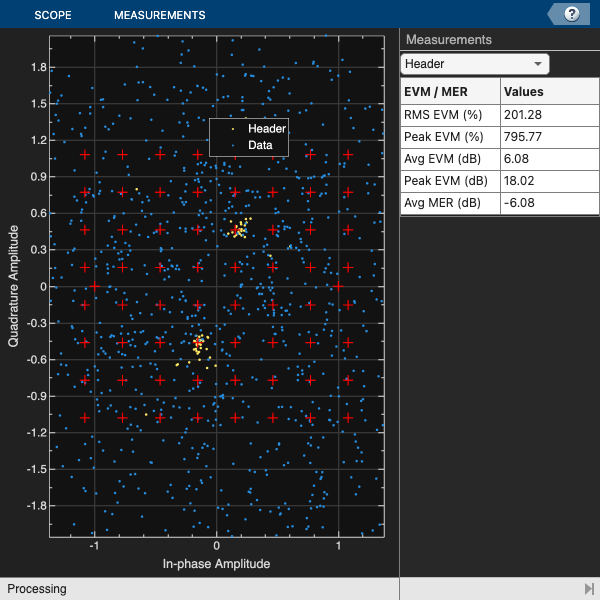

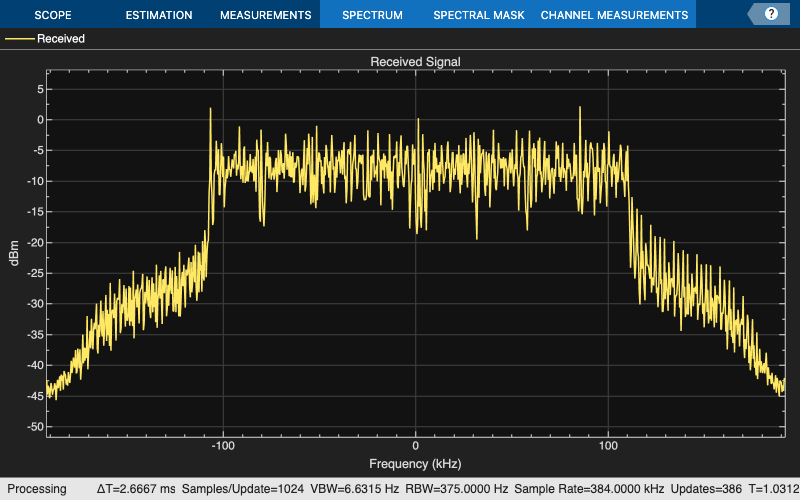

BER = 4.886871e-01 


% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        else
            BER(frameNum) = 0.5;
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
    fprintf('BER = %d \n',BER(frameNum));
end

% Display the mean BER value across all frames
minBER = BER(BER<0.5);
fprintf('Simulation complete!\nAverage BER = %d',mean(minBER))

Simulation complete!
Average BER = 4.832039e-01

### SNR ESTIMATION

%Enable properties of the spectrum analyzer
res = getSpectrumData(spectrumAnalyze);
freq = cell2mat(res.FrequencyVector);
spectrum = cell2mat(res.Spectrum);
fmin = -100e3;
idx = (freq >= fmin) & (freq <= fmin*(-1));
meanPowerdB = mean(spectrum(idx));
idx = find(freq == 129000);
SNRestimation = meanPowerdB - (spectrum(idx));
SNR_vect = repmat(SNRestimation, 1, dataParams.numFrames);
fprintf('SNR estimated: %d\n', SNRestimation);

SNR estimated: 2.061412e+01


release(radio);
% Copyright 2023 The MathWorks, Inc.

## SPECTROGRAM

Plotting dello spettrogramma del segnale ricevuto

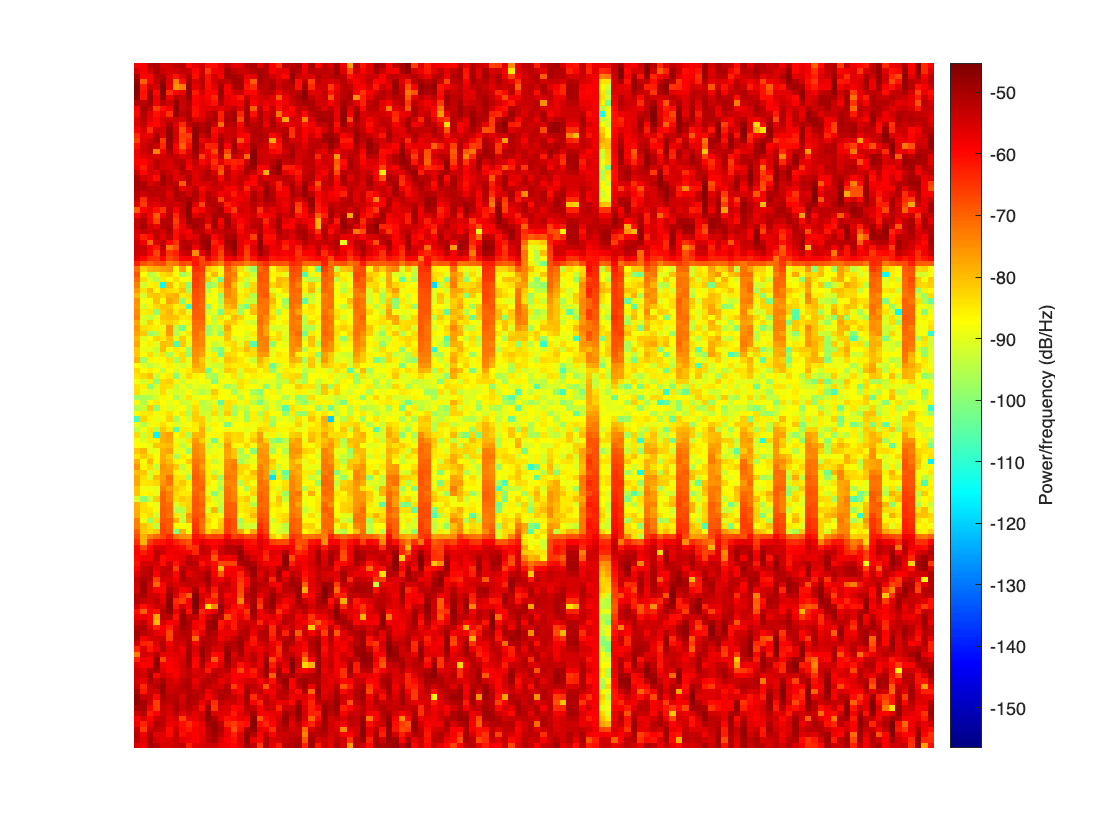

spectrogram(rxWaveform/rms(rxWaveform), 64, 32, 128, sampleRate, 'yaxis');
colormap('jet');
axis("off");